% IDEALISED BUSEMANN BIPLANE RELATIONS

% PART OF THE CODE FOR
% AERO 97009 - FINAL YEAR PROJECT
% BUSEMANN BIPLANES

% THOMAS CROSS
% DECEMBER 2020 - JANUARY 2021

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This code takes in a series of Busemann Biplanes of unit chord but
% varying thicknes (wedge angle) and, for a series of Mach Numbers
% evaluates there performance in terms of a fast and exact methodology for:

%   - Shock angles and how these change as a result of the shocks crossing
%   - Optimal pacing for shock cancellation
%   - Optimal spacing compared to the Choked Area ratio
%   - The attatchment of shockwaves to the surface using 2 parameters

%   - The treatment of expansion waves (2 solutions proposed)
%   - The recovery of Mach Number and Pressure in each region (which leads
%   to drag)

% Useful Check Links  for the functions at code's base
% https://www.engineering.com/calculators/isentropic_flow_relations.htm
% https://www.engineering.com/calculators/oblique_flow_relations.htm

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear 
clc

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, %title, %%legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];


% AIRFOIL VARIABLES
gamma = 1.4

gamma = 1.4000

c = 1 %chord

c = 1


% Mach Numbers to be tested
%M1=[1.7,2] %test values for whcih I have hand calculated results
M1 = [1.3:0.1:3]

M1 =     1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000



% Deflections to be plotted
% theta1=[5,10] %test values for whcih I have hand calculated results
theta1 = [5:1:10] % associated colourmap

theta1 =      5     6     7     8     9    10


cmap = colormap(parula(length(theta1)+1));
t = (c*0.5)*tand(theta1) % associated thicknesses as a %

t =     0.0437    0.0526    0.0614    0.0703    0.0792    0.0882


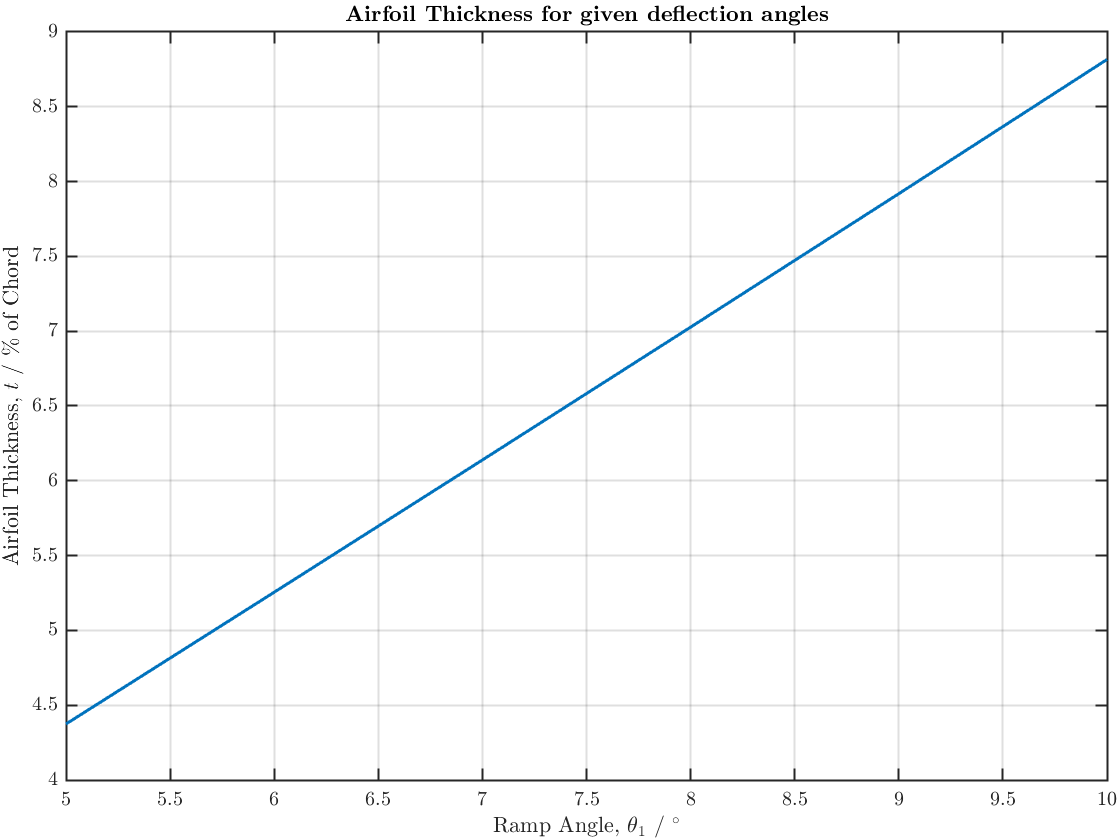

% This relationship is basically linear for small angles

set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex');
set(0,'defaultLegendInterpreter','latex');

%set(0,'defaulttextinterpreter','latex')

figure
plot(theta1,100*t,"LineWidth",1.5)
hold off
xlabel("Ramp Angle, $\theta_{1}$ / $^{\circ}$")
ylabel("Airfoil Thickness, $t$ / \% of Chord")
title("\textbf{Airfoil Thickness for given deflection angles}")
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

%xlim([min(M1),max(M1)])
%ylim([0.75,1.3])


weak = 0 % This specifies we want the weak solution only - strong solutions are off condition

weak = 0


%Setting up the freestream inflow (this is trivial)
Pr1         = ones(length(theta1),length(M1));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Fast Calculation Method

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%preallocation
Beta        = zeros(length(theta1),length(M1));
H_fast      = zeros(length(theta1),length(M1));
h_star_fast = zeros(length(theta1),length(M1));

for j = 1:length(theta1)
    theta = theta1(j);
    for i=1:length(M1)
        machno = M1(i);
        Beta(j,i)=getBeta(machno,theta,gamma,weak);
        
        % Fast Method
        H_fast(j,i) = (c*0.5)*tand(Beta(j,i))+t(j);
        h_star_fast(j,i) = H_fast(j,i)-2*t(j);
    end
    
end

No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle



Beta %Printing Beta for Inspection

Beta =    59.9613   52.7815   47.8893   44.1082   41.0290   38.4440   36.2288   34.3016   32.6050   31.0971   29.7463   28.5279   27.4227   26.4148   25.4917   24.6427   23.8590   23.1333
   63.4584   54.6330   49.3262   45.3438   42.1447   39.4804   37.2093   35.2409   33.5130   31.9809   30.6109   29.3772   28.2596   27.2417   26.3104   25.4548   24.6657   23.9356
       NaN   56.7615   50.8757   46.6470   43.3090   40.5556   38.2229   36.2098   34.4484   32.8905   31.5003   30.2507   29.1203   28.0922   27.1526   26.2903   25.4959   24.7616
       NaN   59.3672   52.5715   48.0302   44.5282   41.6734   39.2722   37.2101   35.4125   33.8269   32.4154   31.1489   30.0053   28.9666   28.0186   27.1496   26.3499   25.6114
       NaN   63.1866   54.4699   49.5111   45.8105   42.8385   40.3601   38.2440   36.4068   34.7915   33.3571   32.0728   30.9151   29.8654   28.9086   28.0327   27.2277   26.4850
       NaN       NaN   56.6787   51.1153   47.1668   44.0567   41.4904   39.3139   37.43


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Full Ideal Solver

%preallocation
x1          = zeros(length(theta1),length(M1));
x2          = zeros(length(theta1),length(M1));
H_exact     = zeros(length(theta1),length(M1));
h_star_exact= zeros(length(theta1),length(M1));
A_ratio     = zeros(length(theta1),length(M1));
M2          = zeros(length(theta1),length(M1));
M3          = zeros(length(theta1),length(M1));
theta2      = zeros(length(theta1),length(M1));
phi1        = zeros(length(theta1),length(M1));
phi2        = zeros(length(theta1),length(M1));
Pr2         = zeros(length(theta1),length(M1));
Pr3         = zeros(length(theta1),length(M1));
beta1       = zeros(length(theta1),length(M1));
beta2       = zeros(length(theta1),length(M1));

for j = 1:length(theta1)
    theta = theta1(j);
    for i=1:length(M1)
        machno = M1(i);
[x1(j,i),x2(j,i),H_exact(j,i),h_star_exact(j,i),A_ratio(j,i),beta1(j,i),beta2(j,i),M2(j,i),M3(j,i),theta2(j,i),phi1(j,i),phi2(j,i),Pr2(j,i),Pr3(j,i)] = IdealSpacing(machno,theta,c,gamma);
    end
end

No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle



% Net Pressure Rise
TotalPr = Pr3.*Pr2.*Pr1;

## Plotting Shock Angles

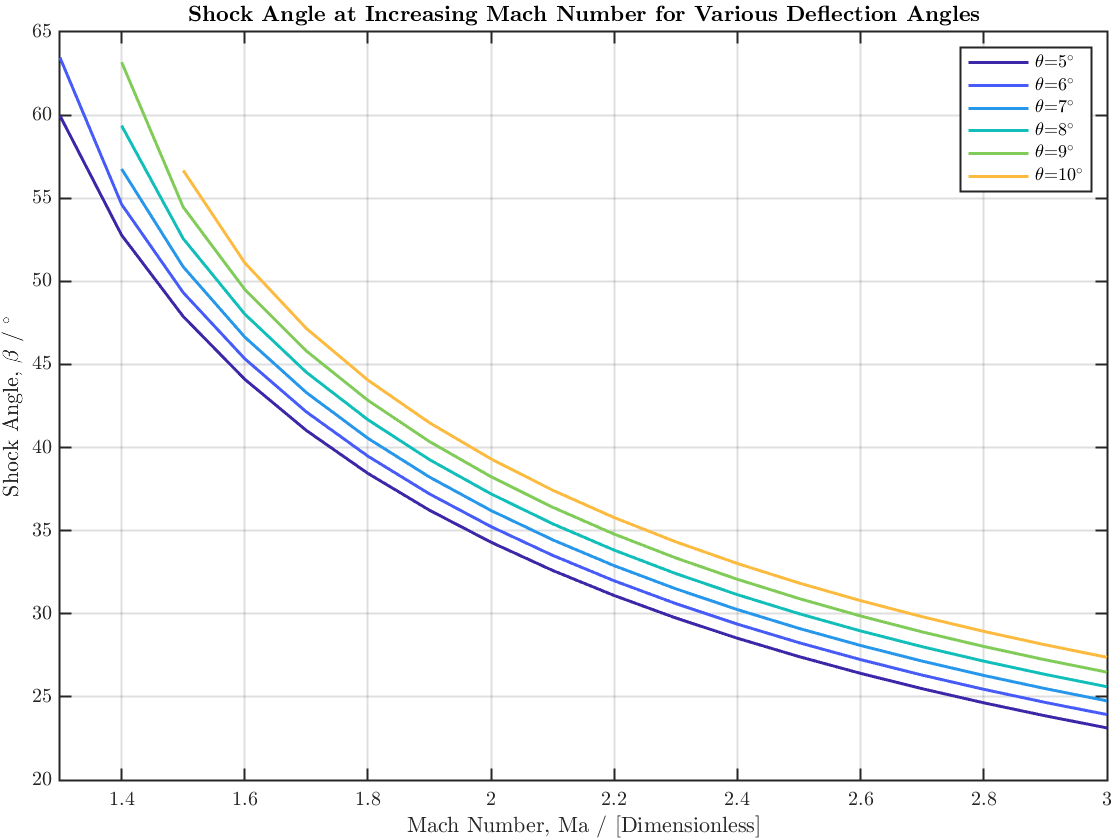

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
for line = 1:length(theta1)
plot(M1,Beta(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Shock Angle, $\beta$ / $^{\circ}$")
title("\textbf{Shock Angle at Increasing Mach Number for Various Deflection Angles}")
grid on
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Plotting Mach Numbers

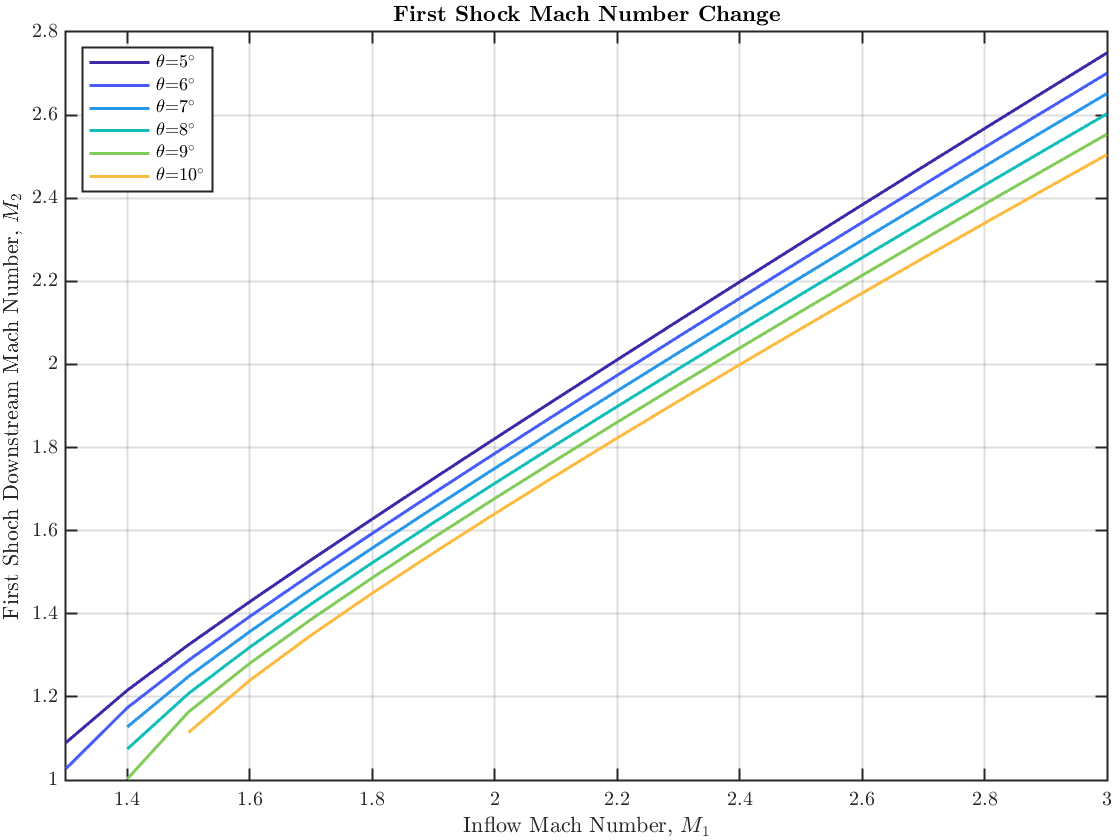


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
for line = 1:length(theta1)
plot(M1,M2(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,'location','northwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("First Shoch Downstream Mach Number, $M_{2}$")
title("\textbf{First Shock Mach Number Change}")
grid on
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

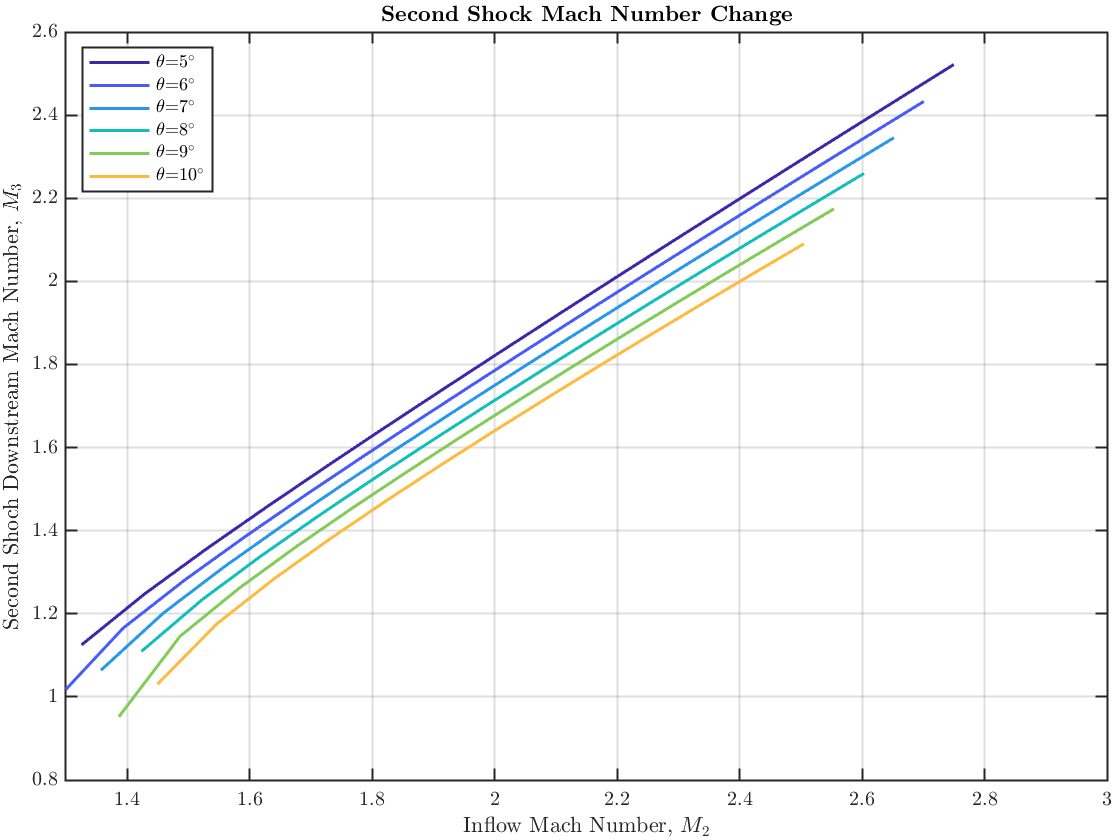


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
for line = 1:length(theta1)
plot(M2(line,:),M3(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,'location','northwest')
xlabel("Inflow Mach Number, $M_{2}$")
ylabel("Second Shoch Downstream Mach Number, $M_{3}$")
title("\textbf{Second Shock Mach Number Change}")
grid on
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

M3

M3 =        NaN       NaN    1.1250    1.2484    1.3562    1.4572    1.5543    1.6487    1.7411    1.8319    1.9214    2.0098    2.0972    2.1837    2.2693    2.3541    2.4382    2.5216
       NaN       NaN    0.9993    1.1656    1.2820    1.3864    1.4846    1.5791    1.6709    1.7607    1.8487    1.9354    2.0208    2.1051    2.1884    2.2708    2.3522    2.4329
       NaN       NaN       NaN    1.0641    1.2020    1.3127    1.4135    1.5088    1.6004    1.6894    1.7763    1.8615    1.9451    2.0275    2.1086    2.1886    2.2676    2.3456
       NaN       NaN       NaN       NaN    1.1094    1.2341    1.3398    1.4370    1.5292    1.6179    1.7039    1.7878    1.8699    1.9504    2.0296    2.1074    2.1840    2.2595
       NaN       NaN       NaN       NaN    0.9520    1.1460    1.2618    1.3629    1.4566    1.5456    1.6312    1.7141    1.7949    1.8738    1.9511    2.0269    2.1013    2.1745
       NaN       NaN       NaN       NaN       NaN    1.0306    1.1759    1.2849    1.3817

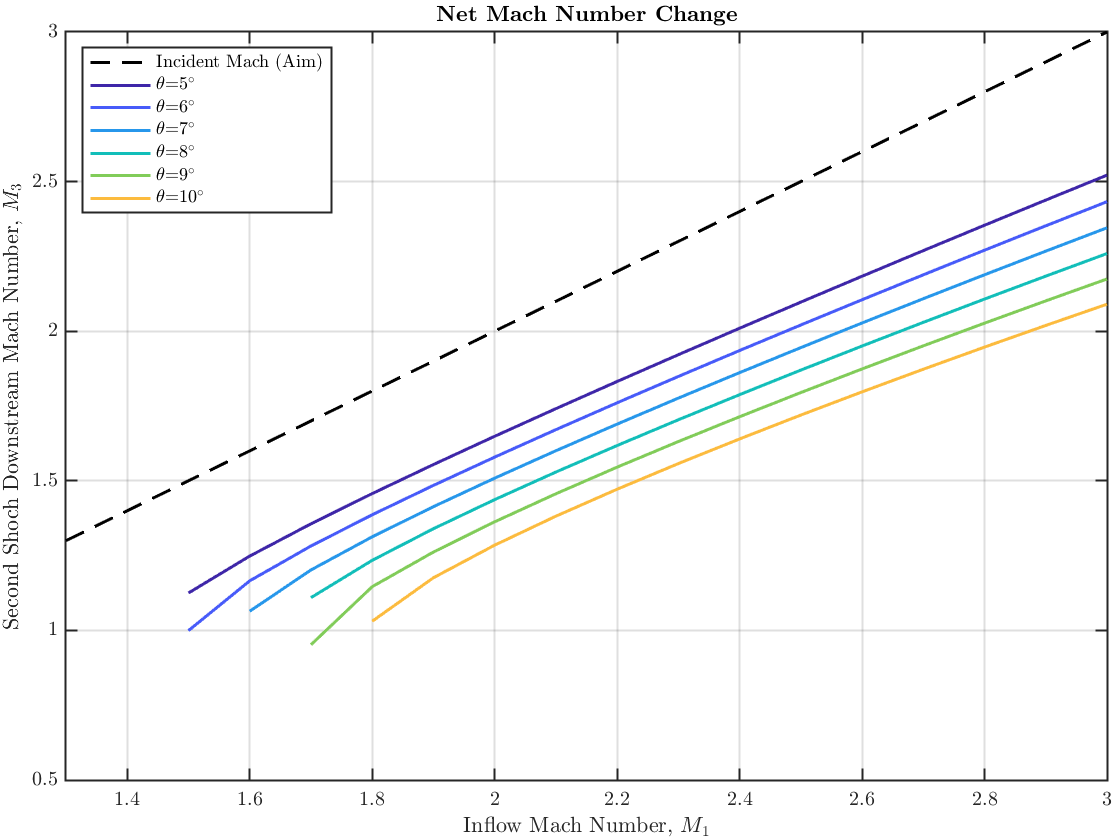


figure
plot(M1,M1,'Color','k',"LineWidth",1.5,'LineStyle','--')
hold on
for line = 1:length(theta1)
plot(M1,M3(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(['Incident Mach (Aim)',legendCelltheta],'location','northwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Second Shoch Downstream Mach Number, $M_{3}$")
title("\textbf{Net Mach Number Change}")
grid on
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Plotting Spacings

anglechange=phi2./beta1;

%cmap = colormap(summer(length(theta1)));
%cmap = colormap(winter(length(theta1)));
%cmap = colormap(spring(length(theta1)));
%cmap = colormap(autumn(length(theta1)));

%cmap = colormap(turbo(length(theta1))); %dark at both ends
%cmap = colormap(hsv(length(theta1))); %rainbow
%cmap = colormap(hot(length(theta1))); %brown red yellow
%cmap = colormap(cool(length(theta1))); %pink purple blue

%cmap = colormap(gray(length(theta1))); %grayscale linear
%cmap = colormap(bone(length(theta1)));
%cmap = colormap(copper(length(theta1)));
%cmap = colormap(pink(length(theta1)));

%cmap = colormap(jet(length(theta1))); %rainbow
%cmap = colormap(lines(length(theta1))); %not the worst?
%cmap = colormap(colorcube(length(theta1)));

%custom ones
%cmap = colormap(viridis(length(theta1))); % v nice
%cmap = colormap(viridis(length(theta1)+1));

cmap = colormap(parula(length(theta1)+1));

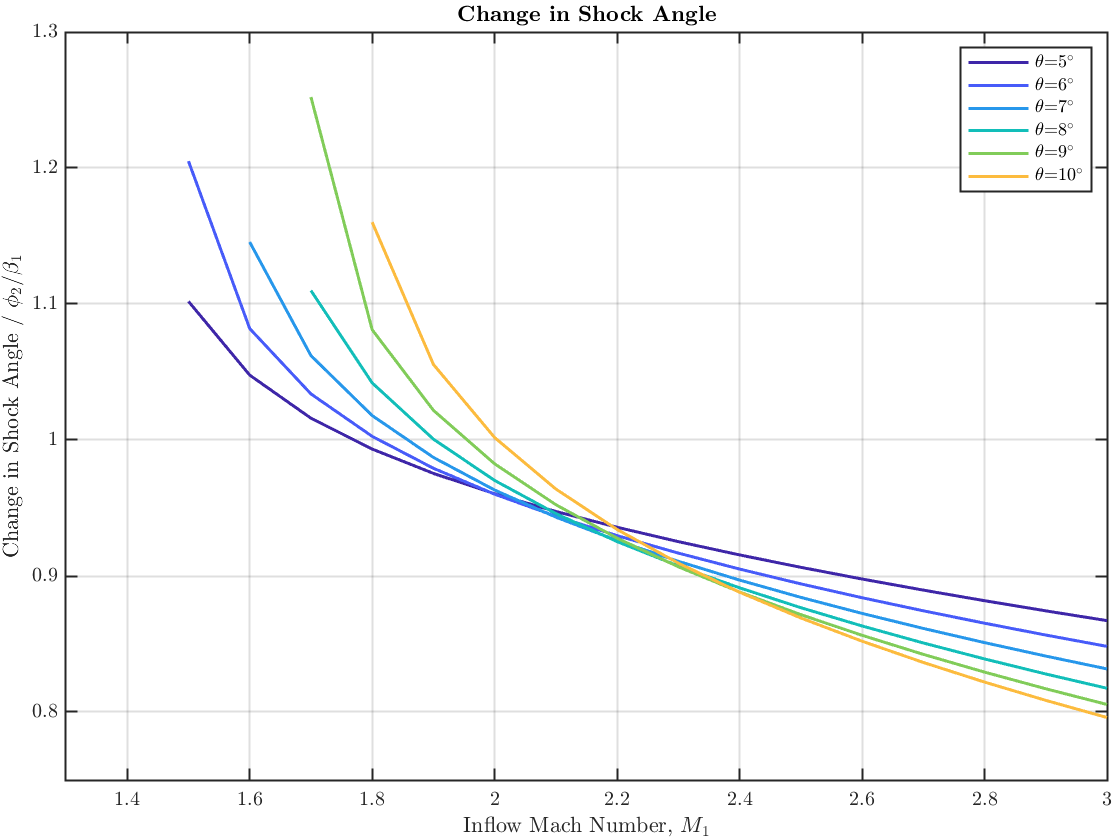

%cmap = colormap(parula(length(theta1)+1)); %1 extra is good

%manual define
%colours = [linspace(0,1,length(theta1))', zeros(length(theta1),2)] %black thru red
%colours = [linspace(0, 256, length(theta1))', linspace(0, 256, length(theta1))', zeros(length(theta1), 1)]./256 %black thru yellow
%colours = [linspace(0, 256, length(theta1))', zeros(length(theta1), 1), flip(linspace(0, 256, length(theta1))')]./256 %red, purople, blue
%colours = hsv(length(theta1))

% Hue - Value from 0 to 1 that corresponds to the color's position on a color wheel. As hue increases from 0 to 1, the color transitions from red to orange, yellow, green, cyan, blue, magenta, and finally back to red.
% Saturation - Amount of hue or departure from neutral. 0 indicates a neutral shade, whereas 1 indicates maximum saturation.
% Value	- Maximum value among the red, green, and blue components of a specific color.

%Hue, Saturation, Value
%hsv = [0.6*ones(length(theta1),1), linspace(1, 0, length(theta1))', ones(length(theta1),1)]
%hsv1 = [linspace(0.65, 1,length(theta1))',  0.6+0.4.*cos(pi*cosspace(0.9, 1, length(theta1), 1)').^2, ones(length(theta1), 1)-0.3.*(cos(pi*cosspace(0.2, 1, length(theta1), 1)').^2-ones(length(theta1),1))-0.3.*ones(length(theta1), 1)]
%colours = hsv2rgb(hsv1);

%cmap = colormap(redblue(length(theta1)))
%cmap = colormap(bluewhitered(length([-5,-3, -1, 0, 2, 5])))
   % length(theta1)
 
    %figure
%imagesc(theta1-median(theta1));
%cmap=colormap(bluewhitered(length(theta1))), colorbar
%hold off
    %cmap = colormap(bluewhitered(theta1))

%cmap = colormap(colours);
%colorbar; %optional to help out

figure
for line = 1:length(theta1)
plot(M1,anglechange(line,:),'-','Color',cmap(line,:),"LineWidth",1.5)
hold on
end
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Change in Shock Angle / $\phi_{2}/\beta_{1}$")
title("\textbf{Change in Shock Angle}")
legend(legendCelltheta)
xlim([min(M1),max(M1)])
ylim([0.75,1.3])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

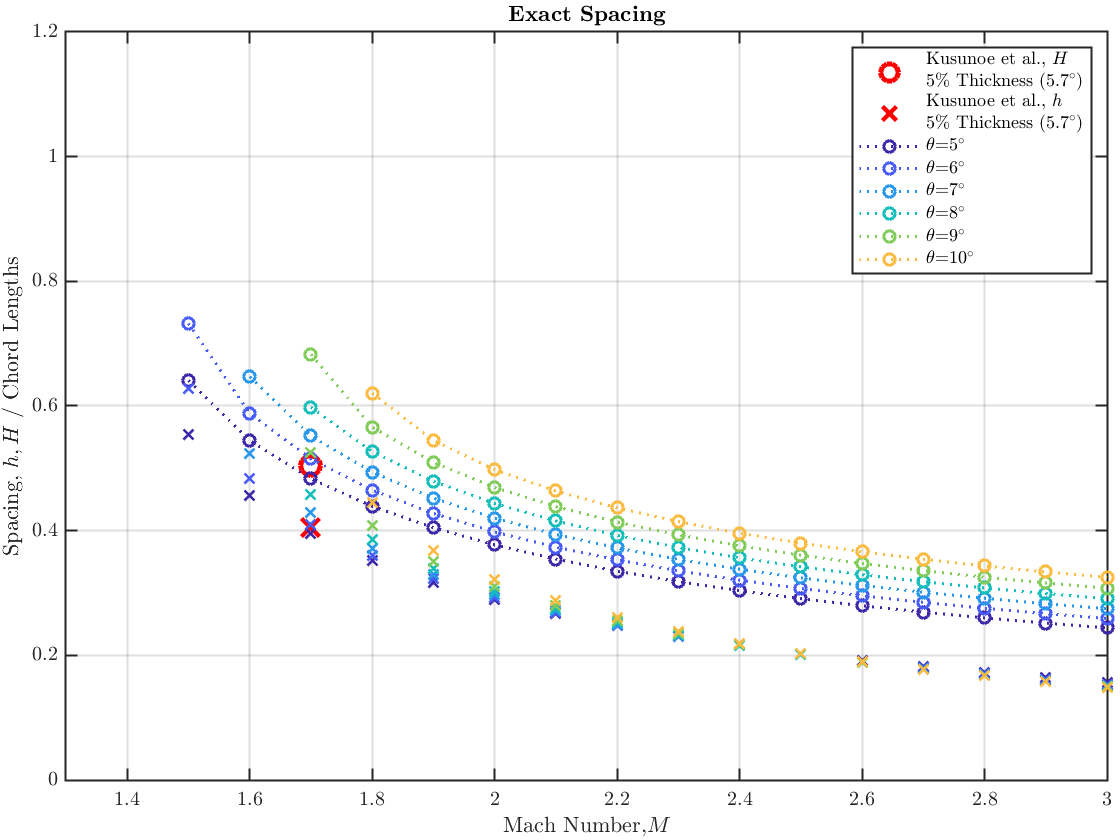


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Kusunose et al. (2011)
Jpn_Mach = 1.7;
Jpn_t = 0.05;
Jpn_H = 0.505;%Jpn_H = 0.5;
Jpn_h = Jpn_H-(2*Jpn_t);
Jpn_Ar = Jpn_h/Jpn_H;

figure
%subplot(2,2,1)
plot(Jpn_Mach, Jpn_H,'or',"LineWidth",2.5,"MarkerSize",10)
hold on
plot(Jpn_Mach, Jpn_h,'xr',"LineWidth",2.5,"MarkerSize",10)
for line = 1:length(theta1)
plot(M1,H_exact(line,:),'o:','Color',cmap(line,:),"LineWidth",1.5)
hold on
end
xlabel("Mach Number,$M$")
ylabel("Spacing, $h,H$ / Chord Lengths")
for line = 1:length(theta1)
plot(M1,h_star_exact(line,:),'x','Color',cmap(line,:),"LineWidth",1.5)
hold on
end
title("\textbf{Exact Spacing}")
legend([{['Kusunoe et al., $H$' newline '5\% Thickness (5.7$^{\circ}$)']},{['Kusunoe et al., $h$' newline '5\% Thickness (5.7$^{\circ}$)']},legendCelltheta],'location','northeast')
grid on
box off
xlim([min(M1),max(M1)])
ylim([0.0,1.2])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

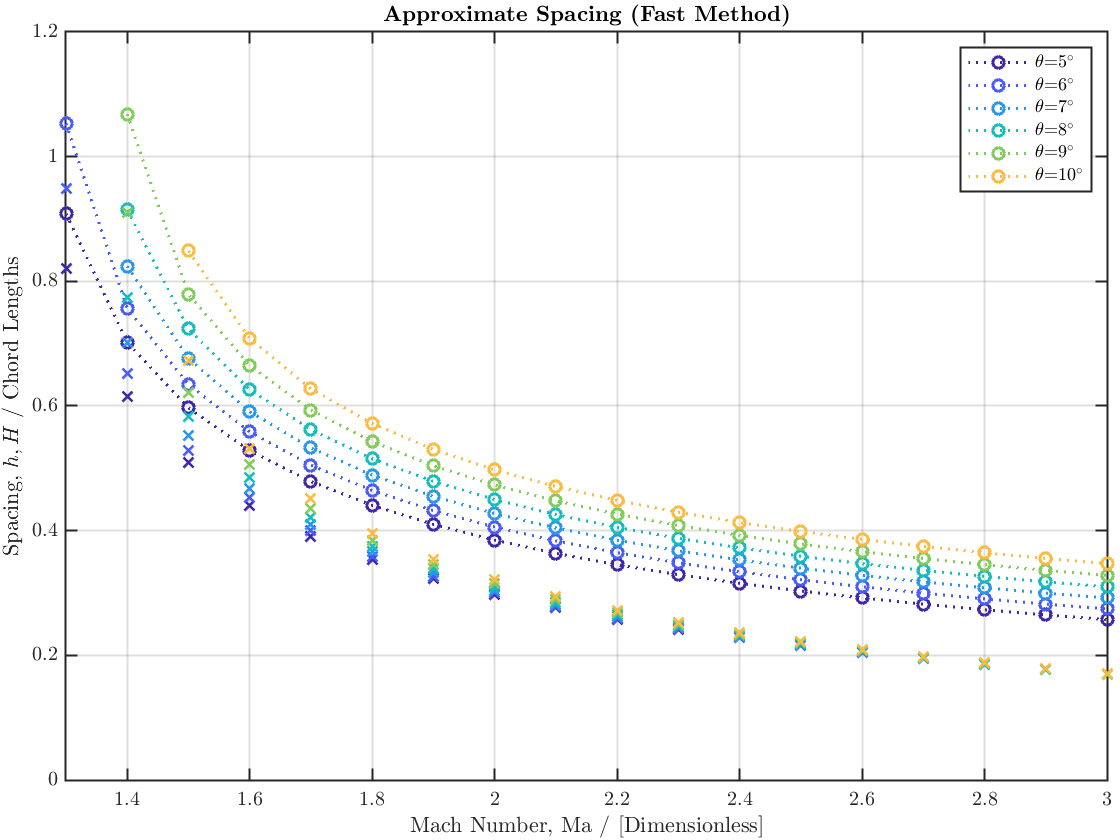


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
%subplot(2,2,2)
for line = 1:length(theta1)
plot(M1,H_fast(line,:),'o:','Color',cmap(line,:),"LineWidth",1.5)
hold on
end
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Spacing, $h, H$ / Chord Lengths")
for line = 1:length(theta1)
plot(M1,h_star_fast(line,:),'x','Color',cmap(line,:),"LineWidth",1.5)
hold on
end
title("\textbf{Approximate Spacing (Fast Method)}")
legend(legendCelltheta)
xlim([min(M1),max(M1)])
ylim([0.0,1.2])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Choking and Area Ratio

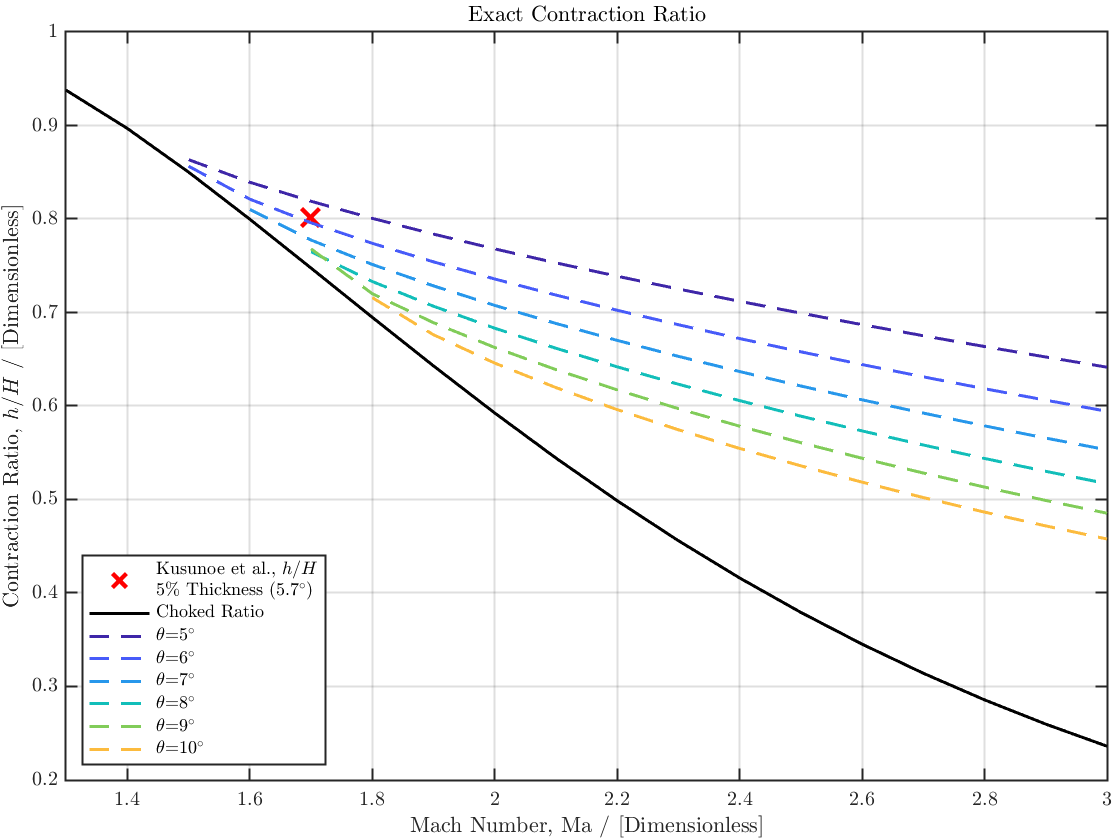

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Chocked_Area=zeros(1,length(M1));
for n=1:length(M1)
    Chocked_Area(n) = 1./Area_Ratio(M1(n),gamma);
end

Area_Ratio_Fast = h_star_fast./H_fast;

figure
%subplot(2,2,1)
plot(Jpn_Mach, Jpn_Ar,'xr',"LineWidth",2.5,"MarkerSize",10)
hold on
plot(M1,Chocked_Area,'k',"LineWidth",1.5)
hold on
for line = 1:length(theta1)
    plot(M1,A_ratio(line,:),'--','Color',cmap(line,:),"LineWidth",1.5)
    hold on
end
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Contraction Ratio, $h/H$ / [Dimensionless]")
title("Exact Contraction Ratio")
legend([{['Kusunoe et al., $h/H$' newline '5\% Thickness (5.7$^{\circ}$)']},"Choked Ratio",legendCelltheta],'Location','southwest')
xlim([min(M1),max(M1)])
ylim([0.2,1.0])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

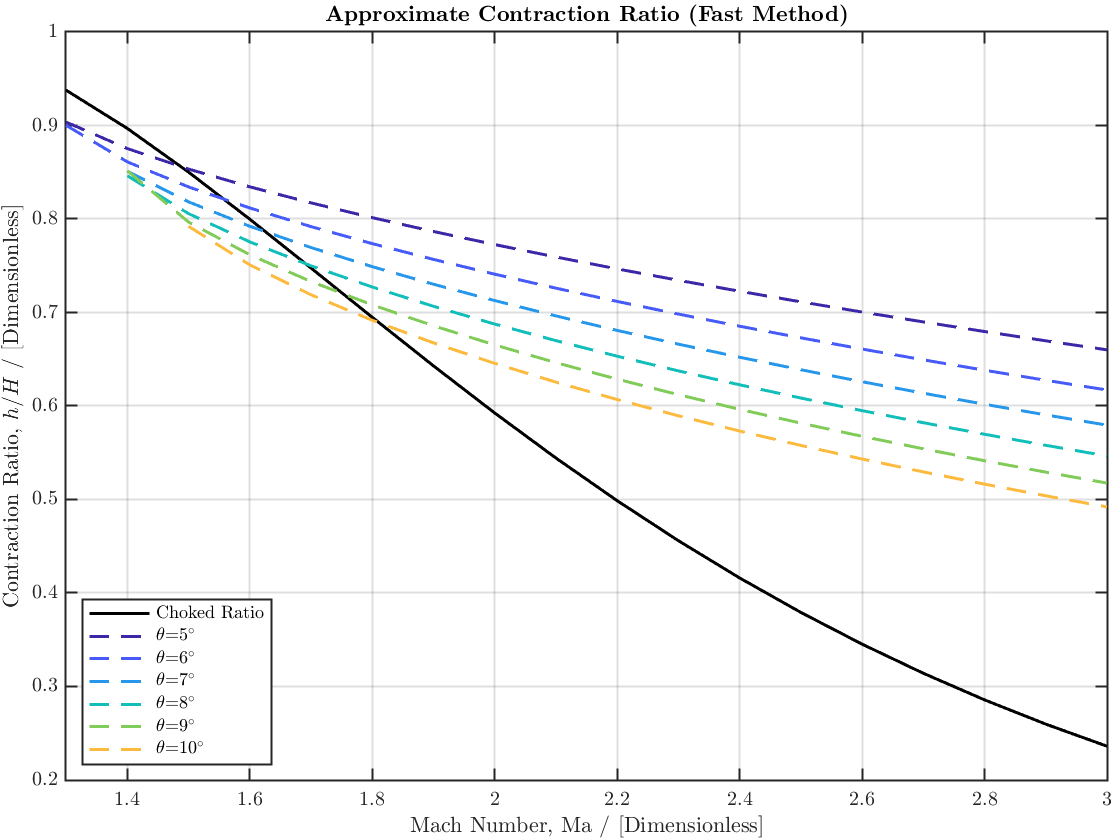


%subplot(2,2,2)
figure
plot(M1,Chocked_Area,'k',"LineWidth",1.5)
hold on
for line = 1:length(theta1)
    plot(M1,Area_Ratio_Fast(line,:),'--','Color',cmap(line,:),"LineWidth",1.5)
    hold on
end
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Contraction Ratio, $h/H$ / [Dimensionless]")
title("\textbf{Approximate Contraction Ratio (Fast Method)}")
legend(["Choked Ratio",legendCelltheta],'Location','southwest')
xlim([min(M1),max(M1)])
ylim([0.2,1.0])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Pressure Rises across each Shock

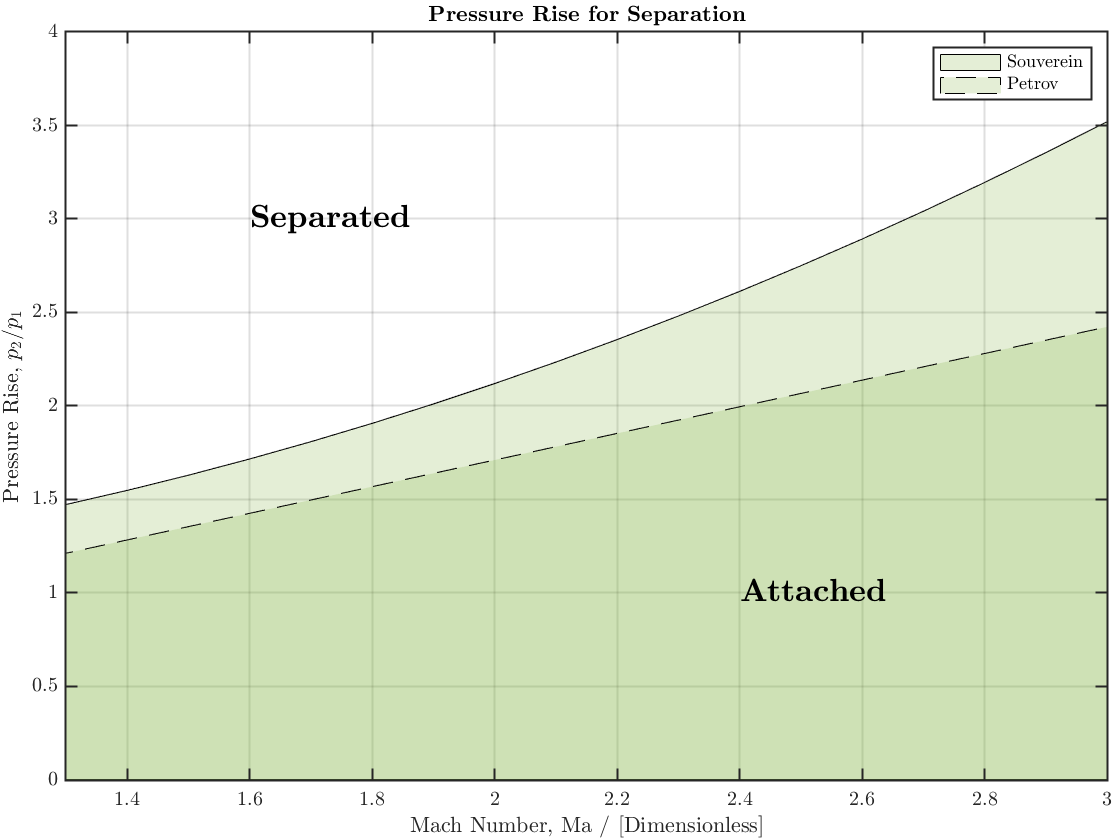

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% SEPARATION P-RISE CRITERION

% Separation Pressure Rise
% Petrov
Pr_sep_Petrov = 0.287+0.712*M1;
% Souverein
k = 2.5;
Pr_sep_Souverein = 1+(gamma/(2*k))*M1.^2;

% PLOTTING

figure
area(M1,Pr_sep_Souverein,'LineStyle','-') 
hold on
area(M1,Pr_sep_Petrov,'LineStyle','--') 
hold on
newcolors = [0.4660 0.6740 0.1880];
colororder(newcolors)
%plot(M1,Pr_sep_Souverein,'k--',"LineWidth",1.5)
hold on
%plot(M1,Pr_sep_Petrov,'k-',"LineWidth",1.5)
legend("Souverein","Petrov","location","northeast")
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, $p_{2}/p_{1}$")
title("\textbf{Pressure Rise for Separation}")
grid on
xlim([min(M1),max(M1)])
txt = {'\textbf{Attached}'};
text(2.4,1,txt,'FontSize',16)
txt2 = {'\textbf{Separated}'};
text(1.6,3,txt2,'FontSize',16)
box off
alpha(.2)
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

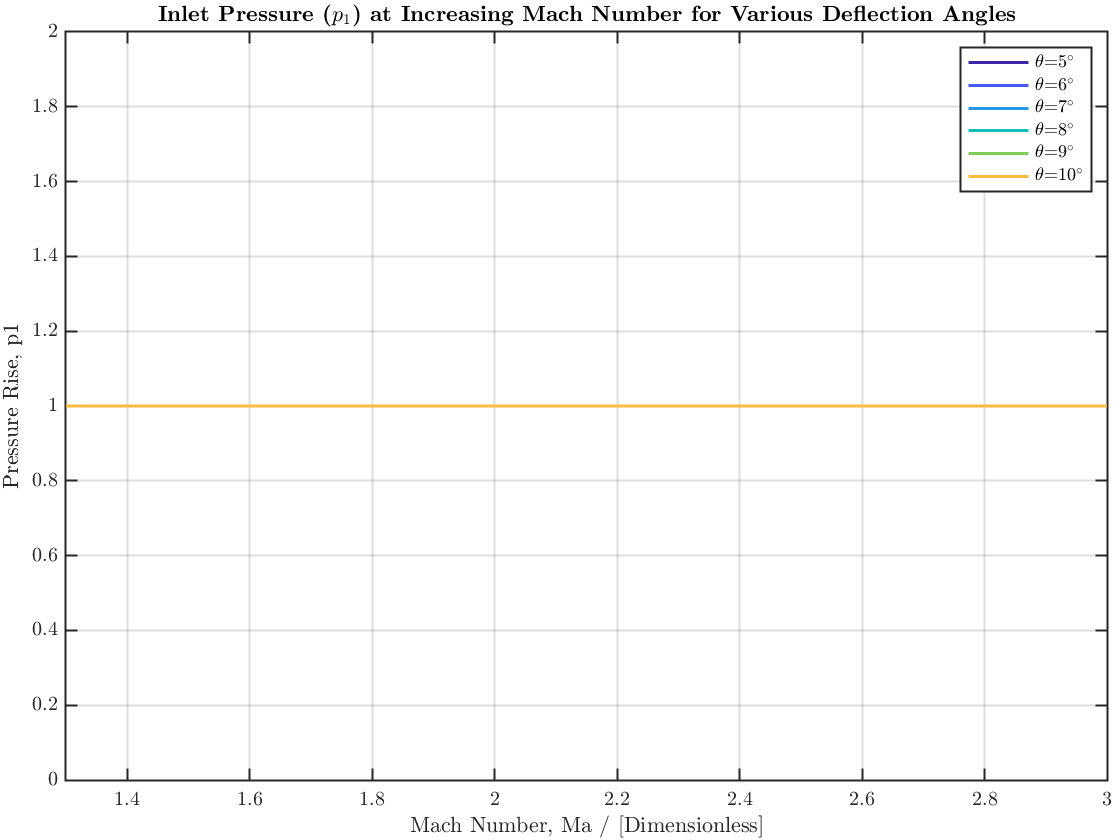


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% EXPERIENCED P-RISES

figure
for line = 1:length(theta1)
plot(M1,Pr1(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, p1")
title("\textbf{Inlet Pressure ($p_{1}$) at Increasing Mach Number for Various Deflection Angles}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

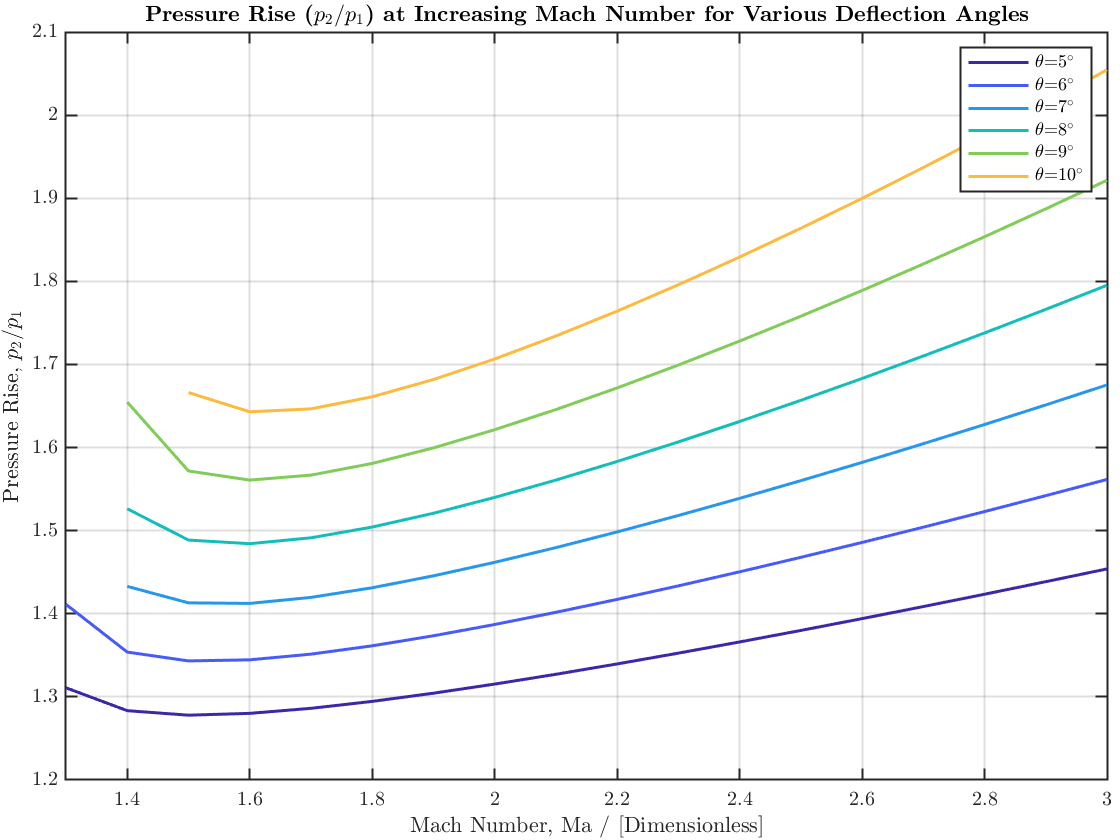


figure
for line = 1:length(theta1)
plot(M1,Pr2(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, $p_{2}/p_{1}$")
title("\textbf{Pressure Rise ($p_{2}/p_{1}$) at Increasing Mach Number for Various Deflection Angles}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

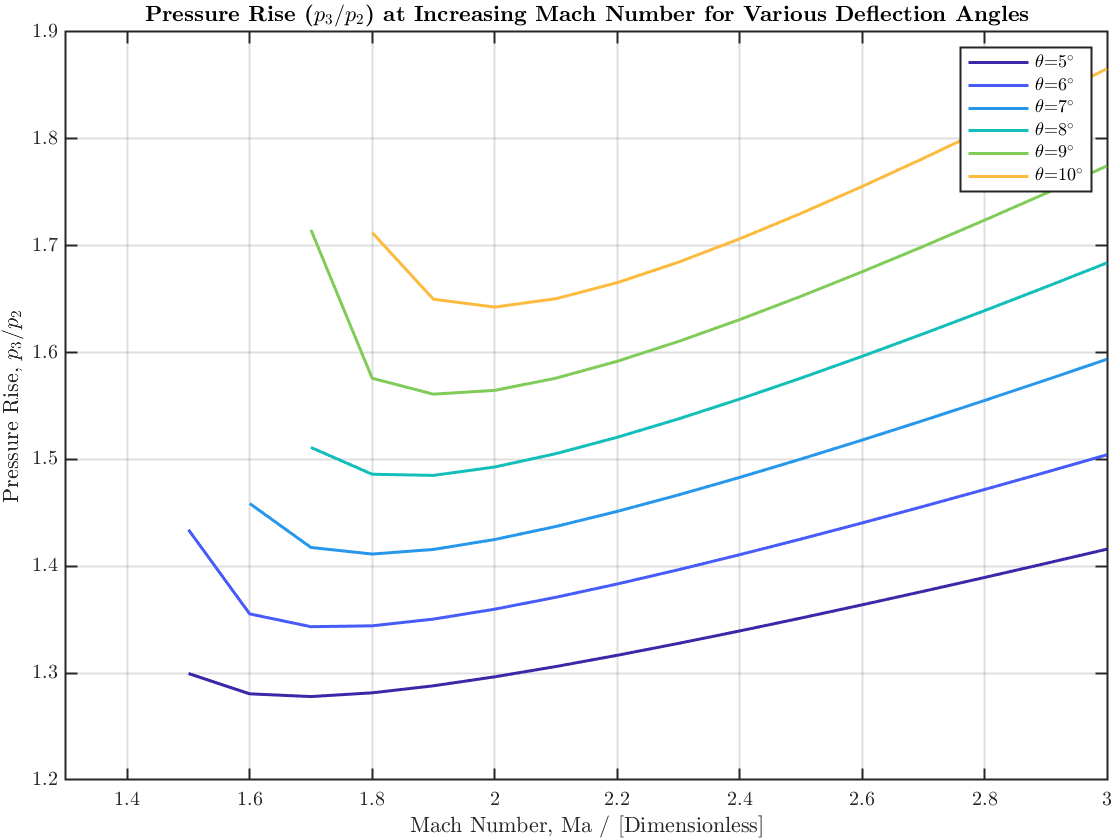


figure
for line = 1:length(theta1)
plot(M1,Pr3(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,"location","northeast")
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, $p_{3}/p_{2}$")
title("\textbf{Pressure Rise ($p_{3}/p_{2}$) at Increasing Mach Number for Various Deflection Angles}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

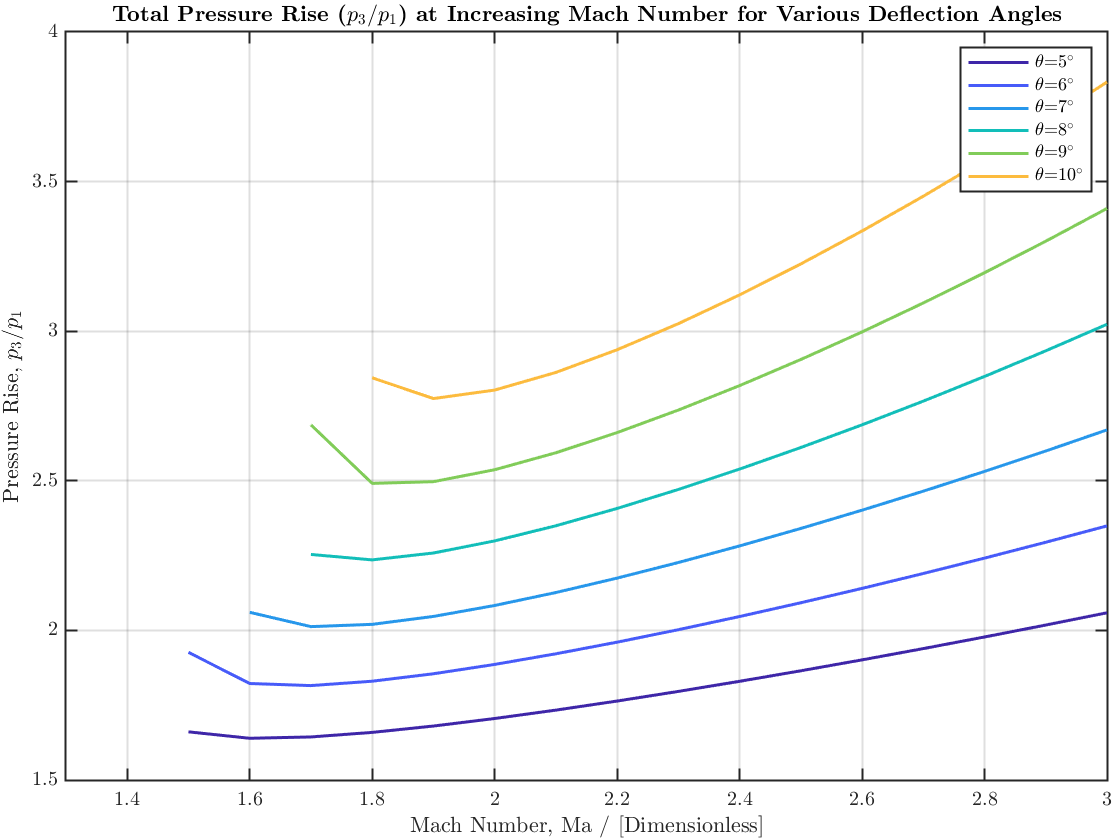


figure
for line = 1:length(theta1)
plot(M1,TotalPr(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,"location","northeast")
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, $p_{3}/p_{1}$")
title("\textbf{Total Pressure Rise ($p_{3}/p_{1}$) at Increasing Mach Number for Various Deflection Angles}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

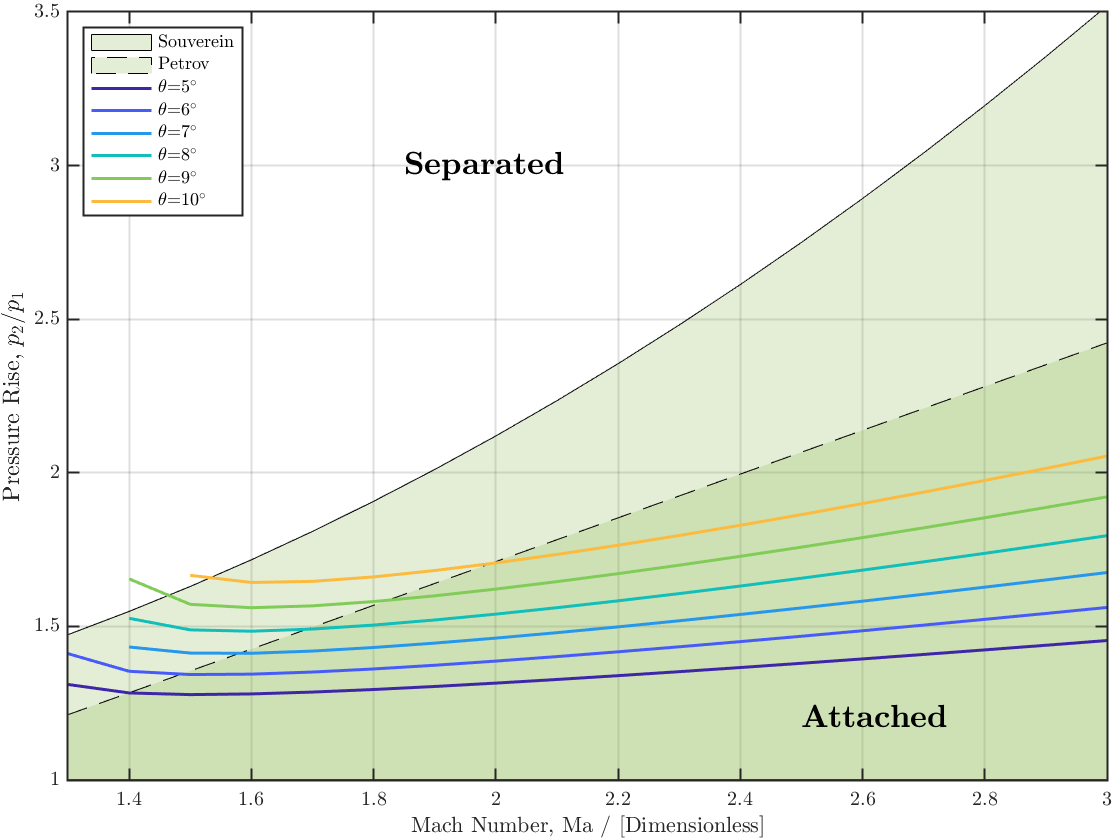

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  

figure
%subplot(2,2,1)
area(M1,Pr_sep_Souverein,'LineStyle','-') 
hold on
area(M1,Pr_sep_Petrov,'LineStyle','--') 
hold on
newcolors = [0.4660 0.6740 0.1880];
colororder(newcolors)
alpha(.2)

%plot(M1,Pr_sep_Souverein,'k--',"LineWidth",1.5)
hold on
%plot(M1,Pr_sep_Petrov,'k-',"LineWidth",1.5)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Pressure Rise, $p_{2}/p_{1}$",'FontSize',lsize)

for line = 1:length(theta1)
plot(M1,Pr2(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(["Souverein","Petrov",legendCelltheta],"location","northwest")
%title("\textbf{Total Pressure Rise ($p_{2}/p_{1}$) Contrasted with Separation Rise}")
txt = {'\textbf{Attached}'};
text(2.5,1.2,txt,'FontSize',16)
txt2 = {'\textbf{Separated}'};
text(1.85,3,txt2,'FontSize',16)
ylim([1,3.5])
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

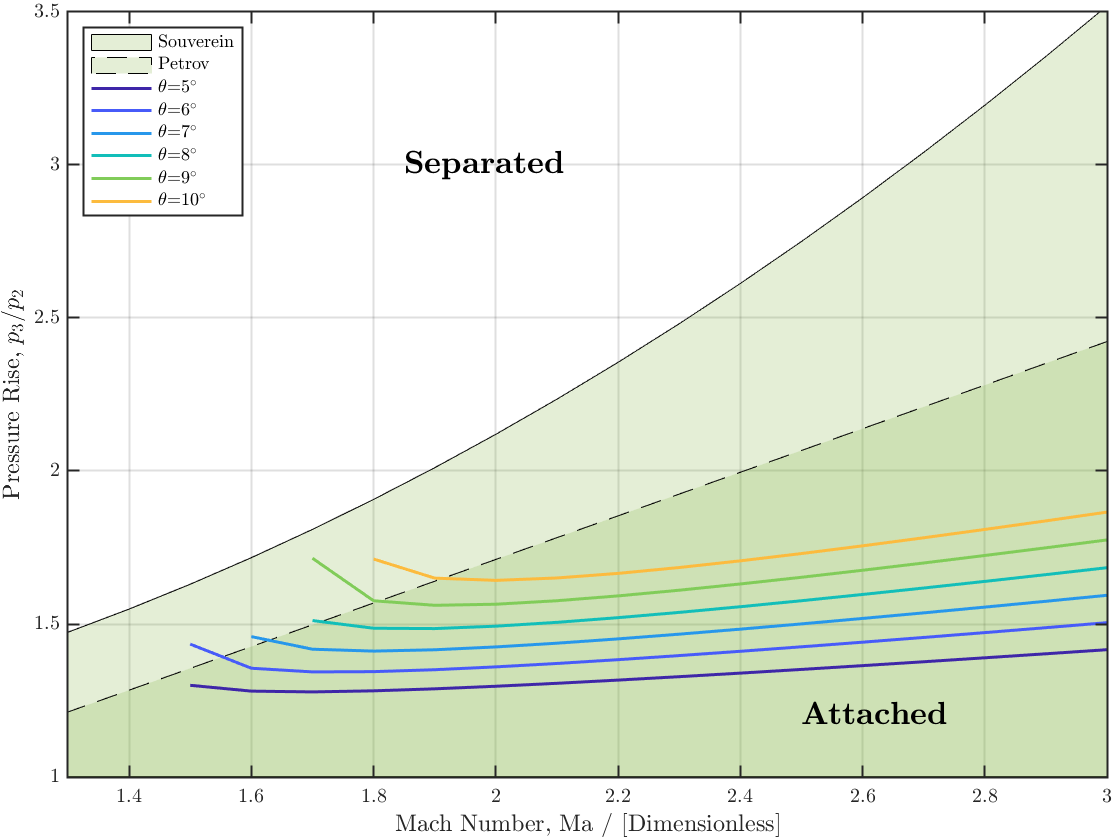


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  

figure
%subplot(2,2,2)
area(M1,Pr_sep_Souverein,'LineStyle','-') 
hold on
area(M1,Pr_sep_Petrov,'LineStyle','--') 
hold on
newcolors = [0.4660 0.6740 0.1880];
colororder(newcolors)
alpha(.2)

%plot(M1,Pr_sep_Souverein,'k--',"LineWidth",1.5)
hold on
%plot(M1,Pr_sep_Petrov,'k-',"LineWidth",1.5)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Pressure Rise, $p_{3}/p_{2}$",'FontSize',lsize)

for line = 1:length(theta1)
plot(M1,Pr3(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(["Souverein","Petrov",legendCelltheta],"location","northwest")
%title("\textbf{Total Pressure Rise ($p_{3}/p_{2}$) Contrasted with Separation Rise}")
txt = {'\textbf{Attached}'};
text(2.5,1.2,txt,'FontSize',16)
txt2 = {'\textbf{Separated}'};
text(1.85,3,txt2,'FontSize',16)
ylim([1,3.5])
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Initial Expansion

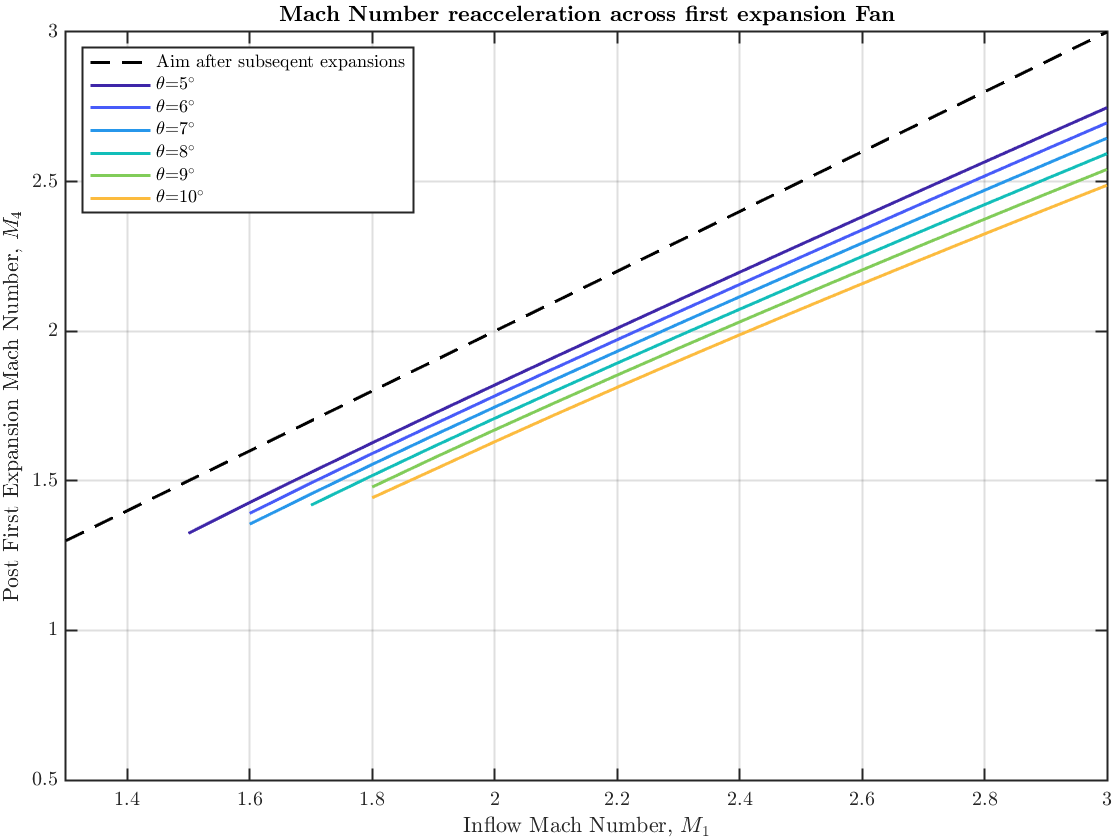

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Flow field at the central point: M3
% Relative direction = 0deg, turn = theta1

M3(M3 < 1) = NaN; %Gets rid of the subsonic central regioned pts

mu1 = asind(1./M3);
phi_startExp = mu1;

v_M4 = transpose(theta1)+PrandtlMeyer(M3,gamma);
M4 = InvPrandtlMeyer(v_M4);

mu2 = asind(1./M4);
phi_endExp = mu2-transpose(theta1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
plot(M1,M1,'Color','k',"LineWidth",1.5,'LineStyle','--')
hold on
for line = 1:length(theta1)
plot(M1,M4(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(['Aim after subseqent expansions',legendCelltheta],'location','northwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Post First Expansion Mach Number, $M_{4}$")
title("\textbf{Mach Number reacceleration across first expansion Fan}")
ylim([0.5,3])
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Fast Method of Expansions

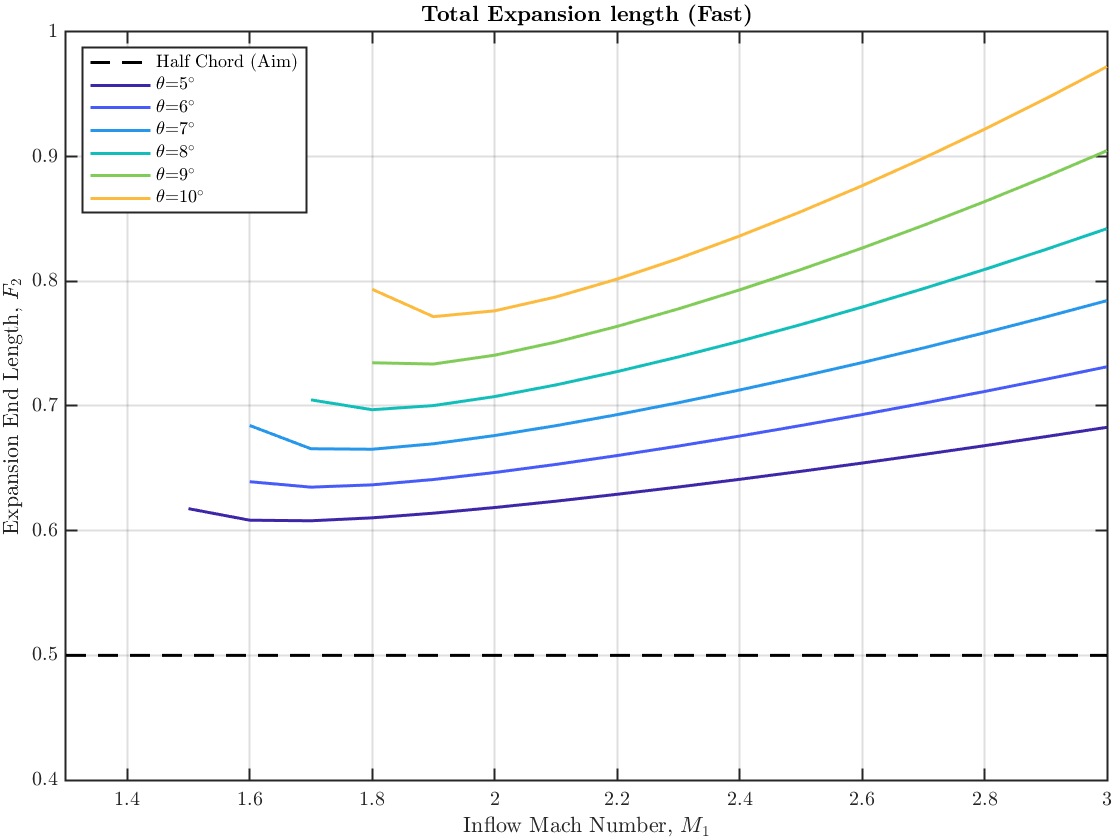

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This essentially breaks the expansions down into three length
% x3 = distance covered to meet at the centerline 
% F1, distance travelled for expansion head wave to hit other side
% F2, distnace travelled for rtail wave to hit other side
% if all works out then this distance (F2) shoucl be
% half a chord length.

% THIS FAST METHOD DOES NOT ACCOUNT FOR EXPANSION-EXPANSION INTERACTION

% x3
x_3 = (h_star_exact/2)./tand(phi_startExp);

% F2
F2 = (H_exact-transpose(t)).*tand(90-phi_endExp);
Overexpansion_length = F2-0.5;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
plot([min(M1),max(M1)],[0.5,0.5],'Color','k',"LineWidth",1.5,'LineStyle','--')
hold on

for line = 1:length(theta1)
plot(M1,F2(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(['Half Chord (Aim)',legendCelltheta],'location','northwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Expansion End Length, $F_{2}$")
title("\textbf{Total Expansion length (Fast)}")
xlim([min(M1),max(M1)])
ylim([0.4,1])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% F1
F1 = (h_star_exact.*tand(90-phi_startExp)) ./ (1-(2.*transpose(t)).*tand(90-phi_startExp));

## AREA RATIO METHOD

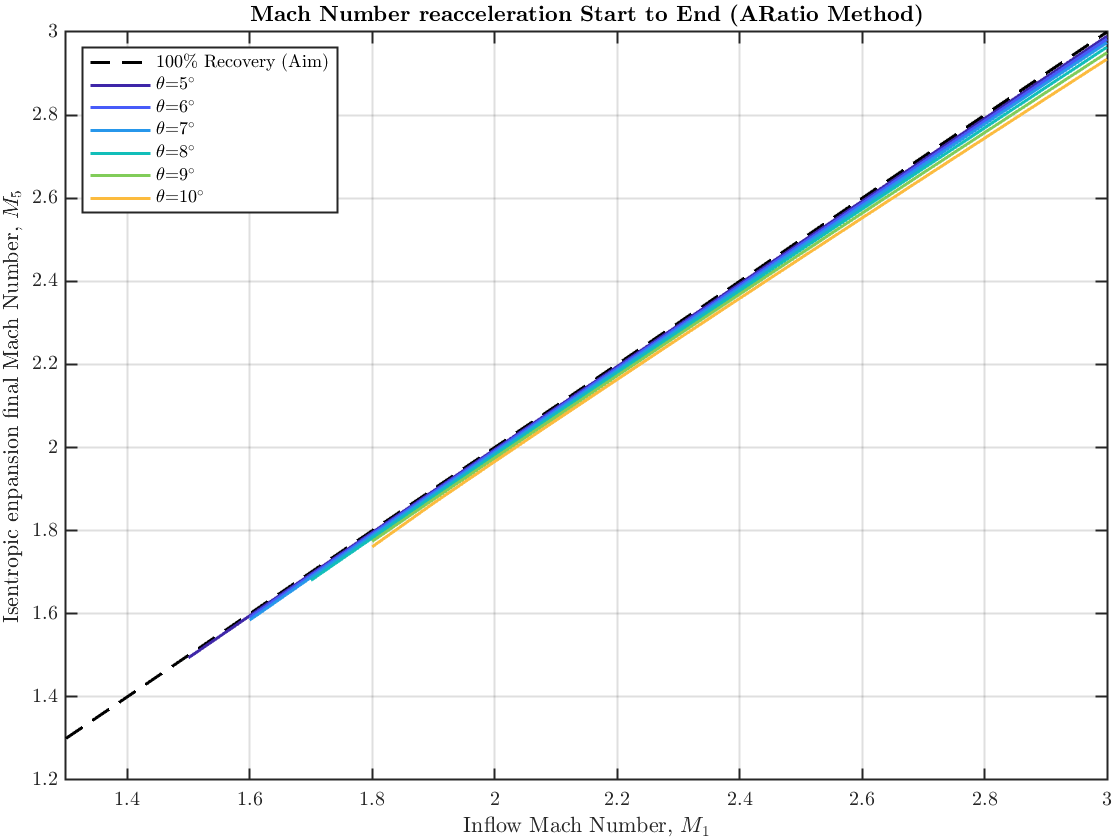

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% So here we have an expansion from A1 to A2 i.e. h to H
% This equates to a mach increase (or should) from M3 to M5
% We use a supersonic (chocked) reference condion: (A2/A*) = (A2/A1)(A1/A*)

%(A2/A1)
Overall_Exp_Ratio = H_exact./h_star_exact;

%(A1/A*)
Start_Mach_ARatio = Area_Ratio(M3,gamma);

% The calculation
Final_Mach_ARatio = Overall_Exp_Ratio.*Start_Mach_ARatio;

M5_AR = zeros(size(M3));

for i = 1:length(theta1)
    for j = 1:length(M1)
M5_AR(i,j) = Inv_Area_Ratio(Final_Mach_ARatio(i,j),gamma);
    end 
end

Recovery_MachRatio_AR = 100*(M5_AR./M1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
plot(M1,M1,'Color','k',"LineWidth",1.5,'LineStyle','--')
hold on
for line = 1:length(theta1)
plot(M1,M5_AR(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(['100\% Recovery (Aim)',legendCelltheta],'location','northwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Isentropic enpansion final Mach Number, $M_{5}$")
title("\textbf{Mach Number reacceleration Start to End (ARatio Method)}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

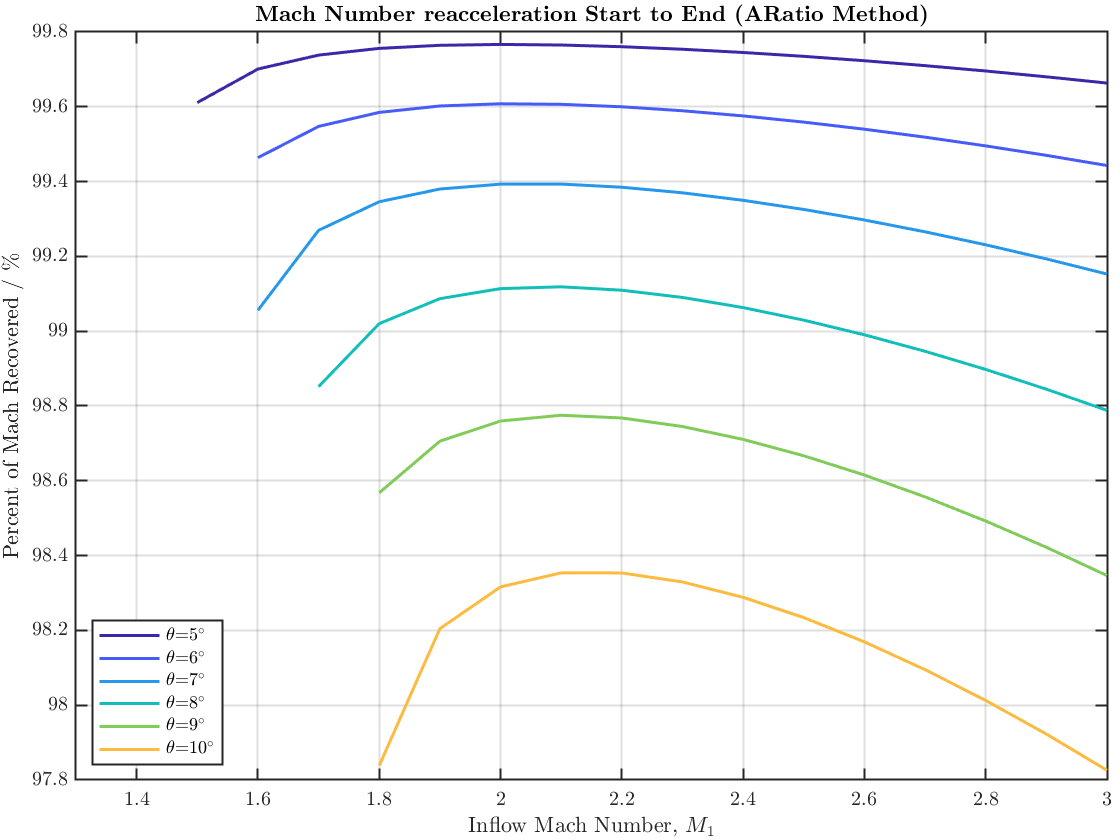


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
for line = 1:length(theta1)
plot(M1,Recovery_MachRatio_AR(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,'location','southwest')
xlabel("Inflow Mach Number, $M_{1}$")
ylabel("Percent of Mach Recovered / \%")
title("\textbf{Mach Number reacceleration Start to End (ARatio Method)}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

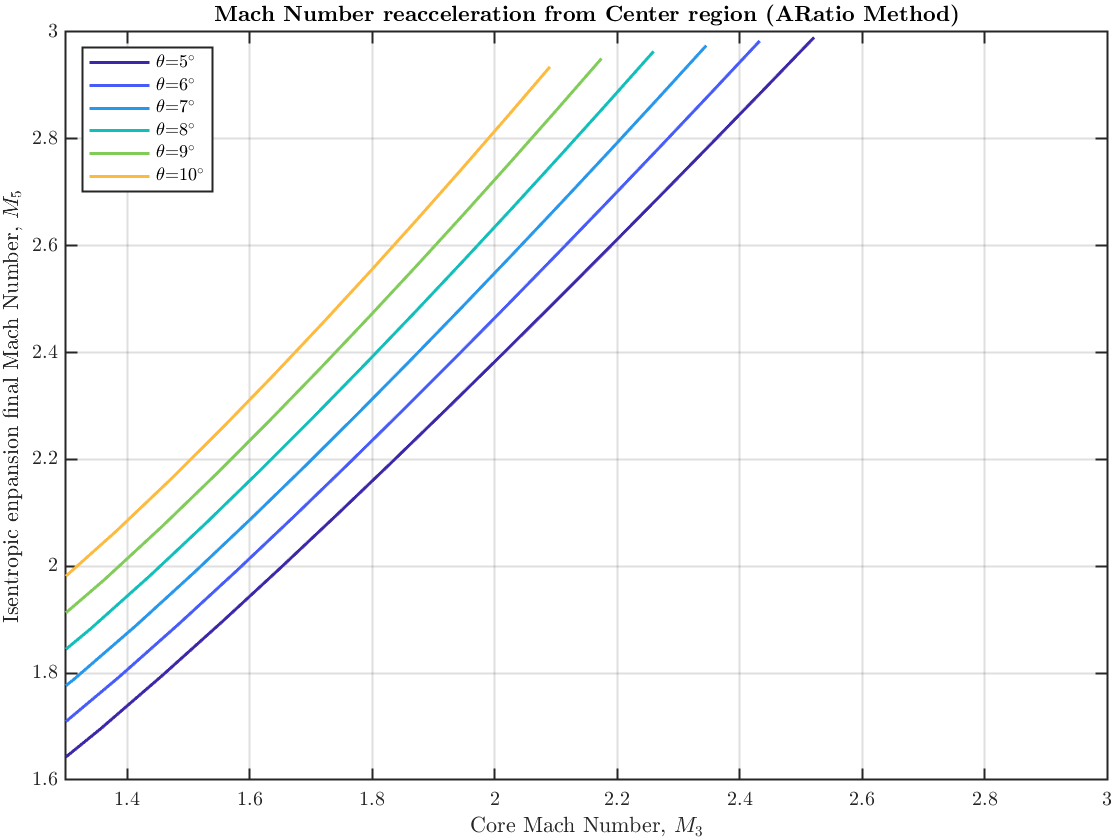


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
for line = 1:length(theta1)
plot(M3(line,:),M5_AR(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend(legendCelltheta,'location','northwest')
xlabel("Core Mach Number, $M_{3}$")
ylabel("Isentropic enpansion final Mach Number, $M_{5}$")
title("\textbf{Mach Number reacceleration from Center region (ARatio Method)}")
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Full Expansion Intersection

% Opposing Expansion crossing - to return to Mach Numbers...

% % LOSSES
% MachLoss = M1-M4; %Oulet/inlet
% MachLoss_Percent = (MachLoss./M1)*100;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%There is NOT any Mach - Loss as we still need to expand across the fan
%from the other side!!

% figure
% for line = 1:length(theta1)
% plot(M1,MachLoss_Percent(line,:),'Color',cmap(line,:),"LineWidth",1.5)
% hold on
% end
% formatSpec = '%.2f';
% legendCelltheta = strcat('\theta=',string(num2cell(theta1)),'^\circ');
% legendCell = strcat('(t/c=',string(num2cell(100*t)),'%)');
% xlabel("Mach Number, M")
% ylabel("Mach Number Drop / % of Inlet Mach")
% legend(legendCelltheta,"location","northwest")
% title("Mach loss from Inlet to Outlet")
% grid on
% xlim([min(M1),max(M1)])
% box off
% hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Inital Drag Calculations

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Renaming due to earlier flaws
P1 = Pr1;
P2 = Pr2;
P3 = TotalPr;

% We can obtain the pressures of the expansions as such
P4 = isentropicPr(M3,M4,P3,gamma);
P5 = isentropicPr(M4,M5_AR,P4,gamma); %(Assumed we can scale with the Mach number of outflow) 
Pv = 0.5*(P4+P5);

% Dynamic Head in terms of 1/P_inf
q_inf = 0.5*gamma*P1.*M1.^2;

% Associated Pressure coefficients
Cp1 = P1.*(P1-1)./q_inf;
Cp2 = P1.*(P2-1)./q_inf;
Cp3 = P1.*(P3-1)./q_inf;
Cp4 = P1.*(P4-1)./q_inf;
Cpv = P1.*(Pv-1)./q_inf;
Cp5 = P1.*(P5-1)./q_inf;

% Associated Lengths for Drag
l2 = sqrt(t.^2+(c/2).^2);
l4 = F1./transpose(cosd(theta1));
lv = transpose(l2)-(l4);
%lv = F2./transpose(cosd(theta1));

% Area
% Unsure if to use projected, planform or a thickness based assumption
% Area = 2*t
Area = 1; %Unit area - PLANFORM i.e. one surface only

% Total Drag
Drag = 2*P1.*transpose(sind(theta1)).*((transpose(l2).*P2)-(l4.*P4)-(lv.*Pv));

% Total Cd
Cd = Drag./(q_inf.*transpose(Area))

Cd =        NaN       NaN    0.0031    0.0018    0.0013    0.0010    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003
       NaN       NaN       NaN    0.0038    0.0025    0.0019    0.0015    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005
       NaN       NaN       NaN    0.0084    0.0046    0.0033    0.0026    0.0021    0.0018    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0009    0.0008
       NaN       NaN       NaN       NaN    0.0088    0.0057    0.0043    0.0035    0.0029    0.0025    0.0022    0.0020    0.0018    0.0017    0.0015    0.0014    0.0013    0.0013
       NaN       NaN       NaN       NaN       NaN    0.0097    0.0069    0.0054    0.0045    0.0038    0.0034    0.0030    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018
       NaN       NaN       NaN       NaN       NaN    0.0194    0.0110    0.0082    0.0067


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Igra & Arad (2007)

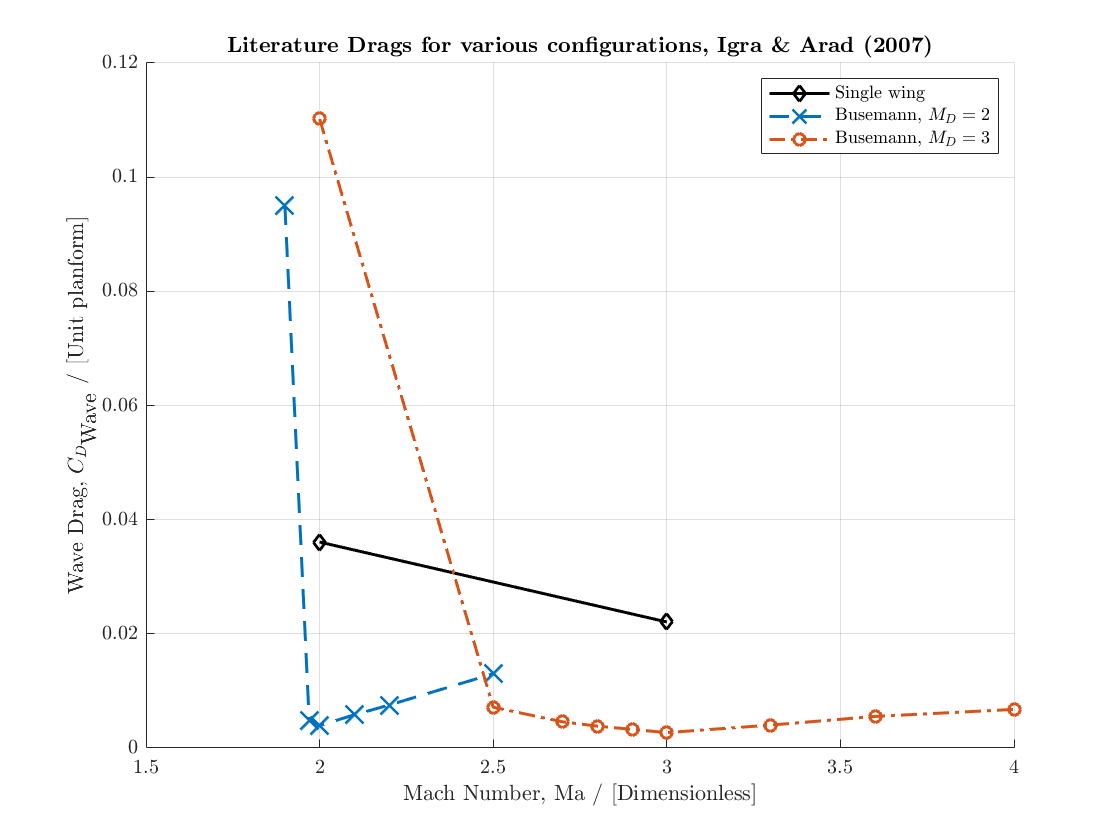

% FEBRUARY 2021
% IGRA AND ARAD  - A PARAMETRIC STUDY OF BUSEMANN BIPLANE PHENOMENA

%FIG 4 - Here we see drag coeffiecients two biplane spacings at two diff mach numbers - Mach, Cd (what kind?)
%Single Wing
IgraArad_fig4_sw_mach=[2,3];
IgraArad_fig4_sw_cd=[0.03607565,0.022080378];
%Busemann Wing Md2
IgraArad_fig4_Md2_mach=[1.9,1.97,2,2.1,2.2,2.5];
IgraArad_fig4_Md2_cd=[0.095082742,0.004869976,0.00392435,0.005815603,0.00751773,0.013002364];
%Busemann Wing Md3
IgraArad_fig4_Md3_mach=[2,2.5,2.7,2.8,2.9,3,3.3,3.6,4];
IgraArad_fig4_Md3_cd=[0.110212766,0.00713948,0.004586288,0.003829787,0.003262411,0.002695035,0.004018913,0.005531915,0.006761229];

figure
plot(IgraArad_fig4_sw_mach,IgraArad_fig4_sw_cd,'kd-',"LineWidth",1.5)
hold on
plot(IgraArad_fig4_Md2_mach,IgraArad_fig4_Md2_cd,'x--',"LineWidth",1.5,"MarkerSize",10,'color',[0 0.4470 0.7410])
hold on
plot(IgraArad_fig4_Md3_mach,IgraArad_fig4_Md3_cd,'o-.',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drags for various configurations, Igra \& Arad (2007)}")
legend("Single wing","Busemann, $M_{D}=2$","Busemann, $M_{D}=3$", "Location","northeast","NumColumns",1)
ylim([0,0.12]);
box off
grid on
hold off

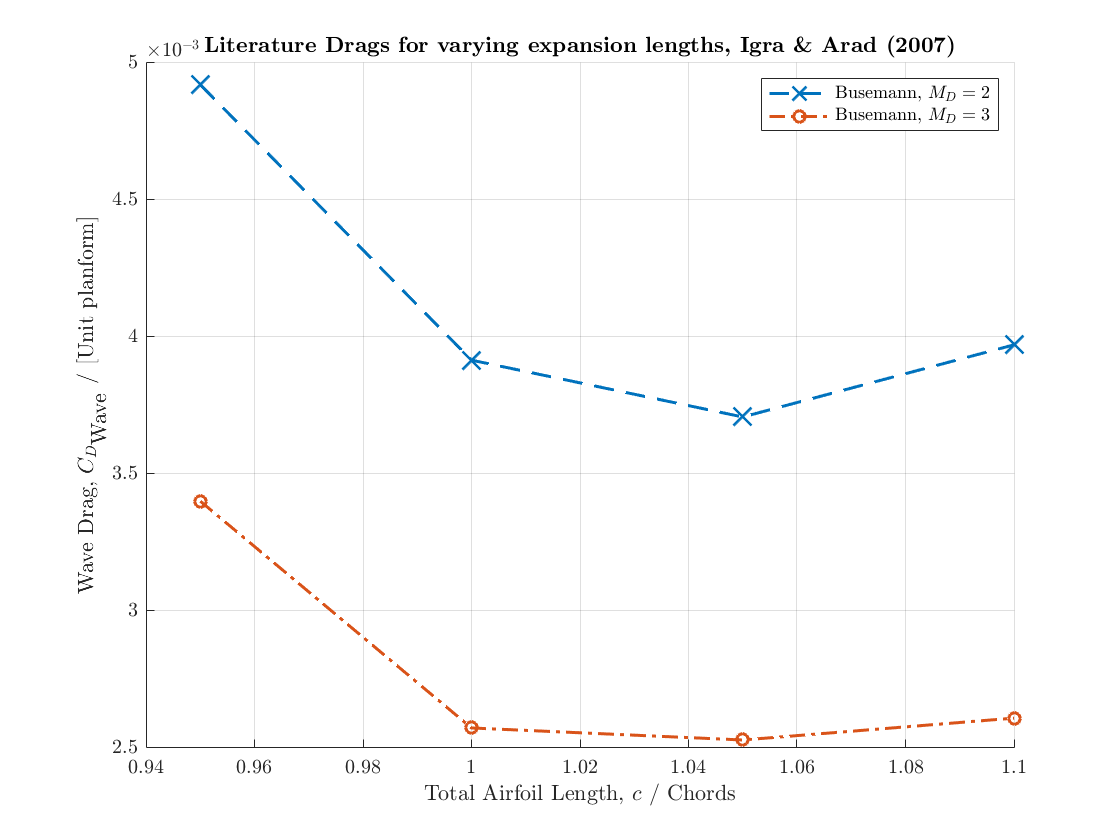


%FIG 6 - varying the expansion surface length - length meters,Cd
%MD2 X Y
IgraArad_fig6_length=[0.95,1.0,1.05,1.1]; %total airfoil length
IgraArad_fig6_MD2_CD=0.001*[4.92087766,3.915558511,3.708111702,3.971409574];
%MD3 X Y
IgraArad_fig6_MD3_CD=0.001*[3.400930851,2.573138298,2.529255319,2.609042553];

figure
plot(IgraArad_fig6_length,IgraArad_fig6_MD2_CD,'x--',"LineWidth",1.5,"MarkerSize",10)
hold on
plot(IgraArad_fig6_length,IgraArad_fig6_MD3_CD,'o-.',"LineWidth",1.5)
hold on
xlabel("Total Airfoil Length, $c$ / Chords")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drags for varying expansion lengths, Igra \& Arad (2007)}")
legend("Busemann, $M_{D}=2$","Busemann, $M_{D}=3$", "Location","northeast","NumColumns",1)
ylim([2.5*0.001,0.001*5]);
box off
grid on
hold off

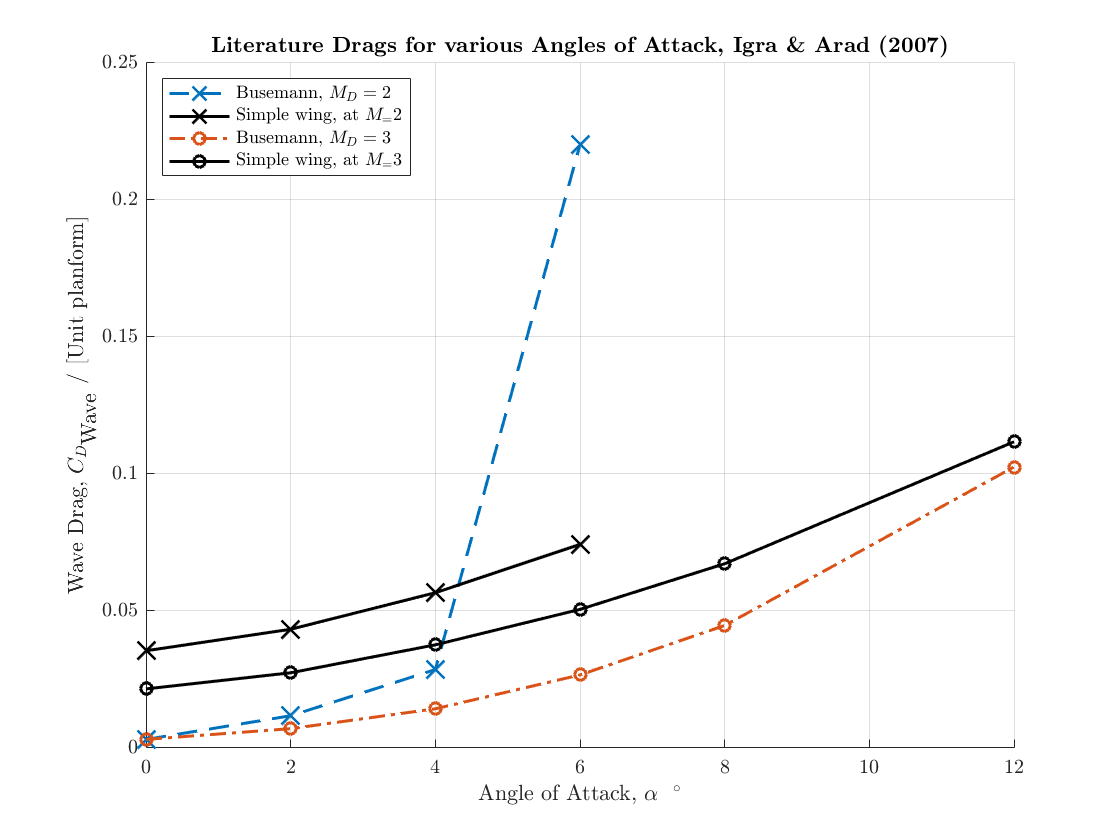


%FIG 9 - cd at various AoA - angle degrees, cd
%busemann biplane md2
IgraArad_fig9_aoa_m2=[0,2,4,6];
IgraArad_fig9_biplane_m2=[0.003137255,0.011764706,0.028627451,0.220196078];
%single wing m2
IgraArad_fig9_sw_m2=[0.035490196,0.043333333,0.056666667,0.074313725];
%bisemann biplane md3
IgraArad_fig9_aoa_m3=[0,2,4,6,8,12];
IgraArad_fig9_biplane_m3=[0.003137255,0.007058824,0.014313725,0.026666667,0.044705882,0.10254902];
%single wing m3
IgraArad_fig9_sw_m3=[0.021568627,0.02745098,0.037647059,0.050588235,0.067254902,0.111764706];

figure
plot(IgraArad_fig9_aoa_m2,IgraArad_fig9_biplane_m2,'x--',"LineWidth",1.5,"MarkerSize",10,'color',[0 0.4470 0.7410])
hold on
plot(IgraArad_fig9_aoa_m2,IgraArad_fig9_sw_m2,'x-k',"LineWidth",1.5,"MarkerSize",10)
hold on
plot(IgraArad_fig9_aoa_m3,IgraArad_fig9_biplane_m3,'o-.',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
plot(IgraArad_fig9_aoa_m3,IgraArad_fig9_sw_m3,'o-k',"LineWidth",1.5)
xlabel("Angle of Attack, $\alpha$ \ $^{\circ}$")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drags for various Angles of Attack, Igra \& Arad (2007)}")
legend("Busemann, $M_{D}=2$","Simple wing, at $M_=2$","Busemann, $M_{D}=3$","Simple wing, at $M_=3$", "Location","northwest","NumColumns",1)
box off
grid on
hold off

## HU ET AL. 2011/2012

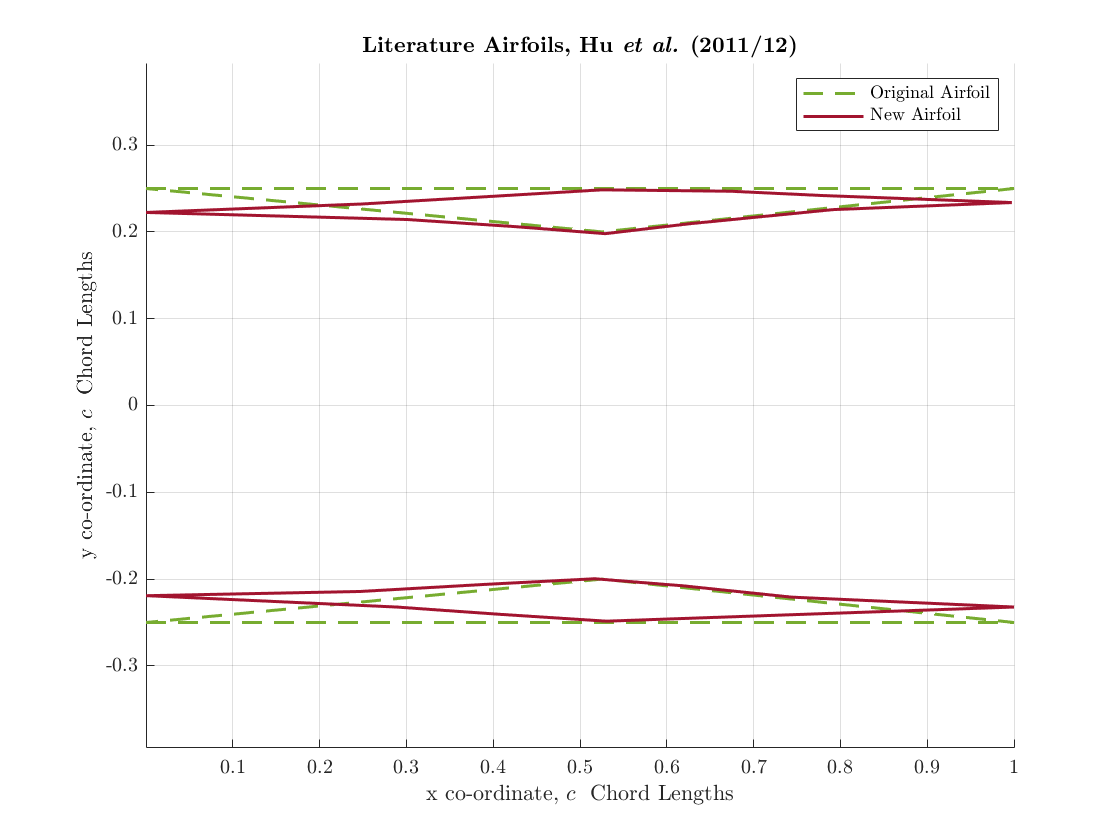

% HU ET AL. 2011/2012 - ADJOINT BASED AERODYNAMIC OPTIMIZATION OF SUPERSONIC BIPLANE AIRFOILS - 2011 aiaa conference, 2012 journal

%FIG 15 - airfoil plots - x,y series for all of them
%orginaltop
Hu_et_al_fig15_orginaltop=[1.8,3.132352941,2.5,1.8;0.25,0.25,0.2,0.25];
%original bot
Hu_et_al_fig15_orginalbot=[1.8,3.132352941,2.5,1.8;-0.25,-0.25,-0.2,-0.25];
%new top
Hu_et_al_fig15_newtop=[1.8,2.132352941,2.316993464,2.5,2.697712418,2.836601307,3.129084967,2.854575163,2.633986928,2.504901961,2.366013072,2.200980392,1.800653595;...
0.222403259,0.232179226,0.240325866,0.248472505,0.246843177,0.241955193,0.233808554,0.225661914,0.209368635,0.19796334,0.20610998,0.214256619,0.222403259];
%new bot
Hu_et_al_fig15_newbot=[1.8,2.129084967,2.320261438,2.488562092,2.624183007,2.790849673,3.132352941,2.818627451,2.506535948,2.33825294,2.184640523,1.802287582;...
-0.219144603,-0.214256619,-0.20610998,-0.199592668,-0.207739308,-0.220773931,-0.232179226,-0.240325866,-0.248472505,-0.240325866,-0.232179226,-0.219144603];

figure
plot((Hu_et_al_fig15_orginaltop(1,:)-1.8)/(3.132352941-1.8),Hu_et_al_fig15_orginaltop(2,:),'--',"LineWidth",1.5,'color',[0.4660 0.6740 0.1880])
hold on
plot((Hu_et_al_fig15_newtop(1,:)-1.8)/(3.132352941-1.8),Hu_et_al_fig15_newtop(2,:),'-',"LineWidth",1.5,'color',[0.6350 0.0780 0.1840])
hold on
plot((Hu_et_al_fig15_orginalbot(1,:)-1.8)/(3.132352941-1.8),Hu_et_al_fig15_orginalbot(2,:),'--',"LineWidth",1.5,"MarkerSize",10,'color',[0.4660 0.6740 0.1880])
hold on
plot((Hu_et_al_fig15_newbot(1,:)-1.8)/(3.132352941-1.8),Hu_et_al_fig15_newbot(2,:),'-',"LineWidth",1.5,'color',[0.6350 0.0780 0.1840])
xlabel("x co-ordinate, $c$ \ Chord Lengths")
ylabel("y co-ordinate, $c$ \ Chord Lengths")
title("\textbf{Literature Airfoils, Hu \textit{et al.} (2011/12)}")
legend("Original Airfoil","New Airfoil", "Location","northeast","NumColumns",1)
box off
axis equal
grid on
hold off

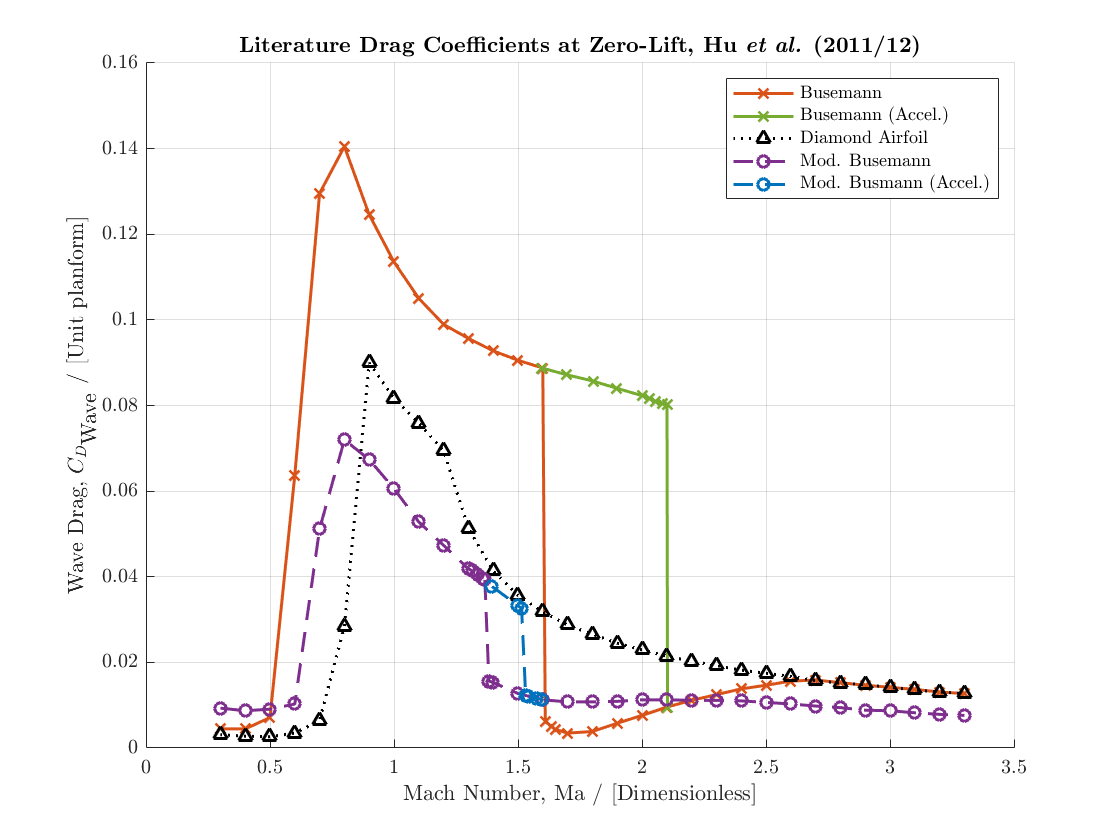


%FIG 16 - DRAG PLOT  - zero lift, Machs and Wave drags
%busemann
Hu_et_al_fig16_buseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.633744856,1.652263374,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_buseman_cd=[0.004453441,0.004453441,0.007125506,0.063724696,0.129554656,0.14048583,0.124574899,0.113522267,0.105020243,0.098947368,0.095668016,0.092753036,0.090566802,0.088744939,0.006153846,0.005060729,0.004331984,0.003481781,0.003846154,0.005789474,0.007611336,0.009554656,0.011133603,0.012469636,0.013805668,0.01465587,0.01562753,0.015870445,0.015263158,0.01465587,0.01417004,0.013684211,0.013076923,0.012712551];
%busemann accel
Hu_et_al_fig16_buseman_accel_machs=[1.596707819,1.697530864,1.802469136,1.899176955,2,2.030864198,2.053497942,2.082304527,2.100823045,2.102880658];
Hu_et_al_fig16_buseman_accel_cd=[0.088744939,0.087165992,0.085708502,0.084008097,0.082307692,0.081578947,0.08097166,0.08048583,0.080121457,0.009554656];
%diamond
Hu_et_al_fig16_diamond_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_diamond_cd=[0.003117409,0.002753036,0.002631579,0.003481781,0.006396761,0.028380567,0.089959514,0.081700405,0.075870445,0.069433198,0.051336032,0.041376518,0.035668016,0.031781377,0.028744939,0.026558704,0.024493927,0.02291498,0.02145749,0.020242915,0.019271255,0.018178138,0.017449393,0.016720648,0.015748988,0.0151417,0.014777328,0.01417004,0.013562753,0.013076923,0.012712551];
%modified accel
Hu_et_al_fig16_modifiedbuseman_accel_machs=[1.395061728,1.5,1.514403292,1.530864198,1.541152263,1.574074074,1.596707819];
Hu_et_al_fig16_modifiedbuseman_accel_cd=[0.037732794,0.033238866,0.032631579,0.012226721,0.011983806,0.011619433,0.011376518];
%modified
Hu_et_al_fig16_modifiedbuseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.314814815,1.335390947,1.355967078,1.366255144,1.382716049,1.397119342,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_modifiedbuseman_cd=[0.009311741,0.008704453,0.009068826,0.010283401,0.051214575,0.071983806,0.067368421,0.060566802,0.052793522,0.047327935,0.041862348,0.041376518,0.040526316,0.039676113,0.039311741,0.01562753,0.015384615,0.012712551,0.011255061,0.010769231,0.010769231,0.010890688,0.011255061,0.011255061,0.011133603,0.011133603,0.011012146,0.010647773,0.010283401,0.009797571,0.009433198,0.008825911,0.008704453,0.008218623,0.007854251,0.007611336];

figure
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",1.5,'color',[0.4660 0.6740 0.1880])
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",1.5,'color',[0 0 0])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",1.5,'color',[0.4940 0.1840 0.5560])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",1.5,'color',[0 0.4470 0.7410])
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drag Coefficients at Zero-Lift, Hu \textit{et al.} (2011/12)}")
legend("Busemann","Busemann (Accel.)","Diamond Airfoil","Mod. Busemann","Mod. Busmann (Accel.)", "Location","northeast","NumColumns",1)
ylim([0 0.16])
box off
grid on
hold off

## Kusunose et al (2011)

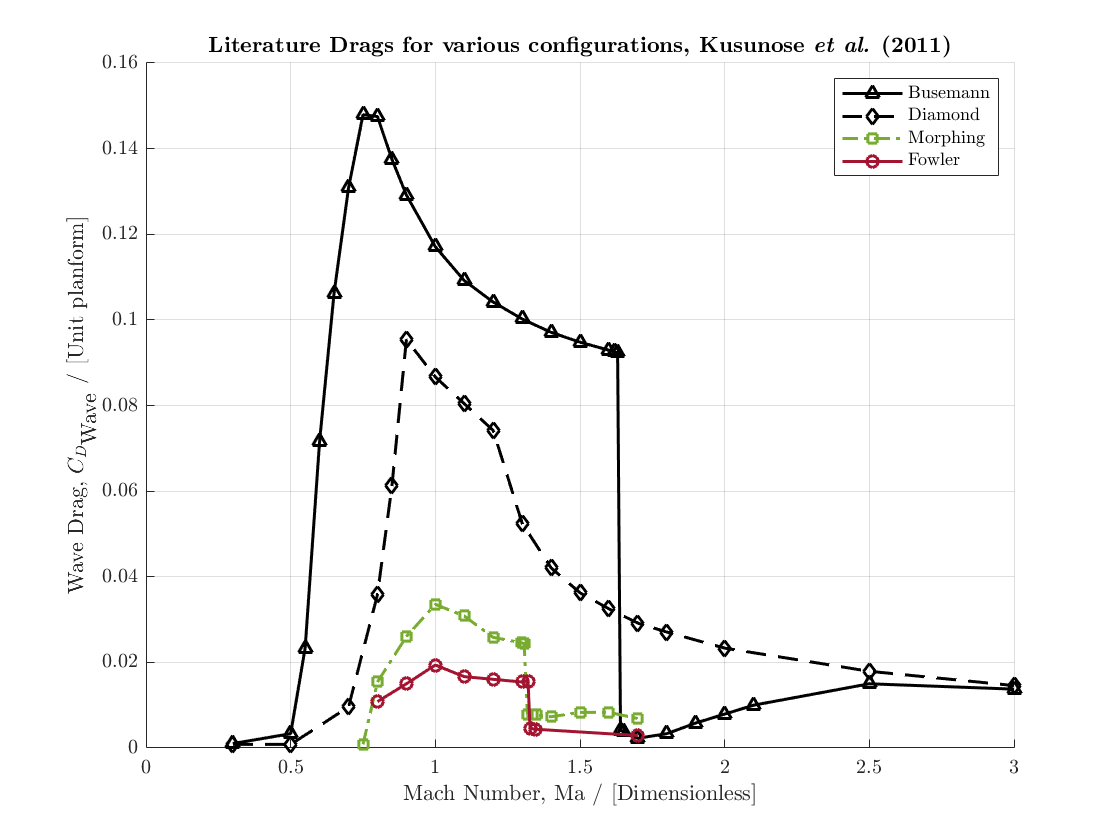

% KUSUNOSE  - Supersonic biplane—A review

%FIG 18 - cdwave across machs for 4 different airfoils
%busemann		diamond airfoil		morphing		fowler
Kusunose_review_fig18_buseman_machs=[0.3,0.5,0.55,0.6,0.65,0.7,0.75,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.62,1.63,1.64,1.65,1.7,1.8,1.9,2,2.1,2.5,3];
Kusunose_review_fig18_buseman_cd=[0.001041667,0.003333333,0.023333333,0.071666667,0.10625,0.130833333,0.147916667,0.1475,0.1375,0.129166667,0.117083333,0.109166667,0.104166667,0.100208333,0.097083333,0.094791667,0.092916667,0.0925,0.092291667,0.004166667,0.00375,0.002291667,0.003333333,0.005833333,0.007916667,0.01,0.015,0.01375];

Kusunose_review_fig18_diamond_machs=[0.3,0.5,0.7,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,2,2.5,3];
Kusunose_review_fig18_diamond_cd=[0.000833333,0.000833333,0.009583333,0.035833333,0.06125,0.095416667,0.086666667,0.080416667,0.074166667,0.0525,0.042083333,0.03625,0.0325,0.029166667,0.027083333,0.023333333,0.017916667,0.014583333];

Kusunose_review_fig18_morphing_machs=[0.75,0.8,0.9,1,1.1,1.2,1.297727273,1.306818182,1.318181818,1.336363636,1.35,1.4,1.5,1.6,1.7];
Kusunose_review_fig18_morphing_cd=[0.000833333,0.015416667,0.026041667,0.033541667,0.030833333,0.025833333,0.024583333,0.024375,0.007916667,0.007916667,0.007708333,0.007291667,0.008333333,0.008333333,0.006875];

Kusunose_review_fig18_fowler_machs=[0.8,0.9,1,1.1,1.2,1.3,1.3,1.320454545,1.327272727,1.347727273,1.7];
Kusunose_review_fig18_fowler_cd=[0.010833333,0.015,0.019375,0.016666667,0.016041667,0.015416667,0.015625,0.015625,0.004583333,0.004375,0.002916667];

figure
plot(Kusunose_review_fig18_buseman_machs,Kusunose_review_fig18_buseman_cd,'k^-',"LineWidth",1.5)
hold on
plot(Kusunose_review_fig18_diamond_machs,Kusunose_review_fig18_diamond_cd,'kd--',"LineWidth",1.5)
hold on
plot(Kusunose_review_fig18_morphing_machs,Kusunose_review_fig18_morphing_cd,'s-.',"LineWidth",1.5,'color',[0.4660 0.6740 0.1880])
hold on
plot(Kusunose_review_fig18_fowler_machs,Kusunose_review_fig18_fowler_cd,'o-',"LineWidth",1.5,'color',[0.6350 0.0780 0.1840])
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drags for various configurations, Kusunose \textit{et al.} (2011)}")
legend("Busemann","Diamond","Morphing","Fowler", "Location","northeast","NumColumns",1)
ylim([0,0.16]);
box off
grid on
hold off

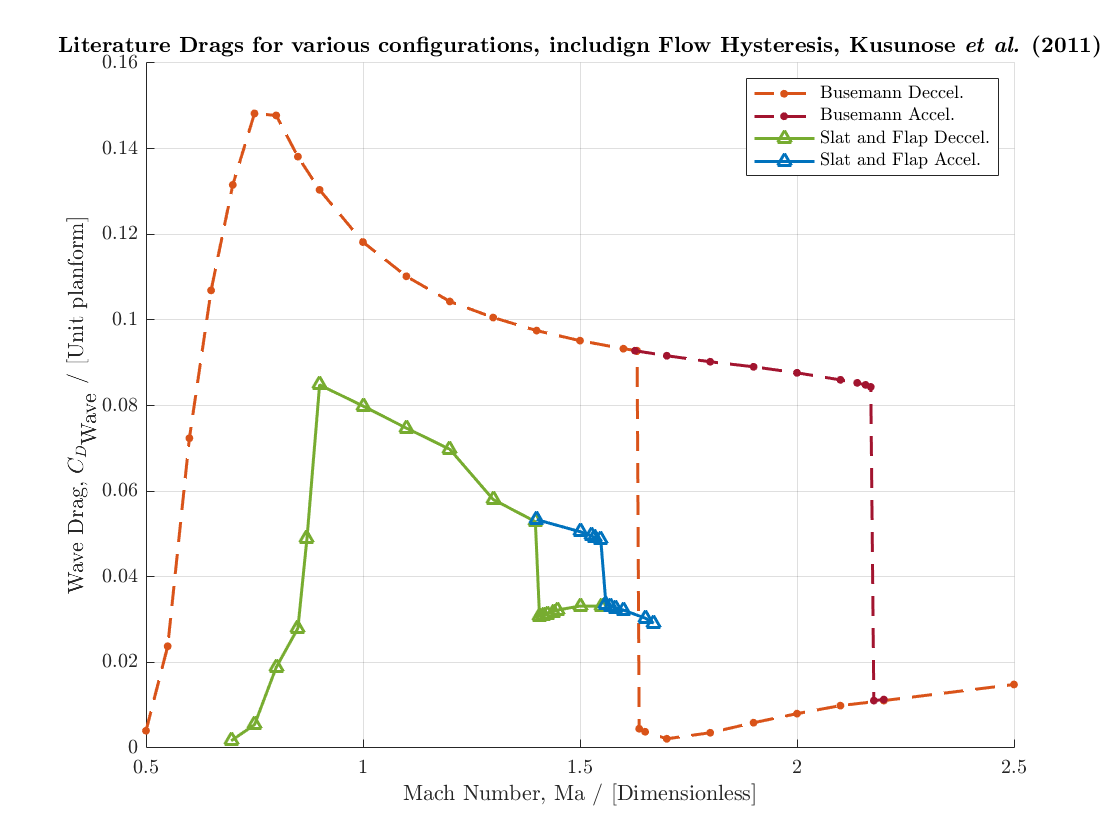


%FIG 25 - again cdwave as a function of Mach
%busemann deccel		busemann accel		slat and flap decell		slat and flap accel
Kusunose_review_fig25_busemandeccel_machs=[0.5,0.55,0.6,0.65,0.7,0.75,0.80,0.85,0.90,1,1.1,1.2,1.3,1.4,1.5,1.6,1.631578947,1.636363636,1.65,1.7,1.8,1.9,2,2.1,2.2,2.5];
Kusunose_review_fig25_busemandeccel_cd=[0.004031311,0.023757339,0.072367906,0.106888454,0.131545988,0.148219178,0.147749511,0.138121331,0.13037182,0.11816047,0.110176125,0.104305284,0.100547945,0.097495108,0.095146771,0.093268102,0.092798434,0.004500978,0.003796477,0.002152642,0.003561644,0.00590998,0.008023483,0.009902153,0.011076321,0.014833659];

Kusunose_review_fig25_busemanaccel_machs=[1.626794258,1.7,1.8,1.9,2,2.1,2.138755981,2.157894737,2.17,2.177033493,2.2];
Kusunose_review_fig25_busemanaccel_cd=[0.092798434,0.091624266,0.090215264,0.089041096,0.087632094,0.085988258,0.085283757,0.08481409,0.084344423,0.011076321,0.011311155];

Kusunose_review_fig25_slatandflapdeccel_machs=[0.696172249,0.75,0.8,0.85,0.870813397,0.9,1,1.1,1.2,1.3,1.397129187,1.406698565,1.416267943,1.425837321,1.437799043,1.447368421,1.5,1.55];
Kusunose_review_fig25_slatandflapdeccel_cd=[0.001682975,0.005440313,0.018825832,0.027984344,0.04888454,0.08481409,0.079882583,0.074716243,0.069784736,0.058043053,0.052876712,0.030802348,0.031037182,0.031272016,0.031741683,0.03221135,0.033150685,0.033150685];

Kusunose_review_fig25_slatandflapaccel_machs=[1.4,1.5,1.526315789,1.533492823,1.54784689,1.559808612,1.56937799,1.581339713,1.60,1.65,1.67];
Kusunose_review_fig25_slatandflapaccel_cd=[0.05334638,0.050528376,0.049589041,0.049119374,0.048649706,0.033620352,0.033150685,0.032681018,0.03221135,0.030332681,0.029158513];

figure
plot(Kusunose_review_fig25_busemandeccel_machs,Kusunose_review_fig25_busemandeccel_cd,'.--',"LineWidth",1.5,"MarkerSize",10,'color',[0.8500 0.3250 0.0980])
hold on
plot(Kusunose_review_fig25_busemanaccel_machs,Kusunose_review_fig25_busemanaccel_cd,'.--',"LineWidth",1.5,"MarkerSize",10,'color',[0.6350 0.0780 0.1840])
hold on
plot(Kusunose_review_fig25_slatandflapdeccel_machs,Kusunose_review_fig25_slatandflapdeccel_cd,'^-',"LineWidth",1.5,'color',[0.4660 0.6740 0.1880])
hold on
plot(Kusunose_review_fig25_slatandflapaccel_machs,Kusunose_review_fig25_slatandflapaccel_cd,'^-',"LineWidth",1.5,'color',[0 0.4470 0.7410])
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drags for various configurations, includign Flow Hysteresis, Kusunose \textit{et al.} (2011)}")
legend("Busemann Deccel.","Busemann Accel.","Slat and Flap Deccel.","Slat and Flap Accel.", "Location","northeast","NumColumns",1)
ylim([0,0.16]);
box off
grid on
hold off

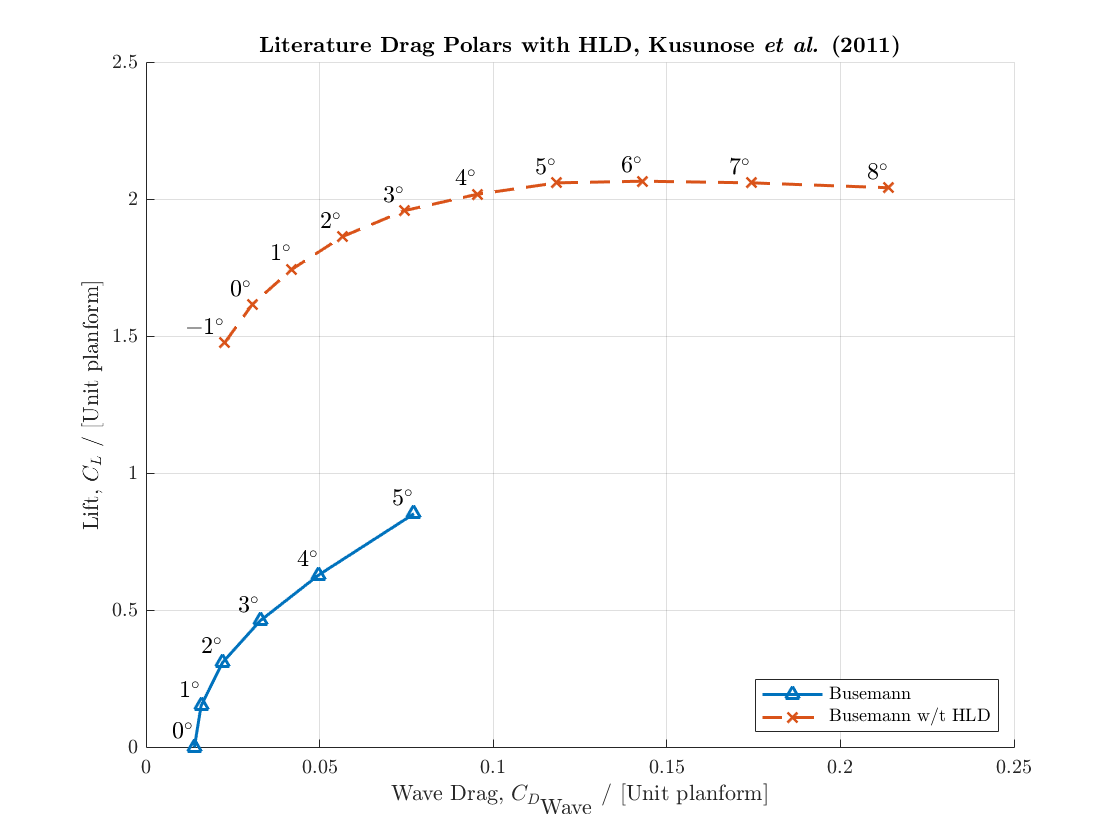


%FIG 27 - drag polar: cd and cl for a given alfa
%	Buseman			busemann with hld
Kusunose_review_fig27_buseman_alfa={'$0^{\circ}$' '$1^{\circ}$' '$2^{\circ}$' '$3^{\circ}$' '$4^{\circ}$' '$5^{\circ}$'};
Kusunose_review_fig27_buseman_cl=[0.001988072,0.154075547,0.312127237,0.464214712,0.631212724,0.854870775];
Kusunose_review_fig27_buseman_cd=[0.013926499,0.015860735,0.02205029,0.032882012,0.049709865,0.077176015];

Kusunose_review_fig27_busemanhld_alfa={'$-1^{\circ}$' '$0^{\circ}$' '$1^{\circ}$' '$2^{\circ}$' '$3^{\circ}$' '$4^{\circ}$' '$5^{\circ}$' '$6^{\circ}$' '$7^{\circ}$' '$8^{\circ}$'};
Kusunose_review_fig27_busemanhld_cl=[1.478131213,1.618290258,1.746520875,1.865805169,1.961232604,2.020874751,2.062624254,2.068588469,2.062624254,2.04473161];
Kusunose_review_fig27_busemanhld_cd=[0.022630561,0.030560928,0.041972921,0.056479691,0.074468085,0.095357834,0.118375242,0.143133462,0.174274662,0.213926499];

figure
plot(Kusunose_review_fig27_buseman_cd,Kusunose_review_fig27_buseman_cl,'^-',"LineWidth",1.5,'color',[0 0.4470 0.7410])
hold on
labelpoints(Kusunose_review_fig27_buseman_cd,Kusunose_review_fig27_buseman_cl,Kusunose_review_fig27_buseman_alfa,'FontSize', 12,'interpreter', 'latex')
hold on
plot(Kusunose_review_fig27_busemanhld_cd,Kusunose_review_fig27_busemanhld_cl,'x--',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
labelpoints(Kusunose_review_fig27_busemanhld_cd,Kusunose_review_fig27_busemanhld_cl,Kusunose_review_fig27_busemanhld_alfa,'FontSize', 12,'interpreter', 'latex')
hold on
ylabel("Lift, $C_{L}$ / [Unit planform]")
xlabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drag Polars with HLD, Kusunose \textit{et al.} (2011)}")
legend("Busemann","Busemann w/t HLD", "Location","southeast","NumColumns",1)
%ylim([0,0.12]);
box off
grid on
hold off

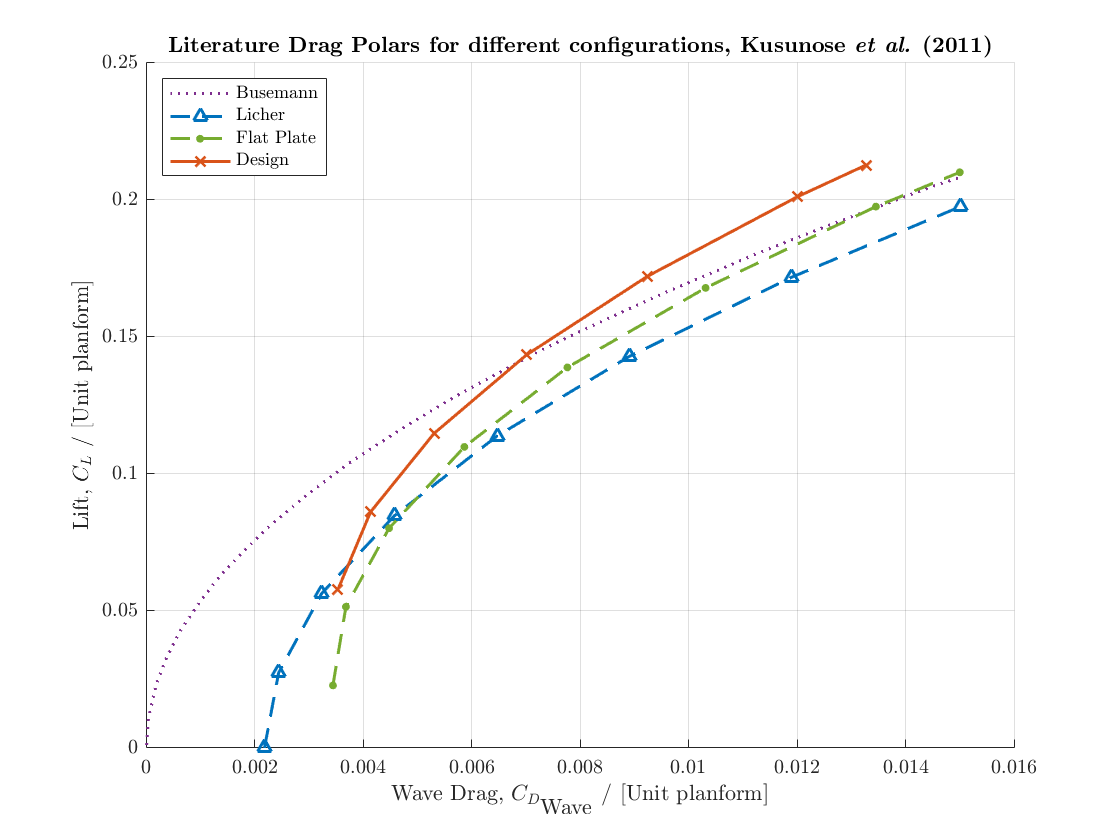


%FIG 40 - every half degree plotted
%busemann t/c=0.100		licher-type biplane t/c=0.106		flat plate theory t/c=0		design biplane t/c = 0.102
Kusunose_review_fig40_buseman_cd=[0.002183591,0.002445167,0.003241267,0.004583266,0.006471162,0.008904955,0.011907392,0.015012185];
Kusunose_review_fig40_buseman_cl=[0,0.027472527,0.056483516,0.084835165,0.113846154,0.142857143,0.171868132,0.197582418];

Kusunose_review_fig40_licher_cd=[0.003445979,0.003684809,0.00448091,0.0058684,0.007767669,0.010315191,0.013454102,0.015000812];
Kusunose_review_fig40_licher_cl=[0.022857143,0.051538462,0.08021978,0.10989011,0.138901099,0.167912088,0.197582418,0.21010989];

Kusunose_review_fig40_flat_cd=[0.0000114,0.0000455,0.000193339,0.000375305,0.000625508,0.001012185,0.001376117,0.001808286,0.002251828,0.002968318,0.003741673,0.004196588,0.004924452,0.005766044,0.006380179,0.007244517,0.00797238,0.008836718,0.009610073,0.010406174,0.011179529,0.011850528,0.012703493,0.01368156,0.01447766,0.014989439];
Kusunose_review_fig40_flat_cl=[0.001098901,0.010989011,0.023516484,0.032747253,0.042637363,0.053846154,0.063076923,0.071978022,0.080549451,0.092417582,0.103956044,0.10989011,0.119120879,0.129010989,0.135604396,0.144835165,0.151758242,0.15967033,0.166593407,0.173186813,0.17978022,0.185054945,0.191648352,0.198901099,0.204835165,0.208131868];

Kusunose_review_fig40_design_cd=[0.003536962,0.004139724,0.005311129,0.007017059,0.009246141,0.012009748,0.013272136];
Kusunose_review_fig40_design_cl=[0.057802198,0.086153846,0.114835165,0.143516484,0.172197802,0.201208791,0.212747253];

figure
plot(Kusunose_review_fig40_flat_cd,Kusunose_review_fig40_flat_cl,':',"LineWidth",1.5,'color',[0.4940 0.1840 0.5560])
hold on
plot(Kusunose_review_fig40_buseman_cd,Kusunose_review_fig40_buseman_cl,'^--',"LineWidth",1.5,'color',[0 0.4470 0.7410])
hold on
plot(Kusunose_review_fig40_licher_cd,Kusunose_review_fig40_licher_cl,'.--',"LineWidth",1.5,"MarkerSize",10,'color',[0.4660 0.6740 0.1880])
hold on
plot(Kusunose_review_fig40_design_cd,Kusunose_review_fig40_design_cl,'x-',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
ylabel("Lift, $C_{L}$ / [Unit planform]")
xlabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drag Polars for different configurations, Kusunose \textit{et al.} (2011)}")
legend("Busemann","Licher","Flat Plate","Design", "Location","northwest","NumColumns",1)
%ylim([0,0.25]);
box off
grid on
hold off

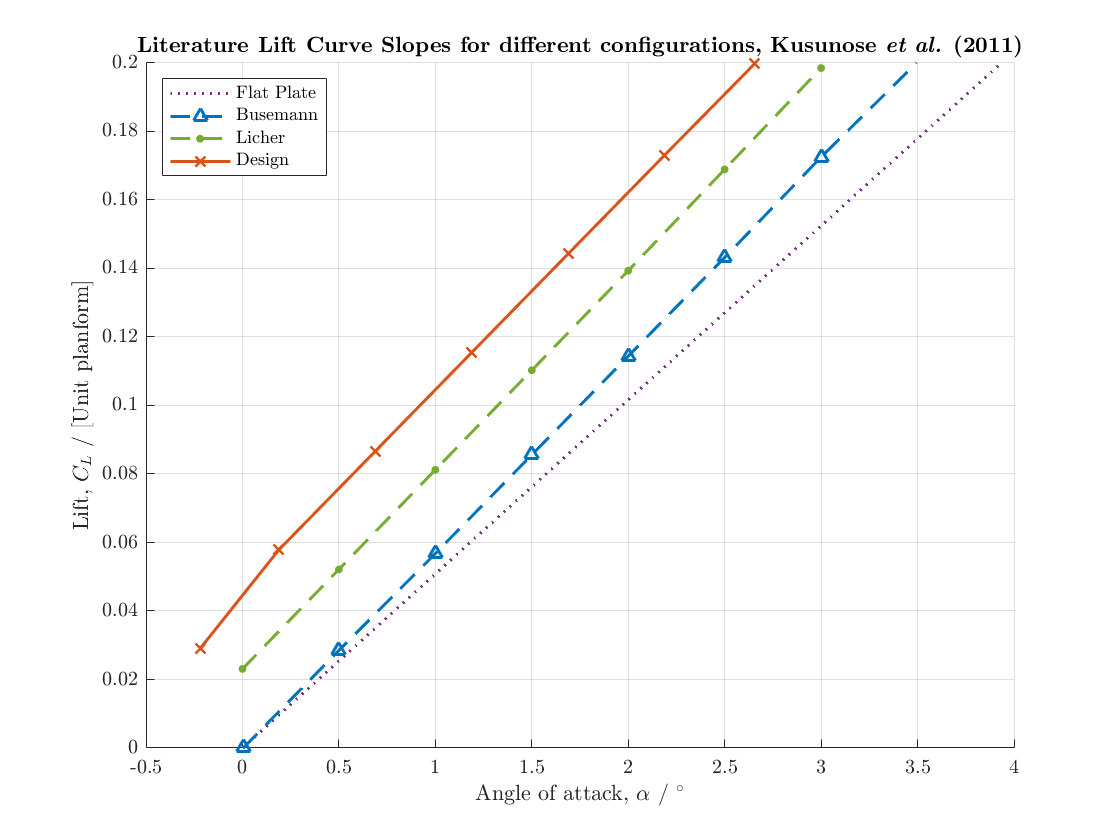


%FIG 41 - alfa cl series
%flat plate		busemann		licher		designed
Kusunose_review_fig41_flat_alfa=[0,3.936];
Kusunose_review_fig41_flat_cl=[0,0.200064309];

Kusunose_review_fig41_buseman_alfa=[0.004,0.5,1,1.5,2,2.5,3,3.5];
Kusunose_review_fig41_buseman_cl=[0,0.028488746,0.056784566,0.085594855,0.114405145,0.143215434,0.172540193,0.200321543];

Kusunose_review_fig41_licher_alfa=[0,0.5,1,1.5,2,2.5,3.0];
Kusunose_review_fig41_licher_cl=[0.023086817,0.052154341,0.081221865,0.110289389,0.139356913,0.168938907,0.1985209];

Kusunose_review_fig41_design_alfa=[-0.22,0.188,0.688,1.188,1.688,2.188,2.656];
Kusunose_review_fig41_design_cl=[0.029003215,0.057813505,0.086623794,0.115434084,0.144244373,0.173054662,0.199807074];

figure
plot(Kusunose_review_fig41_flat_alfa,Kusunose_review_fig41_flat_cl,':',"LineWidth",1.5,'color',[0.4940 0.1840 0.5560])
hold on
plot(Kusunose_review_fig41_buseman_alfa,Kusunose_review_fig41_buseman_cl,'^--',"LineWidth",1.5,'color',[0 0.4470 0.7410])
hold on
plot(Kusunose_review_fig41_licher_alfa,Kusunose_review_fig41_licher_cl,'.--',"LineWidth",1.5,"MarkerSize",10,'color',[0.4660 0.6740 0.1880])
hold on
plot(Kusunose_review_fig41_design_alfa,Kusunose_review_fig41_design_cl,'x-',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
ylabel("Lift, $C_{L}$ / [Unit planform]")
xlabel("Angle of attack, $\alpha$ / $^{\circ}$")
title("\textbf{Literature Lift Curve Slopes for different configurations, Kusunose \textit{et al.} (2011)}")
legend("Flat Plate","Busemann","Licher","Design", "Location","northwest","NumColumns",1)
ylim([0,0.2]);
box off
grid on
hold off

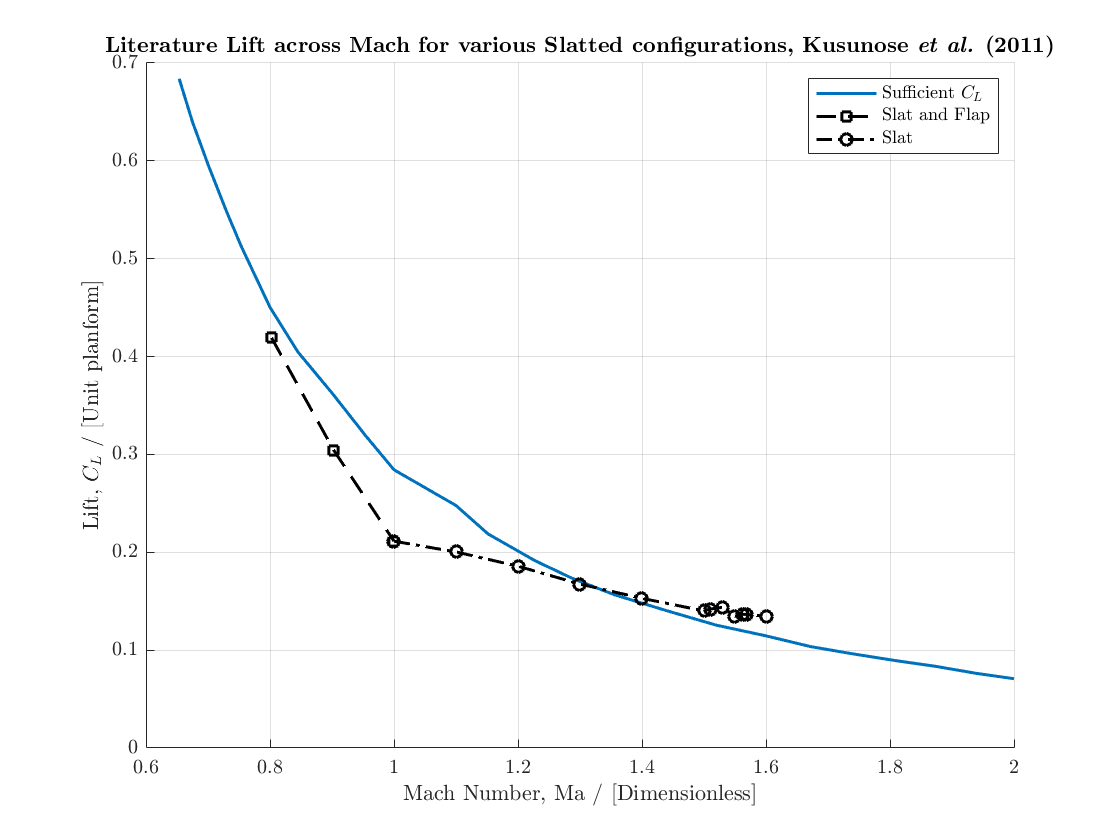


%FIG 81a - lift over mach
%sufficient cl		slat and flap		slat
Kusunose_review_fig81a_sufficientcl_machs=[0.653495441,0.674772036,0.7,0.729483283,0.753799392,0.8,0.844984802,0.9,0.954407295,1,1.1,1.151975684,1.227963526,1.288753799,1.3556231,1.440729483,1.519756839,1.6,1.671732523,1.738601824,1.811550152,1.872340426,1.939209726,2];
Kusunose_review_fig81a_sufficientcl_cl=[0.683941606,0.640145985,0.596350365,0.548905109,0.512408759,0.450364964,0.404744526,0.362773723,0.318978102,0.284306569,0.247810219,0.218613139,0.191240876,0.172992701,0.156569343,0.140145985,0.125547445,0.11459854,0.103649635,0.096350365,0.089051095,0.083576642,0.076277372,0.07080292];

Kusunose_review_fig81a_slatandflap_machs=[0.802431611,0.902735562,1];
Kusunose_review_fig81a_slatandflap_cl=[0.419343066,0.304379562,0.211313869];
Kusunose_review_fig81a_slat_machs=[1,1.1,1.2,1.3,1.4,1.5,1.51,1.53,1.55,1.56231003,1.568389058,1.6];
Kusunose_review_fig81a_slat_cl=[0.211313869,0.200364964,0.185766423,0.167518248,0.152919708,0.140145985,0.141970803,0.14379562,0.134671533,0.13649635,0.13649635,0.134671533];

figure
plot(Kusunose_review_fig81a_sufficientcl_machs,Kusunose_review_fig81a_sufficientcl_cl,'-',"LineWidth",1.5,'color',[0 0.4470 0.7410])
hold on
plot(Kusunose_review_fig81a_slatandflap_machs,Kusunose_review_fig81a_slatandflap_cl,'ks--',"LineWidth",1.5)
hold on
plot(Kusunose_review_fig81a_slat_machs,Kusunose_review_fig81a_slat_cl,'ko-.',"LineWidth",1.5)
hold on
ylabel("Lift, $C_{L}$ / [Unit planform]")
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
title("\textbf{Literature Lift across Mach for various Slatted configurations, Kusunose \textit{et al.} (2011)}")
legend("Sufficient $C_L$","Slat and Flap","Slat","Location","northeast","NumColumns",1)
%ylim([0,0.12]);
box off
grid on
hold off

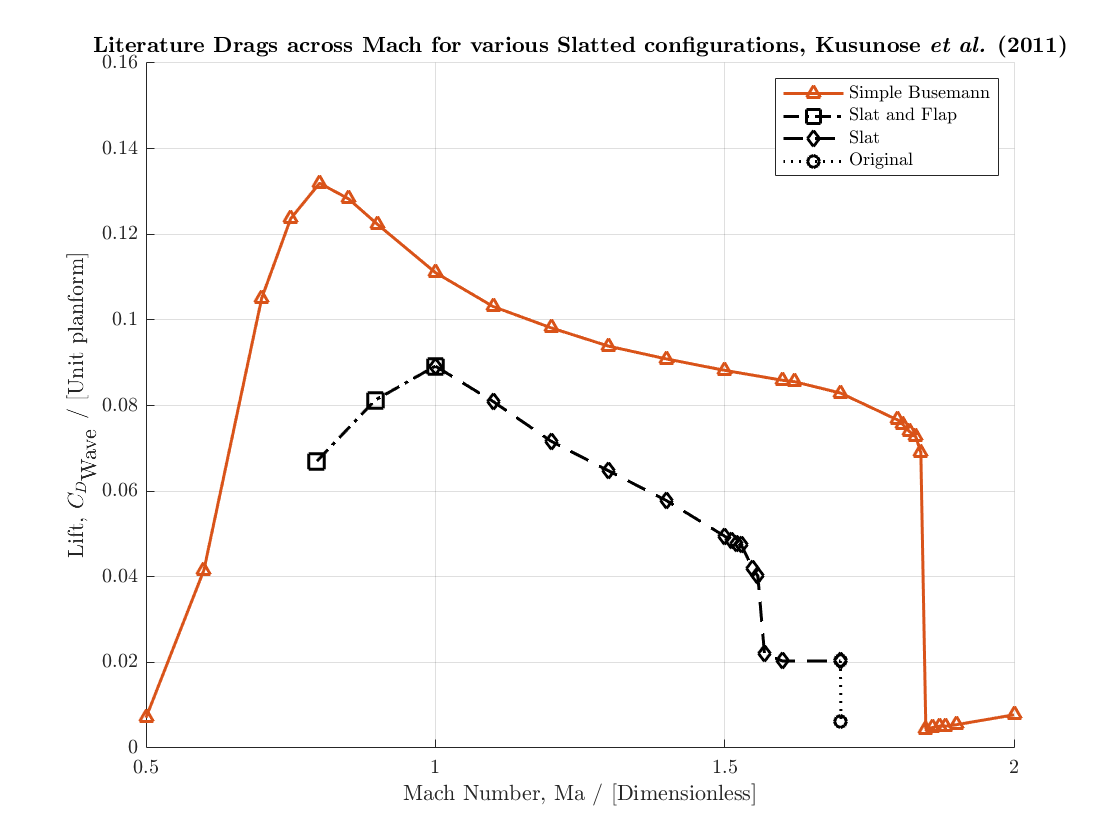


%FIG 81b - drag curves
%simple busemann zero lift		slat and flap		slat		original
Kusunose_review_fig81b_buseman_machs=[0.5,0.6,0.7,0.75,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.620533881,1.7,1.798767967,1.807392197,1.81889117,1.830390144,1.839014374,1.847638604,1.859137577,1.87063655,1.882135524,1.9,2];
Kusunose_review_fig81b_buseman_cd=[0.007086093,0.041523179,0.105099338,0.123642384,0.13192053,0.128278146,0.122317881,0.111059603,0.103112583,0.098145695,0.09384106,0.090860927,0.088211921,0.08589404,0.085562914,0.082913907,0.076622517,0.075629139,0.07397351,0.072649007,0.069006623,0.004437086,0.004768212,0.005099338,0.005099338,0.005430464,0.007748344];

Kusunose_review_fig81b_slatandflap_machs=[0.795482546,0.896098563,1];
Kusunose_review_fig81b_slatandflap_cd=[0.067019868,0.081258278,0.089205298];

Kusunose_review_fig81b_slat_machs=[1,1.1,1.2,1.3,1.4,1.5,1.511293634,1.519917864,1.528542094,1.548665298,1.557289528,1.568788501,1.6,1.7];
Kusunose_review_fig81b_slat_cd=[0.089205298,0.080927152,0.071655629,0.064701987,0.057748344,0.049470199,0.048476821,0.04781457,0.047483444,0.041854305,0.040198675,0.021986755,0.020331126,0.020331126];

Kusunose_review_fig81b_original_machs=[1.7,1.701026694];
Kusunose_review_fig81b_original_cd=[0.020331126,0.006092715];

figure
plot(Kusunose_review_fig81b_buseman_machs,Kusunose_review_fig81b_buseman_cd,'^-',"LineWidth",1.5,'color',[[0.8500 0.3250 0.0980]])
hold on
plot(Kusunose_review_fig81b_slatandflap_machs,Kusunose_review_fig81b_slatandflap_cd,'ks-.',"LineWidth",1.5,"MarkerSize",10)
hold on
plot(Kusunose_review_fig81b_slat_machs,Kusunose_review_fig81b_slat_cd,'kd--',"LineWidth",1.5)
hold on
plot(Kusunose_review_fig81b_original_machs,Kusunose_review_fig81b_original_cd,'ko:',"LineWidth",1.5)
hold on
ylabel("Lift, $C_{D_{\textrm{Wave}}}$ / [Unit planform]")
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
title("\textbf{Literature Drags across Mach for various Slatted configurations, Kusunose \textit{et al.} (2011)}")
legend("Simple Busemann","Slat and Flap","Slat","Original","Location","northeast","NumColumns",1)
ylim([0,0.16]);
box off
grid on
hold off

## Drag Comparison

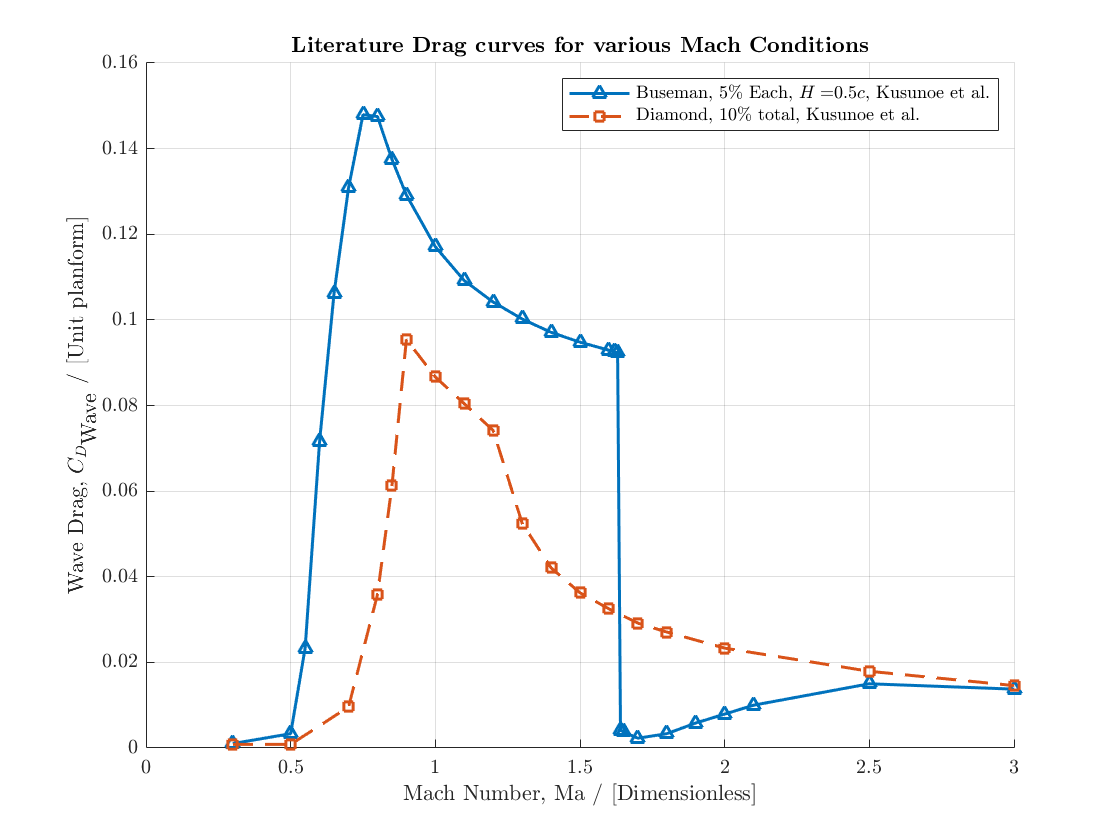

% Comparison to previuous data

% Kusunose et al. (2011)
MachRuns_buse = Kusunose_review_fig18_buseman_machs;
MachRuns_dia = Kusunose_review_fig18_diamond_machs;
Jpn_Busemann = Kusunose_review_fig18_buseman_cd;
Jpn_Diamond = Kusunose_review_fig18_diamond_cd;

%Jpn_alphas = [0:0.5:3.5];
%Jpn_dia_cl_euler =[0,0.0257,0.0515,0.0773,0.1031,0.1290,0.1550,0.1810];
%Jpn_dia_cdw_euler =[0.02891, 0.02914, 0.02983, 0.0316, 0.03264, 0.03475, 0.03734, 0.04041];
%Jpn_dia_LoverD_euler =Jpn_dia_cl_euler./Jpn_dia_cdw_euler;

figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",1.5)
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",1.5)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drag curves for various Mach Conditions}")
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.", "Location","northeast","NumColumns",1)
ylim([0,0.16]);
box off
grid on
hold off

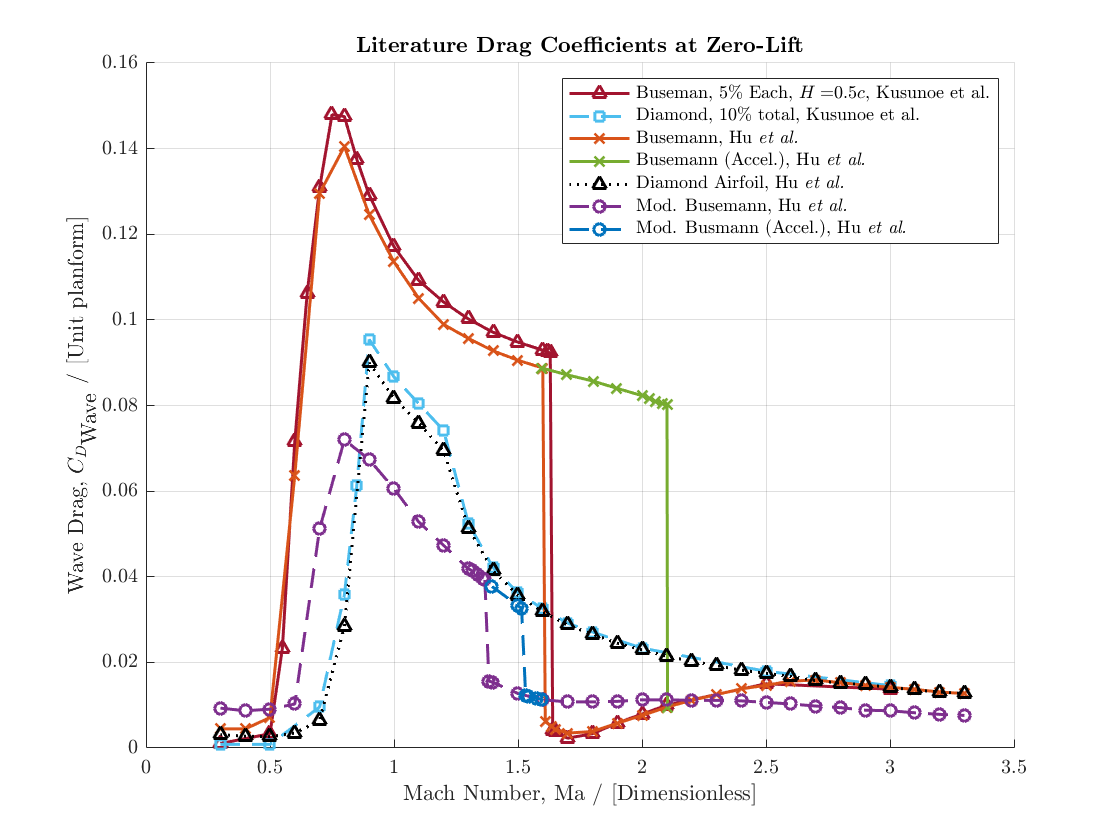


figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",1.5,'color',[0.6350 0.0780 0.1840])
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",1.5,'color',[0.3010 0.7450 0.9330])
hold on
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",1.5,'color',[0.8500 0.3250 0.0980])
hold on
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",1.5,'color',[0.4660 0.6740 0.1880])
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",1.5,'color',[0 0 0])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",1.5,'color',[0.4940 0.1840 0.5560])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",1.5,'color',[0 0.4470 0.7410])
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Literature Drag Coefficients at Zero-Lift}")
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.","Busemann, Hu \textit{et al.}","Busemann (Accel.), Hu \textit{et al.}","Diamond Airfoil, Hu \textit{et al.}","Mod. Busemann, Hu \textit{et al.}","Mod. Busmann (Accel.), Hu \textit{et al.}", "Location","northeast","NumColumns",1)
ylim([0 0.16])
box off
grid on
hold off

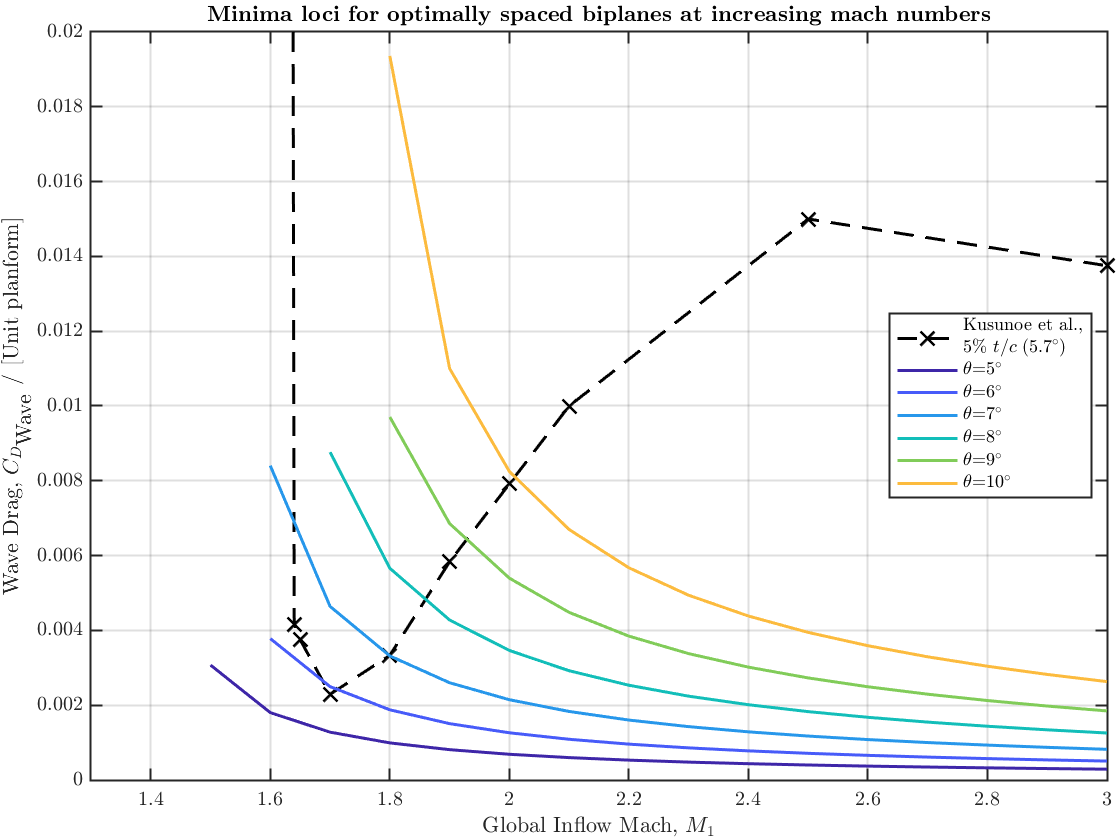


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Japanese point performance Drag Results: 
% Optimal Point
Jpn_Mach = 1.7;
Jpn_CDWave = Jpn_Busemann(22);

figure
plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",1.5,"MarkerSize",8)
%plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
hold on
for line = 1:length(theta1)
plot(M1,Cd(line,:),'Color',cmap(line,:),"LineWidth",1.5)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend([{['Kusunoe et al.,' newline '5\% $t/c$ (5.7$^{\circ}$)']},legendCelltheta],'location','east')
xlabel("Global Inflow Mach, $M_{1}$")
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]")
title("\textbf{Minima loci for optimally spaced biplanes at increasing mach numbers}")
ylim([0,0.02])
xlim([min(M1),max(M1)])
grid on; hold off; box on
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


Mimimium_Kusunose = Jpn_Busemann(22)

Mimimium_Kusunose = 0.0023

Theorietical_Optimal = Cd

Theorietical_Optimal =        NaN       NaN    0.0031    0.0018    0.0013    0.0010    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003
       NaN       NaN       NaN    0.0038    0.0025    0.0019    0.0015    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005
       NaN       NaN       NaN    0.0084    0.0046    0.0033    0.0026    0.0021    0.0018    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0009    0.0008
       NaN       NaN       NaN       NaN    0.0088    0.0057    0.0043    0.0035    0.0029    0.0025    0.0022    0.0020    0.0018    0.0017    0.0015    0.0014    0.0013    0.0013
       NaN       NaN       NaN       NaN       NaN    0.0097    0.0069    0.0054    0.0045    0.0038    0.0034    0.0030    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018
       NaN       NaN       NaN       NaN       NaN    0.0194    0.0110  


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Japanese Mach Range

function Area = Area_Ratio(M,gamma)
% This function returns the Area (expansion) Ratio required to expand a flow
% from the sonic line for a given Mach number (M) ratio of specific heats
% (gamma). This finds it uses in rocket nozzles hence we invert it
% elsewhere in the code.

a=0.5*(gamma+1);
b=(gamma+1)/(2*(gamma-1));
c=1+((0.5*(gamma-1))*M.^2);

Area = (a^-b).*((c.^b)./M);
end

function Mach = Inv_Area_Ratio(AreaRatio,gamma)
if isnan(AreaRatio) == true
    Mach = NaN;
else
% SUPERSONIC COLUTION METHOD YIELDED
% Based on Root Finding Methods by: JoshTheEngineer
% (www.joshtheengineer.com)
%  - Solve the Area-Mach Number equation for Mach number
g   = gamma;
gm1 = g-1;
gp1 = g+1;

% Define anonymous function with two inputs (M and ARatio)
% - Pass M and ARatio as arguments to AM_EQN to get function value
% -     funVal = AM_EQN(M,ARatio)
%AM_EQN = @(M,ARatio) sqrt((1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1)))-ARatio;

% Solve for Msub and Msup using this area ratio (A/A*)
ARatio = AreaRatio;

% Error tolerance
%errTol = 1e-4;

%% MATLAB SOLVER

% Set up the solver
problem.objective = @(M) (1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1))-ARatio^2;    % Objective function
problem.solver    = 'fzero';              % Find the zero
problem.options   = optimset(@fzero);     % Default options

% Solve subsonic root
problem.x0 = [1e-6 1];              % Subsonic solver bounds
Msub       = fzero(problem);        % Solve for subsonic M
problem.x0 = [1+1e-6 50];           % Supersonic solver bounds
Msup       = fzero(problem);        % Solve for supersonic M

% Print solutions to command window
% fprintf('==== MATLAB SOLVER ====\n');
% fprintf('Msub: %3.4f\n',Msub);
% fprintf('Msup: %3.4f\n',Msup);
% fprintf('=======================\n\n');
Mach = Msup;
end
end

function [x1,x2,H_exact,h_star_exact,A_ratio,beta1,beta2,M2,M3,theta2,phi1,phi2,Pr2,Pr3]=IdealSpacing(M1,theta1,chord,gamma)

% STEP 1
t = (chord*0.5)*tand(theta1);

% STEP 2
[beta1,M2,Pr2] = ObliqueShock(M1,theta1,gamma);
%[beta1,M2,Pr2,P0r2,rhor2,tr2,M1n,M2n] = ObliqueShock(M1,theta1,gamma);
phi1 = beta1-theta1;

% STEP 3
theta2=theta1;
[beta2,M3,Pr3] = ObliqueShock(M2,theta2,gamma);
%[beta2,M3,Pr3,P0r3,rhor3,Tr3,M2n,M3n] = ObliqueShock(M2,theta2,gamma);
phi2 = beta2-theta2;

% STEP 4
alpha = 180-beta2-phi1;

% STEP 5
L = sqrt( ((0.5*chord)^2) + (t^2) );
r = (L/sind(alpha)) * sind(beta2); %sine rule

% STEP 6
x1 = r*cosd(beta1);
x2 = (0.5*chord)-x1;
dy = r*sind(beta1);

% STEP 7
H_exact = 2*dy;
h_star_exact = H_exact-(2*t);
A_ratio = h_star_exact/H_exact;
end

function [beta,M2,Pr2,P0r2,rhor2,Tr2,M1n,M2n] = ObliqueShock(M1,theta,gamma)

% GIVEN upstream Mach M1, deflection angle theta and spec. heat ratio gamma
% Returns the down stream Mach number, M2 and it's Normal Component M2N
% and the vatious ratios of quantities based on oblique shock relations

n = 0; % This specifies we want the weak solution only - strong solutions are off condition
beta = getBeta(M1,theta,gamma,n);

a = 0.5*(gamma-1);
b = (M1^2)*((sind(beta))^2);
c = beta-theta;
% Mach Number
M2 =( 1/sind(c) ) * sqrt( (1+(a*b))/( (gamma*b) -a) );

% Pressure ratio p2/p1 
Pr2 = 1+(((2*gamma)/(gamma+1))*(b-1));

% Density ratio rho02/rho01
rhor2 =( (gamma+1)*b )/( ((gamma-1)*b) +2);

% Stagnation Pressure ratio p02/p01
P0r2 = (rhor2^(gamma/(gamma-1))) * ((1/Pr2)^(1/(gamma-1)));

% Temperature Ratio T2/T1
Tr2 = Pr2*(1/rhor2);

% Normal Mach Components
M1n = M1*sind(beta);
M2n = M2*sind(beta-theta);
end

function Beta=getBeta(M,theta,gamma,n)
% This function returns the oblique shock wave angle (beta) for a given
% deflection angle (theta) in degrees and ratio of specific heats (gamma).
% and Mach number M. Specify 0 for the weak oblique shock 
% or 1 for the strong shock.
%
% Syntax:
% beta(M,theta,gamma,n)     where n specifies weak or strong shock returned
% NOTE: Angles supplied and returned from this function are in DEGREES.
%
% Based on the 'Beta' function of Chris Plumley, University of Maryland.
% Originally written July-August, 1998, pp. 647-649.
% Based on an analytical solution to the theta-beta-Mach relation given in
% the following reference:  Rudd, L., and Lewis, M. J., "Comparison of
% Shock Calculation Methods", AIAA Journal of Aircraft, Vol. 35, No. 4,

theta=theta*pi/180;             % convert to radians
mu=asin(1/M);                   % Mach wave angle
c=tan(mu)^2;
a=((gamma-1)/2+(gamma+1)*c/2)*tan(theta);
b=((gamma+1)/2+(gamma+3)*c/2)*tan(theta);
d=sqrt(4*(1-3*a*b)^3/((27*a^2*c+9*a*b-2)^2)-1);

Beta=atan((b+9*a*c)/(2*(1-3*a*b))-(d*(27*a^2*c+9*a*b-2))/(6*a*(1-3*a*b))*tan(n*pi/3+1/3*atan(1/d)))*180/pi;

% Added non-weak solution conditions
if Beta<0 %i.e. subsonic conditions
    disp("No Solution - consider higher Mach Number")
    %return
    Beta = NaN;
end
if imag(Beta)~=0 %i.e. Strong Solution
    disp("No weak solution - consider a higher Mach or Lower Deflection Angle")
    %return
    Beta = NaN;
end
end

function v = PrandtlMeyer(M,gamma)
v = sqrt((gamma+1)/(gamma-1))*atan(sqrt(((gamma-1)/(gamma+1))*((M.^2)-1)))-atan(sqrt((M.^2)-1));
v = rad2deg(v);
end

function Mach=InvPrandtlMeyer(v)
%% Based on Hall, I. M. "Inversion of the prandtl-meyer relation." Aeronautical Journal 79 (1975): 417.
% As sampled: Shubham Maurya (2021). InvPrandtlMeyer(v) (https://www.mathworks.com/matlabcentral/fileexchange/56098-invprandtlmeyer-v), MATLAB Central File Exchange. Retrieved January 27, 2021.
v=v*pi/180;
A=1.3604;
B=0.0962;
C=-0.5127;
D=-0.6722;
E=-0.3278;
v_0=0.5*pi*(sqrt(6)-1);
y=(v./v_0).^(2/3);
Mach=(1 + A*y + B*y.^2 + C*y.^3)./(1 + D*y + E*y.^2);
end

function P2 = isentropicPr(M1,M2,P1,gamma)
% This function uses an isentropic temperature ratio to get the pressure
% rise across an isentropic (PM expansion)

a = 0.5*(gamma-1);

b = 1+(a*(M1.^2));
c = 1+(a*(M2.^2));

Tr = b./c;
Pr = Tr.^(gamma/(gamma-1));

P2 = Pr.*P1;

end

function cm_data=viridis(m)
cm = [[ 0.26700401,  0.00487433,  0.32941519],
       [ 0.26851048,  0.00960483,  0.33542652],
       [ 0.26994384,  0.01462494,  0.34137895],
       [ 0.27130489,  0.01994186,  0.34726862],
       [ 0.27259384,  0.02556309,  0.35309303],
       [ 0.27380934,  0.03149748,  0.35885256],
       [ 0.27495242,  0.03775181,  0.36454323],
       [ 0.27602238,  0.04416723,  0.37016418],
       [ 0.2770184 ,  0.05034437,  0.37571452],
       [ 0.27794143,  0.05632444,  0.38119074],
       [ 0.27879067,  0.06214536,  0.38659204],
       [ 0.2795655 ,  0.06783587,  0.39191723],
       [ 0.28026658,  0.07341724,  0.39716349],
       [ 0.28089358,  0.07890703,  0.40232944],
       [ 0.28144581,  0.0843197 ,  0.40741404],
       [ 0.28192358,  0.08966622,  0.41241521],
       [ 0.28232739,  0.09495545,  0.41733086],
       [ 0.28265633,  0.10019576,  0.42216032],
       [ 0.28291049,  0.10539345,  0.42690202],
       [ 0.28309095,  0.11055307,  0.43155375],
       [ 0.28319704,  0.11567966,  0.43611482],
       [ 0.28322882,  0.12077701,  0.44058404],
       [ 0.28318684,  0.12584799,  0.44496   ],
       [ 0.283072  ,  0.13089477,  0.44924127],
       [ 0.28288389,  0.13592005,  0.45342734],
       [ 0.28262297,  0.14092556,  0.45751726],
       [ 0.28229037,  0.14591233,  0.46150995],
       [ 0.28188676,  0.15088147,  0.46540474],
       [ 0.28141228,  0.15583425,  0.46920128],
       [ 0.28086773,  0.16077132,  0.47289909],
       [ 0.28025468,  0.16569272,  0.47649762],
       [ 0.27957399,  0.17059884,  0.47999675],
       [ 0.27882618,  0.1754902 ,  0.48339654],
       [ 0.27801236,  0.18036684,  0.48669702],
       [ 0.27713437,  0.18522836,  0.48989831],
       [ 0.27619376,  0.19007447,  0.49300074],
       [ 0.27519116,  0.1949054 ,  0.49600488],
       [ 0.27412802,  0.19972086,  0.49891131],
       [ 0.27300596,  0.20452049,  0.50172076],
       [ 0.27182812,  0.20930306,  0.50443413],
       [ 0.27059473,  0.21406899,  0.50705243],
       [ 0.26930756,  0.21881782,  0.50957678],
       [ 0.26796846,  0.22354911,  0.5120084 ],
       [ 0.26657984,  0.2282621 ,  0.5143487 ],
       [ 0.2651445 ,  0.23295593,  0.5165993 ],
       [ 0.2636632 ,  0.23763078,  0.51876163],
       [ 0.26213801,  0.24228619,  0.52083736],
       [ 0.26057103,  0.2469217 ,  0.52282822],
       [ 0.25896451,  0.25153685,  0.52473609],
       [ 0.25732244,  0.2561304 ,  0.52656332],
       [ 0.25564519,  0.26070284,  0.52831152],
       [ 0.25393498,  0.26525384,  0.52998273],
       [ 0.25219404,  0.26978306,  0.53157905],
       [ 0.25042462,  0.27429024,  0.53310261],
       [ 0.24862899,  0.27877509,  0.53455561],
       [ 0.2468114 ,  0.28323662,  0.53594093],
       [ 0.24497208,  0.28767547,  0.53726018],
       [ 0.24311324,  0.29209154,  0.53851561],
       [ 0.24123708,  0.29648471,  0.53970946],
       [ 0.23934575,  0.30085494,  0.54084398],
       [ 0.23744138,  0.30520222,  0.5419214 ],
       [ 0.23552606,  0.30952657,  0.54294396],
       [ 0.23360277,  0.31382773,  0.54391424],
       [ 0.2316735 ,  0.3181058 ,  0.54483444],
       [ 0.22973926,  0.32236127,  0.54570633],
       [ 0.22780192,  0.32659432,  0.546532  ],
       [ 0.2258633 ,  0.33080515,  0.54731353],
       [ 0.22392515,  0.334994  ,  0.54805291],
       [ 0.22198915,  0.33916114,  0.54875211],
       [ 0.22005691,  0.34330688,  0.54941304],
       [ 0.21812995,  0.34743154,  0.55003755],
       [ 0.21620971,  0.35153548,  0.55062743],
       [ 0.21429757,  0.35561907,  0.5511844 ],
       [ 0.21239477,  0.35968273,  0.55171011],
       [ 0.2105031 ,  0.36372671,  0.55220646],
       [ 0.20862342,  0.36775151,  0.55267486],
       [ 0.20675628,  0.37175775,  0.55311653],
       [ 0.20490257,  0.37574589,  0.55353282],
       [ 0.20306309,  0.37971644,  0.55392505],
       [ 0.20123854,  0.38366989,  0.55429441],
       [ 0.1994295 ,  0.38760678,  0.55464205],
       [ 0.1976365 ,  0.39152762,  0.55496905],
       [ 0.19585993,  0.39543297,  0.55527637],
       [ 0.19410009,  0.39932336,  0.55556494],
       [ 0.19235719,  0.40319934,  0.55583559],
       [ 0.19063135,  0.40706148,  0.55608907],
       [ 0.18892259,  0.41091033,  0.55632606],
       [ 0.18723083,  0.41474645,  0.55654717],
       [ 0.18555593,  0.4185704 ,  0.55675292],
       [ 0.18389763,  0.42238275,  0.55694377],
       [ 0.18225561,  0.42618405,  0.5571201 ],
       [ 0.18062949,  0.42997486,  0.55728221],
       [ 0.17901879,  0.43375572,  0.55743035],
       [ 0.17742298,  0.4375272 ,  0.55756466],
       [ 0.17584148,  0.44128981,  0.55768526],
       [ 0.17427363,  0.4450441 ,  0.55779216],
       [ 0.17271876,  0.4487906 ,  0.55788532],
       [ 0.17117615,  0.4525298 ,  0.55796464],
       [ 0.16964573,  0.45626209,  0.55803034],
       [ 0.16812641,  0.45998802,  0.55808199],
       [ 0.1666171 ,  0.46370813,  0.55811913],
       [ 0.16511703,  0.4674229 ,  0.55814141],
       [ 0.16362543,  0.47113278,  0.55814842],
       [ 0.16214155,  0.47483821,  0.55813967],
       [ 0.16066467,  0.47853961,  0.55811466],
       [ 0.15919413,  0.4822374 ,  0.5580728 ],
       [ 0.15772933,  0.48593197,  0.55801347],
       [ 0.15626973,  0.4896237 ,  0.557936  ],
       [ 0.15481488,  0.49331293,  0.55783967],
       [ 0.15336445,  0.49700003,  0.55772371],
       [ 0.1519182 ,  0.50068529,  0.55758733],
       [ 0.15047605,  0.50436904,  0.55742968],
       [ 0.14903918,  0.50805136,  0.5572505 ],
       [ 0.14760731,  0.51173263,  0.55704861],
       [ 0.14618026,  0.51541316,  0.55682271],
       [ 0.14475863,  0.51909319,  0.55657181],
       [ 0.14334327,  0.52277292,  0.55629491],
       [ 0.14193527,  0.52645254,  0.55599097],
       [ 0.14053599,  0.53013219,  0.55565893],
       [ 0.13914708,  0.53381201,  0.55529773],
       [ 0.13777048,  0.53749213,  0.55490625],
       [ 0.1364085 ,  0.54117264,  0.55448339],
       [ 0.13506561,  0.54485335,  0.55402906],
       [ 0.13374299,  0.54853458,  0.55354108],
       [ 0.13244401,  0.55221637,  0.55301828],
       [ 0.13117249,  0.55589872,  0.55245948],
       [ 0.1299327 ,  0.55958162,  0.55186354],
       [ 0.12872938,  0.56326503,  0.55122927],
       [ 0.12756771,  0.56694891,  0.55055551],
       [ 0.12645338,  0.57063316,  0.5498411 ],
       [ 0.12539383,  0.57431754,  0.54908564],
       [ 0.12439474,  0.57800205,  0.5482874 ],
       [ 0.12346281,  0.58168661,  0.54744498],
       [ 0.12260562,  0.58537105,  0.54655722],
       [ 0.12183122,  0.58905521,  0.54562298],
       [ 0.12114807,  0.59273889,  0.54464114],
       [ 0.12056501,  0.59642187,  0.54361058],
       [ 0.12009154,  0.60010387,  0.54253043],
       [ 0.11973756,  0.60378459,  0.54139999],
       [ 0.11951163,  0.60746388,  0.54021751],
       [ 0.11942341,  0.61114146,  0.53898192],
       [ 0.11948255,  0.61481702,  0.53769219],
       [ 0.11969858,  0.61849025,  0.53634733],
       [ 0.12008079,  0.62216081,  0.53494633],
       [ 0.12063824,  0.62582833,  0.53348834],
       [ 0.12137972,  0.62949242,  0.53197275],
       [ 0.12231244,  0.63315277,  0.53039808],
       [ 0.12344358,  0.63680899,  0.52876343],
       [ 0.12477953,  0.64046069,  0.52706792],
       [ 0.12632581,  0.64410744,  0.52531069],
       [ 0.12808703,  0.64774881,  0.52349092],
       [ 0.13006688,  0.65138436,  0.52160791],
       [ 0.13226797,  0.65501363,  0.51966086],
       [ 0.13469183,  0.65863619,  0.5176488 ],
       [ 0.13733921,  0.66225157,  0.51557101],
       [ 0.14020991,  0.66585927,  0.5134268 ],
       [ 0.14330291,  0.66945881,  0.51121549],
       [ 0.1466164 ,  0.67304968,  0.50893644],
       [ 0.15014782,  0.67663139,  0.5065889 ],
       [ 0.15389405,  0.68020343,  0.50417217],
       [ 0.15785146,  0.68376525,  0.50168574],
       [ 0.16201598,  0.68731632,  0.49912906],
       [ 0.1663832 ,  0.69085611,  0.49650163],
       [ 0.1709484 ,  0.69438405,  0.49380294],
       [ 0.17570671,  0.6978996 ,  0.49103252],
       [ 0.18065314,  0.70140222,  0.48818938],
       [ 0.18578266,  0.70489133,  0.48527326],
       [ 0.19109018,  0.70836635,  0.48228395],
       [ 0.19657063,  0.71182668,  0.47922108],
       [ 0.20221902,  0.71527175,  0.47608431],
       [ 0.20803045,  0.71870095,  0.4728733 ],
       [ 0.21400015,  0.72211371,  0.46958774],
       [ 0.22012381,  0.72550945,  0.46622638],
       [ 0.2263969 ,  0.72888753,  0.46278934],
       [ 0.23281498,  0.73224735,  0.45927675],
       [ 0.2393739 ,  0.73558828,  0.45568838],
       [ 0.24606968,  0.73890972,  0.45202405],
       [ 0.25289851,  0.74221104,  0.44828355],
       [ 0.25985676,  0.74549162,  0.44446673],
       [ 0.26694127,  0.74875084,  0.44057284],
       [ 0.27414922,  0.75198807,  0.4366009 ],
       [ 0.28147681,  0.75520266,  0.43255207],
       [ 0.28892102,  0.75839399,  0.42842626],
       [ 0.29647899,  0.76156142,  0.42422341],
       [ 0.30414796,  0.76470433,  0.41994346],
       [ 0.31192534,  0.76782207,  0.41558638],
       [ 0.3198086 ,  0.77091403,  0.41115215],
       [ 0.3277958 ,  0.77397953,  0.40664011],
       [ 0.33588539,  0.7770179 ,  0.40204917],
       [ 0.34407411,  0.78002855,  0.39738103],
       [ 0.35235985,  0.78301086,  0.39263579],
       [ 0.36074053,  0.78596419,  0.38781353],
       [ 0.3692142 ,  0.78888793,  0.38291438],
       [ 0.37777892,  0.79178146,  0.3779385 ],
       [ 0.38643282,  0.79464415,  0.37288606],
       [ 0.39517408,  0.79747541,  0.36775726],
       [ 0.40400101,  0.80027461,  0.36255223],
       [ 0.4129135 ,  0.80304099,  0.35726893],
       [ 0.42190813,  0.80577412,  0.35191009],
       [ 0.43098317,  0.80847343,  0.34647607],
       [ 0.44013691,  0.81113836,  0.3409673 ],
       [ 0.44936763,  0.81376835,  0.33538426],
       [ 0.45867362,  0.81636288,  0.32972749],
       [ 0.46805314,  0.81892143,  0.32399761],
       [ 0.47750446,  0.82144351,  0.31819529],
       [ 0.4870258 ,  0.82392862,  0.31232133],
       [ 0.49661536,  0.82637633,  0.30637661],
       [ 0.5062713 ,  0.82878621,  0.30036211],
       [ 0.51599182,  0.83115784,  0.29427888],
       [ 0.52577622,  0.83349064,  0.2881265 ],
       [ 0.5356211 ,  0.83578452,  0.28190832],
       [ 0.5455244 ,  0.83803918,  0.27562602],
       [ 0.55548397,  0.84025437,  0.26928147],
       [ 0.5654976 ,  0.8424299 ,  0.26287683],
       [ 0.57556297,  0.84456561,  0.25641457],
       [ 0.58567772,  0.84666139,  0.24989748],
       [ 0.59583934,  0.84871722,  0.24332878],
       [ 0.60604528,  0.8507331 ,  0.23671214],
       [ 0.61629283,  0.85270912,  0.23005179],
       [ 0.62657923,  0.85464543,  0.22335258],
       [ 0.63690157,  0.85654226,  0.21662012],
       [ 0.64725685,  0.85839991,  0.20986086],
       [ 0.65764197,  0.86021878,  0.20308229],
       [ 0.66805369,  0.86199932,  0.19629307],
       [ 0.67848868,  0.86374211,  0.18950326],
       [ 0.68894351,  0.86544779,  0.18272455],
       [ 0.69941463,  0.86711711,  0.17597055],
       [ 0.70989842,  0.86875092,  0.16925712],
       [ 0.72039115,  0.87035015,  0.16260273],
       [ 0.73088902,  0.87191584,  0.15602894],
       [ 0.74138803,  0.87344918,  0.14956101],
       [ 0.75188414,  0.87495143,  0.14322828],
       [ 0.76237342,  0.87642392,  0.13706449],
       [ 0.77285183,  0.87786808,  0.13110864],
       [ 0.78331535,  0.87928545,  0.12540538],
       [ 0.79375994,  0.88067763,  0.12000532],
       [ 0.80418159,  0.88204632,  0.11496505],
       [ 0.81457634,  0.88339329,  0.11034678],
       [ 0.82494028,  0.88472036,  0.10621724],
       [ 0.83526959,  0.88602943,  0.1026459 ],
       [ 0.84556056,  0.88732243,  0.09970219],
       [ 0.8558096 ,  0.88860134,  0.09745186],
       [ 0.86601325,  0.88986815,  0.09595277],
       [ 0.87616824,  0.89112487,  0.09525046],
       [ 0.88627146,  0.89237353,  0.09537439],
       [ 0.89632002,  0.89361614,  0.09633538],
       [ 0.90631121,  0.89485467,  0.09812496],
       [ 0.91624212,  0.89609127,  0.1007168 ],
       [ 0.92610579,  0.89732977,  0.10407067],
       [ 0.93590444,  0.8985704 ,  0.10813094],
       [ 0.94563626,  0.899815  ,  0.11283773],
       [ 0.95529972,  0.90106534,  0.11812832],
       [ 0.96489353,  0.90232311,  0.12394051],
       [ 0.97441665,  0.90358991,  0.13021494],
       [ 0.98386829,  0.90486726,  0.13689671],
       [ 0.99324789,  0.90615657,  0.1439362 ]];
if nargin < 1
    cm_data = cm;
else
    hsv=rgb2hsv(cm);
    cm_data=interp1(linspace(0,1,size(cm,1)),hsv,linspace(0,1,m));
    cm_data=hsv2rgb(cm_data);
  
end
end

function y = cosspace(d1, d2, n, factor)
%COSSPACE cosine spaced vector.
%   COSSPACE(X1, X2) generates a row vector of 100 cosine spaced points
%   between X1 and X2. 
%
%   COSSPACE(X1, X2, N) generates N points between X1 and X2.
% 
%   A cosine spaced vector clusters the elements toward the endpoints:
%    X1    || |  |   |    |     |     |    |   |  | ||   X2
% 
%   For negative n, COSSPACE returns an inverse cosine spaced vector with
%   elements sparse toward the endpoints:
%     X1 |     |    |   |  | | | | | |  |   |    |     | X2
% 
%   For -2 < N < 2, COSSPACE returns X2.
% 
%   COSSPACE(X1, X2, N, W) clusters the elements to a lesser degree as
%   dictated by W. W = 0 returns a normal cosine or arccosine spaced
%   vector. W = 1 is the same as LINSPACE(X1, X2, N). Experiment with W < 0
%   and W > 1 for different clustering patterns.
% 
%   Author:     Sky Sartorius
%
%   See also SINSPACE, LINSPACE, LOGSPACE.
if nargin == 2
    n = 100;
end
if nargin < 4
    factor = false;
end
if n<0
    n = floor(double(-n));
    y = d1 + (d2-d1)/pi*acos(1-2*(0:(n-1))/(n-1));
else
    n = floor(double(n));
    y = d1 + (d2-d1)/2*(1-cos(pi/(n-1)*(0:n-1)));
end
if factor
    y = (1-factor)*y+factor*[d1+(0:n-2)*(d2-d1)/(n-1) d2];
end
end

function c = redblue(m)
%REDBLUE    Shades of red and blue color map
%   REDBLUE(M), is an M-by-3 matrix that defines a colormap.
%   The colors begin with bright blue, range through shades of
%   blue to white, and then through shades of red to bright red.
%   REDBLUE, by itself, is the same length as the current figure's
%   colormap. If no figure exists, MATLAB creates one.
%
%   For example, to reset the colormap of the current figure:
%
%             colormap(redblue)
%
%   See also HSV, GRAY, HOT, BONE, COPPER, PINK, FLAG, 
%   COLORMAP, RGBPLOT.
%   Adam Auton, 9th October 2009
if nargin < 1, m = size(get(gcf,'colormap'),1); end
if (mod(m,2) == 0)
    % From [0 0 1] to [1 1 1], then [1 1 1] to [1 0 0];
    m1 = m*0.5;
    r = (0:m1-1)'/max(m1-1,1);
    g = r;
    r = [r; ones(m1,1)];
    g = [g; flipud(g)];
    b = flipud(r);
else
    % From [0 0 1] to [1 1 1] to [1 0 0];
    m1 = floor(m*0.5);
    r = (0:m1-1)'/max(m1,1);
    g = r;
    r = [r; ones(m1+1,1)];
    g = [g; 1; flipud(g)];
    b = flipud(r);
end
c = [r g b]; 
end

function newmap = bluewhitered(m)
%BLUEWHITERED   Blue, white, and red color map.
%   BLUEWHITERED(M) returns an M-by-3 matrix containing a blue to white
%   to red colormap, with white corresponding to the CAXIS value closest
%   to zero.  This colormap is most useful for images and surface plots
%   with positive and negative values.  BLUEWHITERED, by itself, is the
%   same length as the current colormap.
%
%   Examples:
%   ------------------------------
%   figure
%   imagesc(peaks(250));
%   colormap(bluewhitered(256)), colorbar
%
%   figure
%   imagesc(peaks(250), [0 8])
%   colormap(bluewhitered), colorbar
%
%   figure
%   imagesc(peaks(250), [-6 0])
%   colormap(bluewhitered), colorbar
%
%   figure
%   surf(peaks)
%   colormap(bluewhitered)
%   axis tight
%
%   See also HSV, HOT, COOL, BONE, COPPER, PINK, FLAG, 
%   COLORMAP, RGBPLOT.
if nargin < 1
   m = size(get(gcf,'colormap'),1);
end
bottom = [0 0 0.5];
botmiddle = [0 0.5 1];
middle = [1 1 1];
topmiddle = [1 0 0];
top = [0.5 0 0];
% Find middle
lims = get(gca, 'CLim');
% Find ratio of negative to positive
if (lims(1) < 0) & (lims(2) > 0)
    % It has both negative and positive
    % Find ratio of negative to positive
    ratio = abs(lims(1)) / (abs(lims(1)) + lims(2));
    neglen = round(m*ratio);
    poslen = m - neglen;
    
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, neglen);
    newmap1 = zeros(neglen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap1(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, poslen);
    newmap = zeros(poslen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % And put 'em together
    newmap = [newmap1; newmap];
    
elseif lims(1) >= 0
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
else
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
end
% 
% m = 64;
% new = [bottom; botmiddle; middle; topmiddle; top];
% % x = 1:m;
% 
% oldsteps = linspace(0, 1, 5);
% newsteps = linspace(0, 1, m);
% newmap = zeros(m, 3);
% 
% for i=1:3
%     % Interpolate over RGB spaces of colormap
%     newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
% end
% 
% % set(gcf, 'colormap', newmap), colorbar
end

function [h, ext] = labelpoints (xpos, ypos, labels, varargin)
%  [h, ext] = labelpoints (xpos, ypos, labels, position, buffer, adjust_axes, varargin)
%
%   Given x and y coordinate vectors (xpos, ypos) and given
%     a vector of labels this function will label all data points
%     and output the label handles in vector, h and the label extents in ext.
%
% ***REQUIRED INPUTS (the basics)***************
%
%   'xpos' and 'ypos' are x and y coordinate vectors for your labels.  xpos & ypos
%     should be the same length.  An exception is when all labels are along the same
%     x or y coordinate.  In that case only one value is needed for that x or y coordinate
%     and it will be replicated in the code.
%     (see examples directly below).
%
%   'labels' should be a 1xN or Nx1 array of strings or numbers of the same length as xpos or ypos.
%     Alternatively it can be a single string or number that will be replicated
%     for each (x,y) coordinate.   (see examples directly below.).
%     Alternatively it can be an NxM cell array of strings and/or numbers where the columns of each
%     row will be joined with a space delimiter to create 1 label per row (see examples directly below).
%
%   Example:
%         x = [0 .1 .2]; y = [.8 .7 .6];
%         labels = {'label 1' 'label 2' 'label 3'};
%         plot(x, y, 'o'); axis([-1 1 0 1]);
%         labelpoints(x, y, labels);
%
%   Example: when all labels fall along the same X value
%         boxplot(1:10)
%         labelpoints(0.8, [3, 5.5, 8], {'25%' '50%' '75%'}, 'center');
%
%   Example: When using only 1 label that is replicated
%         x = [0 .1 .2]; y = [.8 .6 .4];
%         plot(x,y,'o'); axis([-1 1 -1 1])
%         labelpoints(x, y, 'this point')
%
%   Example: When using a 2D cell arry for labels
%        labels = {'a', 'b', 'c'; 1, 2, 3};
%        labelpoints(0.5, 0.5, labels, 'stacked', 'down'); %see options below for 'stacked' input.
%
% *** OPTIONAL INPUTS **************************
%
%   'position' (optional) describes the position of the labels relative to their
%     (x,y) location by entering one of the following abbreviated compass directions
%     in single quotes (default is 'NW'):   N, S, E, W, NE, NW, SE, SW, center, C
%
%   'buffer' (optional) is a number generally between 0:1 that adds distance between
%     the label and the plotted point where 0 (default) is 0 distance and 1 is 1/10th
%     of the axis length.  Ignored for 'center' position.  The value can be greater than
%     1 or less than 0 too where negative buffer will shift in the opposite direction.
%
%   'adjust_axes' (optional, default=0): depending on the positioning of labels,
%     some may fall beyond the axis limits. adjust_axes = 1 will re-adjust xlim
%     & ylim slightly so labels are not beyond axis limits.
%
%   Examples:
%         x = [0 0 0]; y = [.8 .7 .6];
%         labels = {'label 1' 'label 2' 'label 3'};
%         plot(x, y, 'o')
%         labelpoints(x, y, labels, 'SE', 0.5, 1);
%
% *** OPTIONAL PARAMETERS **************************
%   The following parameters may also be entered in any order
%   * 'FontSize', N -   font size of all labels
%   * 'FontWeight', S - font weight 'bold' or 'normal'
%   * 'interpreter', s - set the text interpreter (default is 'none')
%   * 'Color', S    -   font color of all labels ('y' 'm' 'c' 'r' 'g' 'b' 'w' 'k') or RGB vector [x x x]
%                       Multiple colors may be entered as rows of RGB vector and your pattern will be replicated
%                       to match the length of your lables. See example.
%   * 'BackgroundColor', S - RGB triplet or character vector of color name for text background.
%   * 'rotation', N -   will rotate the labels N degrees and will place center of label according to 'position' input.
%                       (positive is counterclockwise). You might slightly increase buffer for rotated text.
%       Example:
%         x = [4 8 19 5 3]; bar(x);
%         labelpoints(1:5, x, {'dog' 'cat' 'bee' 'frog' 'ant'}, 'N', 0.7, 1, 'FontSize', 14, 'Color', 'm', 'rotation', 45)
%       Example with Multiple Colors
%         labelpoints(1:5, x, {'dog' 'cat' 'bee' 'frog' 'ant'}, 'N', 0.7, 1, 'color', [0 0 0; 1 0 0; 0 0 1]);
%
%   'stacked' (optional): Automatically stacks multiple labels vertically or horizontally. 
%       When using 'stacked' only the first xpos and ypos coordinate will be used to plot 
%       the 1st label and the following coordinates will be determined by the desired stack type.  
%       Stack types include:
%       * 'down' - stacks vertically, downward. xpos and ypos indicate position of top most label. (default)
%       * 'up'   - stacks vertically, upward.  xpos and ypos indicate position of bottom label.
%       * 'right'- stacks horizontally, rightward.  xpos and ypos indicate pos of left most label.
%       * 'left' - stacks horizontally, leftward. xpos and ypos indicate pos of right most label.
%       You can also adjust the spacing between the labels like this:
%       * 'down_1.5' increases the inter-label distance by x1.5(default is 1)
%       * 'left_0.5' decreases the inter-label distance by x0.5
%       Values >1 increase the distances, values between 0:1 cause labels to overlap.
%       Note that 'position', 'buffer', 'FontSize', and 'rotation' inputs still affect all labels.
%       You cannot use any outliers when using 'stacked'. 
%
%       Examples:
%         bar([0 4 8 19 5 3])
%         labelpoints(0.5, 14, {'a','b','c','d','e','f','g'}, 'stacked', 'down');
%         labelpoints(0.3, 19, {'A','B','C','D','E','F','G'}, 'stacked', 'right_2.8')
%         labelpoints(max(xlim), min(ylim), {'A','B','C','D','E','F','G'}, 'stacked', 'up')
%
%   'outliers...'
%       This function includes optional parameters to identify and label only the outliers.
%       This can come in handy when you want to avoid cluttered labels or only want to see outlier labels.  
%       NaNs values will be ignored. There are several ways to identify outliers: (may require stats toolbox)
%       'outliers_SD', N   -  will only label points that are greater than N standard deviations from
%                             mean(xpos) or mean(ypos). Alternatively, label N standard deviations from
%                             any (X,Y) point by making N a 3-element vector [N standard dev, X, Y].
%                           * Example:
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               labelpoints(x,y,1:200,'outliers_SD', 2);
%                           * Example:
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               labelpoints(x,y,1:200,'outliers_SD',[2,10,-20]);
%       'outliers_Q', N    -  will only label points that are greater than N times the interquartile range
%                             of xpos or ypos.
%                           * Example:
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               labelpoints(x,y,1:200,'outliers_Q', 1);
%       'outliers_N', N    -  will calculate the distance of each point from the mean point(xpos,ypos)
%                             and will label the N-furthest points. Alternatively, N can be a decimal
%                             to label N% of the points. Alternatively, label the N (or 0.N) furthest
%                             points from any (X,Y) point by making N a 3-element vector [N, X, Y];
%                           * Example: (label 20 furthest points)
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               h = labelpoints(x,y,1:200,'outliers_N', 20);
%                           * Example:  (label 20% furthest points)
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               labelpoints(x,y,1:200,'outliers_N', 0.2);
%                           * Example:  (labels 5 furthest points from (10, -10))
%                               x = normrnd(0, 10, 1, 200); y=normrnd(0, 10, 1, 200); plot(x,y,'o');
%                               labelpoints(x,y,1:200,'outliers_N', [5,10,-10]);
%       'outliers_lim', {[x1 x2; y1 y2]; tag}
%                          -  labels points that are greater and less than the x and/or y value ranges.
%                             [x1 x2; y1 y2] are ranges of x and y values describing a boundary where points
%                             should or should not be labeled.
%                             'tag' can be either 'and', 'or', or 'invert'. (described below).
%                             When 'tag' is 'and', only points outside of x *and* y boundaries are labeled.
%                             When 'tag' is 'or' (default), points that are outside of the x *or* y boundaries
%                             are labeled.  (see examples for clarity).
%                             When 'tag' is 'invert', only points that fall *within* the x and y boundary are labeled.
%                             Use inf or -inf in the x1,x2,y1,y2 values to have a limitless bound.
%                           * Example: ('and')
%                               x = normrnd(0, 10, 1, 100); y=normrnd(0, 10, 1, 100); plot(x,y,'o');
%                               labelpoints(x,y,1:100,'outliers_lim', {[-5, 5; -10, 0]; 'and'}); hold on;
%                               line([-5, -5; 5, 5; min(xlim) max(xlim); min(xlim) max(xlim)]', [min(ylim) max(ylim); min(ylim) max(ylim); -10 -10; 0 0]', 'color', 'r')
%                           * Example: ('or')
%                               (change 'and' to 'or' in the example above)
%                           * Example: ('invert')
%                               (change 'and' to 'invert' in the example above)
%       'outliers_lin', {slope, Y-int, type, num}
%                          -  label points that have high residual values according to a linear
%                             fit of the data.  'Slope' & 'Y-int' are the slope and y intercept of the
%                             line that is being compared to the data.  The 'Slope' and 'Y-int' can be
%                             left out or empty and the regression line will be calculated based on the
%                             data points. Example:  {'sd', 1.5} or {'','','N',0.3}
%                             'TYPE' describes the type of outliers to be detected. When TYPE is 'SD',
%                             'NUM' standard deviations of the y value along the regression line will be labeled
%                             Example:  {1,0,'SD',2}. When 'TYPE' is 'N', if NUM<1, NUM% of the greatest residuals
%                             will be labeled.  If NUM>1 the NUM greatest residuals will be labeled.
%                             Examples: {1,0,'N', 10} or {1,0,'N',0.25}
%                           * Examples:
%                               x=[0:0.01:1]; y=[0:0.01:1]+rand(1,101); labs=[1:101];plot(x,y, 'o');
%                               labelpoints(x,y,labs,'outliers_lin',{'sd', 1.5});
%                               labelpoints(x,y,labs,'outliers_lin',{1,0,'sd',1.5});
%                               labelpoints(x,y,labs,'outliers_lin',{'N', 3});
%       'outliers_rand, N  -  will select N random points (no necessarily outliers) to label when N is a positive
%                             intiger or will select N% random points to label when N is a decimal (ie, 0.4 labels 40%).
%
%   To change text parameters post-hoc, use the output which is a vector of handles for all text elements.
%     Example:  h=labelpoints(....);  set(h, 'interpreter', 'latex');
%   If labelpoints is not writing to the desired axes, make the axes current before labeling using axes(axis-handle).
%   To reposition labels, use the arrow pointer in the plot window, select the label(s) and reposition.
%
%   For more examples, see additional comments within the code.  
%
%  140331 v.1
%  141115 v.2
%  151230 v.3
%  171012 v.4
%  171026 v4.1
% Copyright (c) 2014, Adam Danz  adam.danz@gmail.com
%All rights reserved
% source: http://www.mathworks.com/matlabcentral/fileexchange/46891-labelpoints
% *** MORE EXAMPLES *********************************
%
%      %Make Fake Data:
%       x = 1:10;  y=rand(1,10);
%       scatter(x,y)
%       labs = {'a' 'b' 'c' 'd' 'middle' 'f' 'g' 'h' 'i' 'last'};
%
%      Label Examples
%       txt_h = labelpoints(x, y, labs);                   %Required inputs
%       txt_h = labelpoints(x, y, labs, 'E', 0.15);        %Specify location of label relative to point
%       txt_h = labelpoints(x, y, labs, 'E', 0.15, 1);     %Expand axes if labels extend beyond axes
%       txt_h = labelpoints(x, y, labs, 'W', 0.15, 1, 'FontSize', 14, 'Color', 'r');            %Change font size and color
%       txt_h = labelpoints(x, y, labs, 'W', 0.4, 1, 'FontSize', 12, 'Color', [0 .5 .1], 'rotation', 45);  %Rotate data label
%       txt_h = labelpoints(min(xlim), max(ylim), labs, 'SE', .18, 'stacked', 'down');          %Stack data labels downward
%       txt_h = labelpoints(max(xlim), min(ylim), 1:10, 'NW', .18, 'stacked', 'left_2.5');      %Stack data labels leftward with 2.5 spacing.
%
%      Also try these labels:
%       labs = [1:1:10];
%       labs = {'Sofia' '' '' '' 'Bucharest' '' '' 'Belgrade' '' 'Ankara'}
%       labs = '*';
%       labs = 'any string';
%
%      More Outlier Examples
%       Generate Fake Data:
%            x = [rand(1,30), rand(1,8)*2];
%            y = [rand(1,30), rand(1,8)*2];
%            scatter(x, y)
%            labs = 1:38;
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_N', 5);                  %will label 5 furthest points from mean(x,y)
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_N', 0.1, 'Color', 'r');  %will label 10% of furthest points from mean
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_N', [8,1,0.25]);         %will label 8 furthest points from (1, 0.25)
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_SD', 2);                 %will label all points > 2 SD from mean
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_SD', [2,1,0.25]);        %will label all points > 2 SD from (1, 0.25)
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_Q', 1.5);                %will label points greater that 1.5 x IQR
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_lim', [0 1])             %will label points where x<0 or x>1 or y<0 or y>1
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_lim', [-inf 1; -inf 0.5])  %...where x>1 or y>0.5
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_lim', {[.4 1.2; 0.2 0.6]; 'and'}) %...where x<.4 or >1.2 AND y<0.2 or y>0.6
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_lim', {[.4 1.2; 0.2 0.6]; 'invert'}) %...where x>.4 or <1.2 AND y>0.2 or y<0.6
%        labelpoints(x, y, labs, 'N', 0.1, 1, 'outliers_lim', {[-inf inf; -inf 0.6]}) %Labels any Y value greater than 0.6
%        labelpoints(x, y, labs, 'N', 'outliers_lin', {'sd',1})                  %will label all outliers that are 1sd from regression line  NOTE: MY FAKE DATA IS NOT LINEAR!
%        labelpoints(x, y, labs, 'N', 'outliers_lin', {1,0,'sd',1})              %will label all outliers that are 1sd from unity line (y=x)
%        labelpoints(x, y, labs, 'N', 'outliers_lin', {0,0.5,'N',5})             %will label the top 5 values furthest from y=0.5
%
%   Alternative use:
%     Density Distributions:
%       x = randn(1,100); y = 1:100;
%       scatter(x,y)
%       labs = '|';
%       txt_h = labelpoints(x, 8, labs, 'center');
%
%     Single Labeling
%       x = 2004:2013;  y=rand(1,10);
%       plot(x,y,'-o')
%       labs = 'acquisition';
%       labelpoints(x(3), y(3), labs, 'N', 0.2, 1);
%       labelpoints(2008.5, min(ylim), {['labelpoints.m   ', datestr(now, 'mm/dd/yy')]}, 'N', 0.3, 0, 'fontsize', 12, 'color', 'm');
%
%     Use labels instead of markers
%       x = randn(1,15); y = randn(1,15);
%       labs = char('a'+(1:15)-1)';
%       labelpoints(x, y, labs, 'center', 0, 1, 'color', 'b');
%
%     Place notes on your plot
%       x = randn(1,100); y = 1:100;
%       scatter(x,y); xlim([-6,4])
%       labelpoints(-6, 100, {date, 'New York', '8-day span', 'p<0.001', ' ', 'This is easy'}, 'SE', 0.3, 'stacked', 'down')
%
% Changes history
%   11/02/14    if labels are entered as char, they are convered to cell
%   11/03/14    varargin added to accomodate auto_outlier feature
%   11/03/14    convert inputs to row vector if they are column vectors
%   11/04/14    now position in put is not case sensitive
%   11/04/14    now 1 label can be entered to label multiple points
%   11/04/14    now fontsize and color can be specified by params
%   11/05/14    changed 'outlier' to 'outlier_SD' and added 'outlier_Q'
%   11/07/14    added option to rotate test
%   11/15/14    added 'outliers_N' input option and cleaned up text rotation section.
%   11/19/14    curr_extent is not always a cell.  fixed.
%   11/20/14    when outliers_N is selected N is min(N, lenght(xpos));
%   11/21/14    removes entire point and label when there is an 'inf' value
%   12/14/14    fixed 'curr_extent' in rotation section
%   08/22/15    edited help file (buffer can be <>0/1)
%   09/01/15    commented-out warning that there are no outlier to label.
%   09/13/15    added outliers_lim option & set interpreter to none.
%   09/19/15    added ext output
%   09/20/15    removed validity check for color and allow 3-el vectors now.
%   10/09/15    added if nargout > 0.  !! Changed outlier section to deal with NaNs.
%               The code performs stats (ie, nanmedian, nanstd) on all data but when chosing labels,
%               only considers xpos ypos pairs that do not have NaN. See pairIDX.
%               changed text rotation to always center and added 'factor' section.
%   10/28/15    Changed outlier section from if/then to switch case. Added outlier_lin section!
%   12/21/15    Added 'stacked' input option - major addition, no change to previous functionality.
%   12/30/15    adjustments to help section; combined 2 sections at beginning that deal with text rotation.
%               *Changed medians to means in outlier section.
%               *Added more flexibility to some outlier inputs so user can identify their own center.
%               *added option to use "c" instead of "center" for position.
%               uploaded vs.3 to matlab central
%   02/02/16    Added 'if nlabs>1 ' to deal with text stacks of 1.
%   04/01/16    Improved examples and instructions.  Tested with matlab 2016.
%   09/11/16    Added interpreter as param.
%   10/22/16    added axHand and added auto_offset option. 
%   12/12/16    added fontweight
%   12/15/16    added warning when xscale or yscale is not linear and buffer is not 0. added 'buf'.
%   01/12/17    added ability to enter cell MxN cell arrays for stacked text which joins the cols of the array.
%   01/15/17    added outlier type outlier_rand.
%   01/19/17    allowed for multiple colors.
%   08/14/17    added BackgroundColor param.
% 	08/31/17    added axHand param.
%   10/12/17    adapted code to work with datetime axes. Cleaned up some code and comments.  
%   10/26/17    replaced use of isdatetime() with isa()
%% Input validity
% Check Class of 'labels'
%If 'labels' are numerical, convert to cell
if isnumeric(labels) == 1
    labels = num2cell(labels);
end
% if 'labels' are char, convert to cell
if ischar(labels)
    labels = cellstr(labels);
end
%if user entered a 2D cell array for labels, join column of each row so number of labels == number of rows. (added 171201)
labels_size = size(labels);
if labels_size(1) >1 && labels_size(2) >1
    %determine if any elements of cell are numeric and convert to str
    numericIdx = cellfun(@isnumeric, labels);
    labels(numericIdx) = strsplit(num2str([labels{numericIdx}]));
    %join column of each row with 'space' delimiter
    tempLabs = cell(1, size(labels,1));
    for r = 1:size(labels,1)
        tempLabs{r} = strjoin(labels(r,:), ' ');
    end
    labels = tempLabs;
elseif length(labels_size) > 2
    error('''LABELS'' may be one or two dimensional.')
end
% if all labels share the same xpos or ypos (only 1 value entered in 1 of the position vectors)
if length(xpos)==1 && length(ypos)>1
    xpos = repmat(xpos, size(ypos));
elseif length(ypos)==1 && length(xpos)>1
    ypos = repmat(ypos, size(xpos));
end
% if only one label is entered for all points, replicate it
if length(labels)==1 && length(xpos) > 1
    labels = repmat(labels, [1, length(xpos)]);
end
% ensures xpos, ypos, and labels are all row vectors
if iscolumn(xpos);      xpos = xpos';       end
if iscolumn(ypos);      ypos = ypos';       end
if iscolumn(labels);    labels = labels';   end
%By this point, xpos, ypos and labels should all be same length EXCEPT if optional input 'stacked' is used
% indicate error otherwise.
if isequal(length(xpos), length(ypos), length(labels)) == 0 && sum(strcmp('stacked', varargin))==0
    error('xpos, ypos, and labels must all be the same length unless using one input for labels.')
end
%if an 'inf' value is entered, this will eliminate that entire point and label
if isa(xpos, 'double')
    xinf = find(xpos==inf);
    yinf = find(ypos==inf);
    findinf = [xinf yinf];
    if ~isempty(findinf)
        xpos(findinf)=[];
        ypos(findinf)=[];
        labels(findinf) = [];
    end
end
%Validate inputs and optional parameters
%for help, see https://www.mathworks.com/help/matlab/ref/inputparser.addparameter.html#inputarg_validationFcn
% and https://www.mathworks.com/help/matlab/ref/validateattributes.html
validPositions = {'N' 'NE' 'E' 'SE' 'S' 'SW' 'W' 'NW' 'center' 'C'};
checkPosition = @(x) any(validatestring(x, validPositions));
checkCoordinate = @(x) (isnumeric(x) | isa(x, 'datetime'));
p = inputParser;
p.FunctionName = mfilename;
addRequired(p, 'xpos', checkCoordinate);
addRequired(p, 'ypos', checkCoordinate);
addRequired(p, 'labels');
addOptional(p, 'position', 'NW', checkPosition);
addOptional(p, 'buffer', 0, @isnumeric);
addOptional(p, 'adjust_axes', 0, @isnumeric);
addParameter(p, 'outliers_SD', 3, @isnumeric);
addParameter(p, 'outliers_Q', 1.5, @isnumeric);
addParameter(p, 'outliers_N', 1, @isnumeric);
addParameter(p, 'outliers_lim', [0,0;0,0]);
addParameter(p, 'outliers_lin', {'SD',1});
addParameter(p, 'outliers_rand', 0.5, @isnumeric);
addParameter(p, 'stacked', 'down');
addParameter(p, 'axHand', 0, @ishandle);
addParameter(p, 'FontSize', 10, @isnumeric);
addParameter(p, 'FontWeight', 'normal');
addParameter(p, 'Color', 'k');
addParameter(p, 'BackgroundColor', 'none');
addParameter(p, 'rotation', 0, @isnumeric);
addParameter(p, 'interpreter', 'none');
parse(p, xpos, ypos, labels, varargin{:})
%get current axis handel
axHand = p.Results.axHand;
if axHand == 0
    axHand = gca;
end
%if xscale or yscale is not 'linear' then buffer value should==0; throw warning otherwise. 161215
buf = p.Results.buffer;
xscl = get(axHand, 'xscale');
yscl = get(axHand, 'yscale');
if (~strcmp(xscl, 'linear') || ~strcmp(yscl, 'linear')) && buf~=0
    warning('Buffer size changed to 0 due to non linear axis scales.')
    buf = 0;
end
%Indicate when plot uses datetime for x or y axes
if isa(xlim(axHand), 'datetime') && ~isa(ylim(axHand), 'datetime')
    bufferUnits = 'x_datetime';
elseif isa(ylim(axHand), 'datetime') && ~isa(xlim(axHand), 'datetime')
    bufferUnits = 'y_datetime';
elseif isa(xlim(axHand), 'datetime') && isa(ylim(axHand), 'datetime')
    bufferUnits = 'xy_datetime';
else
    bufferUnits = 'other';
end
%Set flag if user entered > 1 color and repeate the color pattern if necessary
% to match length of labels. This only works on vector format (not str format) (added 170119)
multiColor = false; %default
labelColors = p.Results.Color;
nColors = size(labelColors,1);
if isnumeric(labelColors) && nColors>1
    multiColor = true;
    if nColors < length(labels)
        labelColors = repmat(labelColors, ceil(length(labels)/nColors), 1);
    end
end
%assign position
[va, ha, u1, u2] = get_compass(upper(p.Results.position), buf, bufferUnits);
    function [va, ha, u1, u2] = get_compass(compass_str, buffer, bufferUnits)
        %calculate buffer
        switch bufferUnits
            case 'normalize'
                a = [0 1 0 1]/10;
            case 'x_datetime'
                a = [0 0, ylim(axHand)/10];
                if buf~=0 && ismember(compass_str, {'E', 'W', 'NE', 'NW', 'SE', 'SW'})
                    warning('X axis is in datetime units so label buffer must be 0 for East/West orientations.')
                end
            case 'y_datetime'
                a = [0 0, xlim(axHand)/10];
                if buf~=0 && ismember(compass_str, {'N', 'S', 'NE', 'NW', 'SE', 'SW'})
                    warning('Y axis is in datetime units so label buffer must be 0 for North/South orientations.')
                end
            case 'xy_datetime'
                a = [0 0 0 0];
                if buf~=0
                    warning('X & Y axes are in datetime units so label buffer must be 0.')
                end
            otherwise
                a = axis(axHand)/10;% I've somewhat arbitrarily divided by 10 to make 'buffer' more sensitive
        end
        
        %default u values
        u1 = 0; u2 = 0;
        
        switch upper(compass_str)
            case 'E',       va = 'middle'; ha = 'left';         u1 = a(2)-a(1);
            case 'W',       va = 'middle'; ha = 'right';        u1 = (a(2)-a(1))*-1;
            case 'N',       va = 'bottom'; ha = 'center';       u2 = a(4)-a(3);
            case 'S',       va = 'top';    ha = 'center';       u2 = (a(4)-a(3))*-1;
            case 'NE',      va = 'bottom'; ha = 'left';         u1 = (a(2)-a(1))/2;     u2 = (a(4)-a(3))/2;
            case 'NW',      va = 'bottom'; ha = 'right';        u1 = (a(2)-a(1))*-0.5;  u2 = (a(4)-a(3))/2;
            case 'SE',      va = 'top';    ha = 'left';         u1 = (a(2)-a(1))/2;     u2 = (a(4)-a(3))*-0.5;
            case 'SW',      va = 'top';    ha = 'right';        u1 = (a(2)-a(1))*-0.5;  u2 = (a(4)-a(3))*-0.5;
            case {'CENTER', 'C'},  va = 'middle'; ha = 'center';
        end
        
        %Factor in buffer (in data units)
        u1 = u1*buffer;   %applied to X
        u2 = u2*buffer;   %applied to Y
    end
%adjust u1, u2 if rotation is enabled
%  rotation centers text on data point no matter what the position input is.
%  so here we increase the distance from the point a tad to compensate for the lack of true alignment.
if p.Results.rotation~=0
    factor = 1.2; %arbitrary, 1=no change, <1 means shift toward dot, >1 means shift away from dot.
    u1 = u1*factor;
    u2 = u2*factor;
    %if we are rotating the text, we'll initially plot it centered - this must happen before plotting labells.
    va = 'middle'; ha = 'center';
end
%% stacked text section (should come before outlier section)
if sum(strcmp('stacked', varargin))==1
    %if optional input 'stacked' is being used, make sure user isn't confused by using optional incompatable params
    %if more than 1 xpos or ypos is entered...
    if length(xpos)>1 || length(ypos)>1
        warning('Only the first xpos and ypos will be used to initiate stacked text');
    end
    %if outliers are entered in input, remove them from varargin
    if ~isempty(cell2mat(regexp(varargin(cellfun(@ischar, varargin)), 'outlier')))
        warning('Cannot use stacked and outlier input parameters at the same time.  Outliers input will be ignored');
        tempvarargin = varargin;
        tempvarargin(cellfun(@isnumeric, tempvarargin)) = {'temp_replace'};    %numeric values prevent use of regexp()
        varargIDX = find(~cellfun(@isempty,regexp(tempvarargin, 'outlier')));
        varargin([varargIDX, varargIDX+1]) = [];    %removes outlier input and its associated param from vararin
    end
    
    %internal parameter defaults
    spacing = 1;
    stacktype = lower(p.Results.stacked);
    
    %detect if user added optional spacing parameter (example: 'down_1.5')
    %if detected, this separates the stacktype from spacing
    if ~isempty(strfind(stacktype, '_'))
        spacing = str2double(stacktype(strfind(stacktype, '_')+1:end));
        stacktype = stacktype(1:strfind(stacktype, '_')-1);
    end
    
    %Check that user entered a valid stacktype
    if ~any(strcmp(stacktype, {'up', 'down', 'left', 'right'}))
        error('Text stacking options are:  up, down, left, or right (not case sensitive)');
    end
    
    %clear xpos and ypos vectors after initial points
    nlabs = length(labels); %number of labels
    if nlabs>1              %this is needed if user only has 1 element in stack.
        xpos(min(2, nlabs):nlabs) = nan;
        ypos(min(2, nlabs):nlabs) = nan;
    end
    
    %get xpos and ypos for all other labels
    for s = 2:nlabs
        
        %Temperarily plot the s-1 label, get its position, then delete it.
        labhand = text(xpos(s-1)+u1 , ypos(s-1)+u2, labels(s-1), 'VerticalAlignment',va, 'HorizontalAlignment',ha, 'FontSize', p.Results.FontSize, 'Parent', axHand);
        label_extnt_norm = get(labhand, 'extent');
        delete(labhand)
        
        %Calculate xpos and ypos for label S (this came from stackedtext.m which is now obsolete)
        switch stacktype
            case 'down'
                xpos(s) = xpos(s-1);
                ypos(s) = ypos(s-1) - label_extnt_norm(4)*spacing;
            case 'right'
                ypos(s) = ypos(s-1);
                xpos(s) = xpos(s-1) + label_extnt_norm(3)*spacing;
            case 'up'
                xpos(s) = xpos(s-1);
                ypos(s) = ypos(s-1) + label_extnt_norm(4)*spacing;
            case 'left'
                ypos(s) = ypos(s-1);
                xpos(s) = xpos(s-1) - label_extnt_norm(3)*spacing;
        end %switch
    end %for s = 2
end %if sum()
%% Outlier section
%If outliers parameters are selected
outlierNames = {'outliers_SD', 'outliers_Q', 'outliers_N', 'outliers_lim', 'outliers_lin', 'outliers_rand'}; %add new outlier options here
outlier_flag = false;
%identify if/which outlier inputs is (or isn't) present
for c = 1:length(outlierNames)
    if sum(strcmp(varargin, outlierNames{c}))>0
        outlier_flag = true;
        outliertype = varargin{strcmp(varargin, outlierNames{c})};  %cell naming outlier type
    end
end
%executes chosen outlier type.  The idea is that each case (or type) serves the purpose of identifying what outliers to keep.
%so the output of each subsection is the 'outlier_idx' variable which is an index of all labels'
if outlier_flag
    % Index (1/0) of all paired data (ie, if 1 or both coordinates are NaN, pairIDX(i) is 0.
    % This may be used in identifying outliers but should NOT be used to calculate stats on xpos or ypos
    % Only works with class - double (will fail for datetime data).
    pairIDX = ~isnan(xpos) & ~isnan(ypos);
    switch outliertype
        
        case 'outliers_SD'
            SDs = p.Results.outliers_SD(1);
            % if user specified the 'center' of her data:
            if length(p.Results.outliers_SD) > 1
                Xcnt = p.Results.outliers_SD(2);
                Ycnt = p.Results.outliers_SD(3);
            else % if user did not specify center of her data:
                Xcnt = nanmean(xpos);
                Ycnt = nanmean(ypos);
            end
            outlier_idx = logical(abs(xpos - Xcnt) > SDs*nanstd(xpos)  |  abs(ypos - Ycnt) > SDs*nanstd(ypos)); %index of outliers
            
        case 'outliers_Q'
            xbounds = [prctile(xpos,25) - p.Results.outliers_Q * iqr(xpos) , prctile(xpos, 75) + p.Results.outliers_Q * iqr(xpos)];   %[lower upper] bounds of outliers
            ybounds = [prctile(ypos,25) - p.Results.outliers_Q * iqr(ypos) , prctile(ypos, 75) + p.Results.outliers_Q * iqr(ypos)];   %[lower upper] bounds of outliers
            outlier_idx = logical(ypos<ybounds(1) | ypos>ybounds(2) |  xpos<xbounds(1) | xpos>xbounds(2));
            
        case 'outliers_lim'
            %assign limits and qualifier
            limvars = p.Results.outliers_lim; %ie, {[5 5; 5 5]; 'or'}
            if iscell(limvars)
                lims = limvars{1};
                if size(limvars,1) == 1 %default
                    qualifier = 'or';
                else
                    qualifier = lower(limvars{2});
                end
            else
                lims = limvars;
                qualifier = 'or';
            end
            
            if size(lims,1) == 1
                lims = [lims;lims];
            end
            
            x_outliers = xpos<lims(1,1) | xpos>lims(1,2);  %idx of x points outside of safe zone
            y_outliers = ypos<lims(2,1) | ypos>lims(2,2);  %idx of y points outside of safe zone
            switch qualifier
                case 'or'
                    outlier_idx = x_outliers | y_outliers;
                case 'and'
                    outlier_idx = x_outliers & y_outliers;
                case 'invert'
                    x_outliers = xpos>lims(1,1) & xpos<lims(1,2);
                    y_outliers = ypos>lims(2,1) & ypos<lims(2,2);
                    outlier_idx = x_outliers & y_outliers;
                otherwise
                    error('The inputs you entered for Outliers_lim wasn''t recognized.')
            end
            
        case 'outliers_N'
            Npts = p.Results.outliers_N(1);
            % if user specified the 'center' of her data:
            if length(p.Results.outliers_N) > 1
                Xcnt = p.Results.outliers_N(2);
                Ycnt = p.Results.outliers_N(3);
            else % if user did not specify center of her data:
                Xcnt = nanmean(xpos);
                Ycnt = nanmean(ypos);
            end
            if p.Results.outliers_N<1
                N = ceil(length(xpos(pairIDX)) * Npts);
            else
                N = min(Npts, length(xpos(pairIDX)));        %ensures that user cannot label more outliers than coordinates.
            end
            meanpoint = repmat([Xcnt Ycnt], [length(xpos),1]);
            paired = horzcat(xpos', ypos');
            distances = (((meanpoint(:,1)-paired(:,1)).^2)  +  ((meanpoint(:,2)-paired(:,2)).^2)).^(1/2);       %all distances from mean
            [sorted, idx] = sort(distances, 'descend');
            idx = idx(~isnan(sorted)); %this is to ignore any NaN values in xpos or ypos that would cause an nan distance.
            outlier_idx = false(1,length(xpos));
            outlier_idx(idx(1:N))=1;
            
        case 'outliers_lin'
            %user can either enter {slope, yint, outlier type, threshold} -or- {outlier type, threshold}
            %here we control for what user entered or didn't enter
            linvars = p.Results.outliers_lin; %ie, {1,1.1,'sd',1} or {'sd',1}
            if isnumeric(linvars{1}) && ~isempty(linvars{1}) %if user entered own slope and y-int
                slope = linvars{1};
                yint = linvars{2};
                outtype = upper(linvars{3}); %outlier type (sd or n)
                outthresh = linvars{4};      %threshold (values > threshold are outliers)
            else
                %calculated slope and y-int of the (x,y) data.
                if isempty(linvars{1}); linvars = linvars([3,4]); end
                slope = nansum((xpos-nanmean(xpos)).*(ypos-nanmean(ypos))) / nansum((xpos-nanmean(xpos)).^2);
                yint = nanmean(ypos) - (slope * nanmean(xpos));                     %refline(slope,yint)   %To test
                outtype = upper(linvars{1});
                outthresh = linvars{2};
            end
            %now calculate residuals (linear estimate - y val)^2
            Yest = slope*xpos + yint;
            resid = (Yest - ypos).^2;
            %now sort residuals > to < similar to 'outliers_N'
            [sorted, idx] = sort(resid, 'descend');
            idx = idx(~isnan(sorted)); %this is to ignore any NaN values in xpos or ypos that would cause an nan distance.
            %finally, chose the outliers based on chosen method
            if strcmp(outtype, 'SD')
                outlier_idx = idx(1:sum(nanstd(sorted)*outthresh <= sorted));     %figure; plot(sorted, 'o'); addhorz(nanstd(sorted)*outthresh);  %to view sorted outliers and treshold
            elseif strcmp(outtype, 'N')
                if outthresh<1
                    N = ceil(length(idx) * outthresh);
                else
                    N = min(outthresh, length(idx));        %ensures that user cannot label more outliers than coordinates.
                end
                outlier_idx = idx(1:N);
            end
            
        case 'outliers_rand'
            %user enters either a positive intiger to label x random points or a decimal to label % random points.
            Npts = p.Results.outliers_rand(1);
            if p.Results.outliers_rand<1
                N = ceil(length(xpos(pairIDX)) * Npts);
            else
                N = min(Npts, length(xpos(pairIDX)));        %ensures that user cannot label more outliers than coordinates.
            end
            %randomly select N indicies from range of data
            outlier_idx = randsample(length(xpos(pairIDX)),N);
            
            
    end %outlier switch
    
    xpos = xpos(outlier_idx);
    ypos = ypos(outlier_idx);
    labels = labels(outlier_idx);
    
    % if any(outlier_idx) == 0;           %dispay msg if there are no outliers to label
    %     mfile = [mfilename,'.m'];
    %     disp(['There are no outliers to label in ', mfile,'.'])
    %     disp('Change outlier value for less sensitivity; See help file.');
    % end
end %outlier_flag
%% WRITE TEXT
%If there is more than 1 color element we'll need to loop through each label since matlab's text() function only allows for 1 color.
if multiColor
    hand = zeros(size(labels));
    for k = 1:length(labels)
        hand(k) = text(xpos(k)+u1 , ypos(k)+u2, labels{k}, 'VerticalAlignment',va, 'HorizontalAlignment',ha, 'FontSize', p.Results.FontSize, 'color', labelColors(k,:), 'FontWeight', p.Results.FontWeight, 'Parent', axHand);
    end
else
    %Label points all with 1 color (faster)
    hand = text(xpos+u1 , ypos+u2, labels, 'VerticalAlignment',va, 'HorizontalAlignment',ha, 'FontSize', p.Results.FontSize, 'color', labelColors, 'BackgroundColor', p.Results.BackgroundColor, 'FontWeight', p.Results.FontWeight, 'Parent', axHand);
end
extnt = get(hand, 'extent');
%Rotate text if specified
if p.Results.rotation~=0           %if rotation input is something other than 0  (use to be:  sum(strcmp(varargin, 'rotation')) == 1 )
    xl = xlim;      yl = ylim;                          %In case text rotation auto adjusts axes.
    curr_extent = get(hand, 'extent');                     %Need to store current center point of all labels since text rotation relocates position
    if iscell(curr_extent); curr_extent = cell2mat(curr_extent); end
    hold on
    curr_position = [curr_extent(:,1)+(curr_extent(:,3)/2),curr_extent(:,2)+(curr_extent(:,4)/2)];          %uses extent to locate center of label
    set(hand, 'rotation', p.Results.rotation, 'VerticalAlignment','middle', 'HorizontalAlignment','center');  	%note: text rotation changes alignment which is why they need to be centered back to specifications.
    for i = 1:length(hand)                                 %after rotation, reposition labels back to desired location
        set(hand(i), 'position', curr_position(i,:))
    end
    set(axHand, 'xlim', xl); set(axHand, 'ylim', yl);         %In case text rotation auto adjusts axes.
end
%Determine if any labels go beyond axis limits and adjust if desired  (adjust_axes = 0 or 1)
if p.Results.adjust_axes == 1   &&   ~isempty(hand)
    x_adj = sign(u1+0.0000001);                 %the addition is to avoid '0'
    y_adj = sign(u2+0.0000001);                 %the addition is to avoid '0'
    
    labelextent = get(hand, 'extent');
    if isequal(class(labelextent),'cell')
        labelextent = cat(1, labelextent{:});
    end
    xl = xlim;      yl = ylim;
    lablimX = [min(labelextent(:,1)), max(labelextent(:,1)+(labelextent(:,3).*x_adj))] +u1;
    lablimY = [min(labelextent(:,2)), max(labelextent(:,2)+(labelextent(:,4).*y_adj))] +u2;
    
    xlim([min(min(xl), min(lablimX)), max(max(xl), max(lablimX))])
    ylim([min(min(yl), min(lablimY)), max(max(yl), max(lablimY))])
    %Warning: Negative data ignored (If you're getting this it's likely becase you're using a log scale in 1 of your axes or using datetime.
end
%Turn off Latex interpreter to avoid subscripts with an underscore is used in a label
set(hand, 'interpreter', p.Results.interpreter)
%Outputs
if nargout > 0
    h   = hand;
    ext = extnt;
end
end
%% Notes
% a video (not mine) explaining this method:  http://blogs.mathworks.com/videos/2012/05/30/how-to-label-a-series-of-points-on-a-plot-in-matlab/
% Text properties :  http://www.mathworks.com/help/matlab/ref/text_props.html
% info on input parsing:  http://www.mathworks.com/help/matlab/matlab_prog/parse-function-inputs.html
%                   and   http://www.mathworks.com/help/matlab/ref/inputparser-class.html
% Outlier info : https://docs.oracle.com/cd/E17236_01/epm.1112/cb_statistical/frameset.htm?ch07s02s10s01.html
% future ideas:
% add the ability to plot text in reference to the figure rather than an axis. Example:
%    axes('position', [0.001, 0.001, 0.9, 0.1]);
%    text(0.1, 0.2, sprintf('%s.mat  ( %s )', mfilename, date), 'interpreter', 'none', 'fontsize', 8)
%    axis off;
% get hold stats and return it at end :  holdstat = ishold(axh);  Then at end:  if holdstat == 1; holdstat='on'; else holdstat='off'; end;  hold (axh, holdstat);
% Note:  For polor plots, polor.m does a lot of behind-the-scenes conversion so this labelpoints func won't work with polar.
%       Instead, follow this example :
%         h = polar(PSA,PST,'.'); % easiest way to get handle to plot
%         x = get(h,'XData');
%         y = get(h,'YData');
%         text(x,y, ' \leftarrow foo');  % puts same text next to every point
%         text(x(3),y(3),' \leftarrow three'); % puts text next to specific point